### Generic Quadruped Trot-Gait development

The motion planning problem is handled case by case, below.

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

### Translational sub-gait design in $S_{13}$

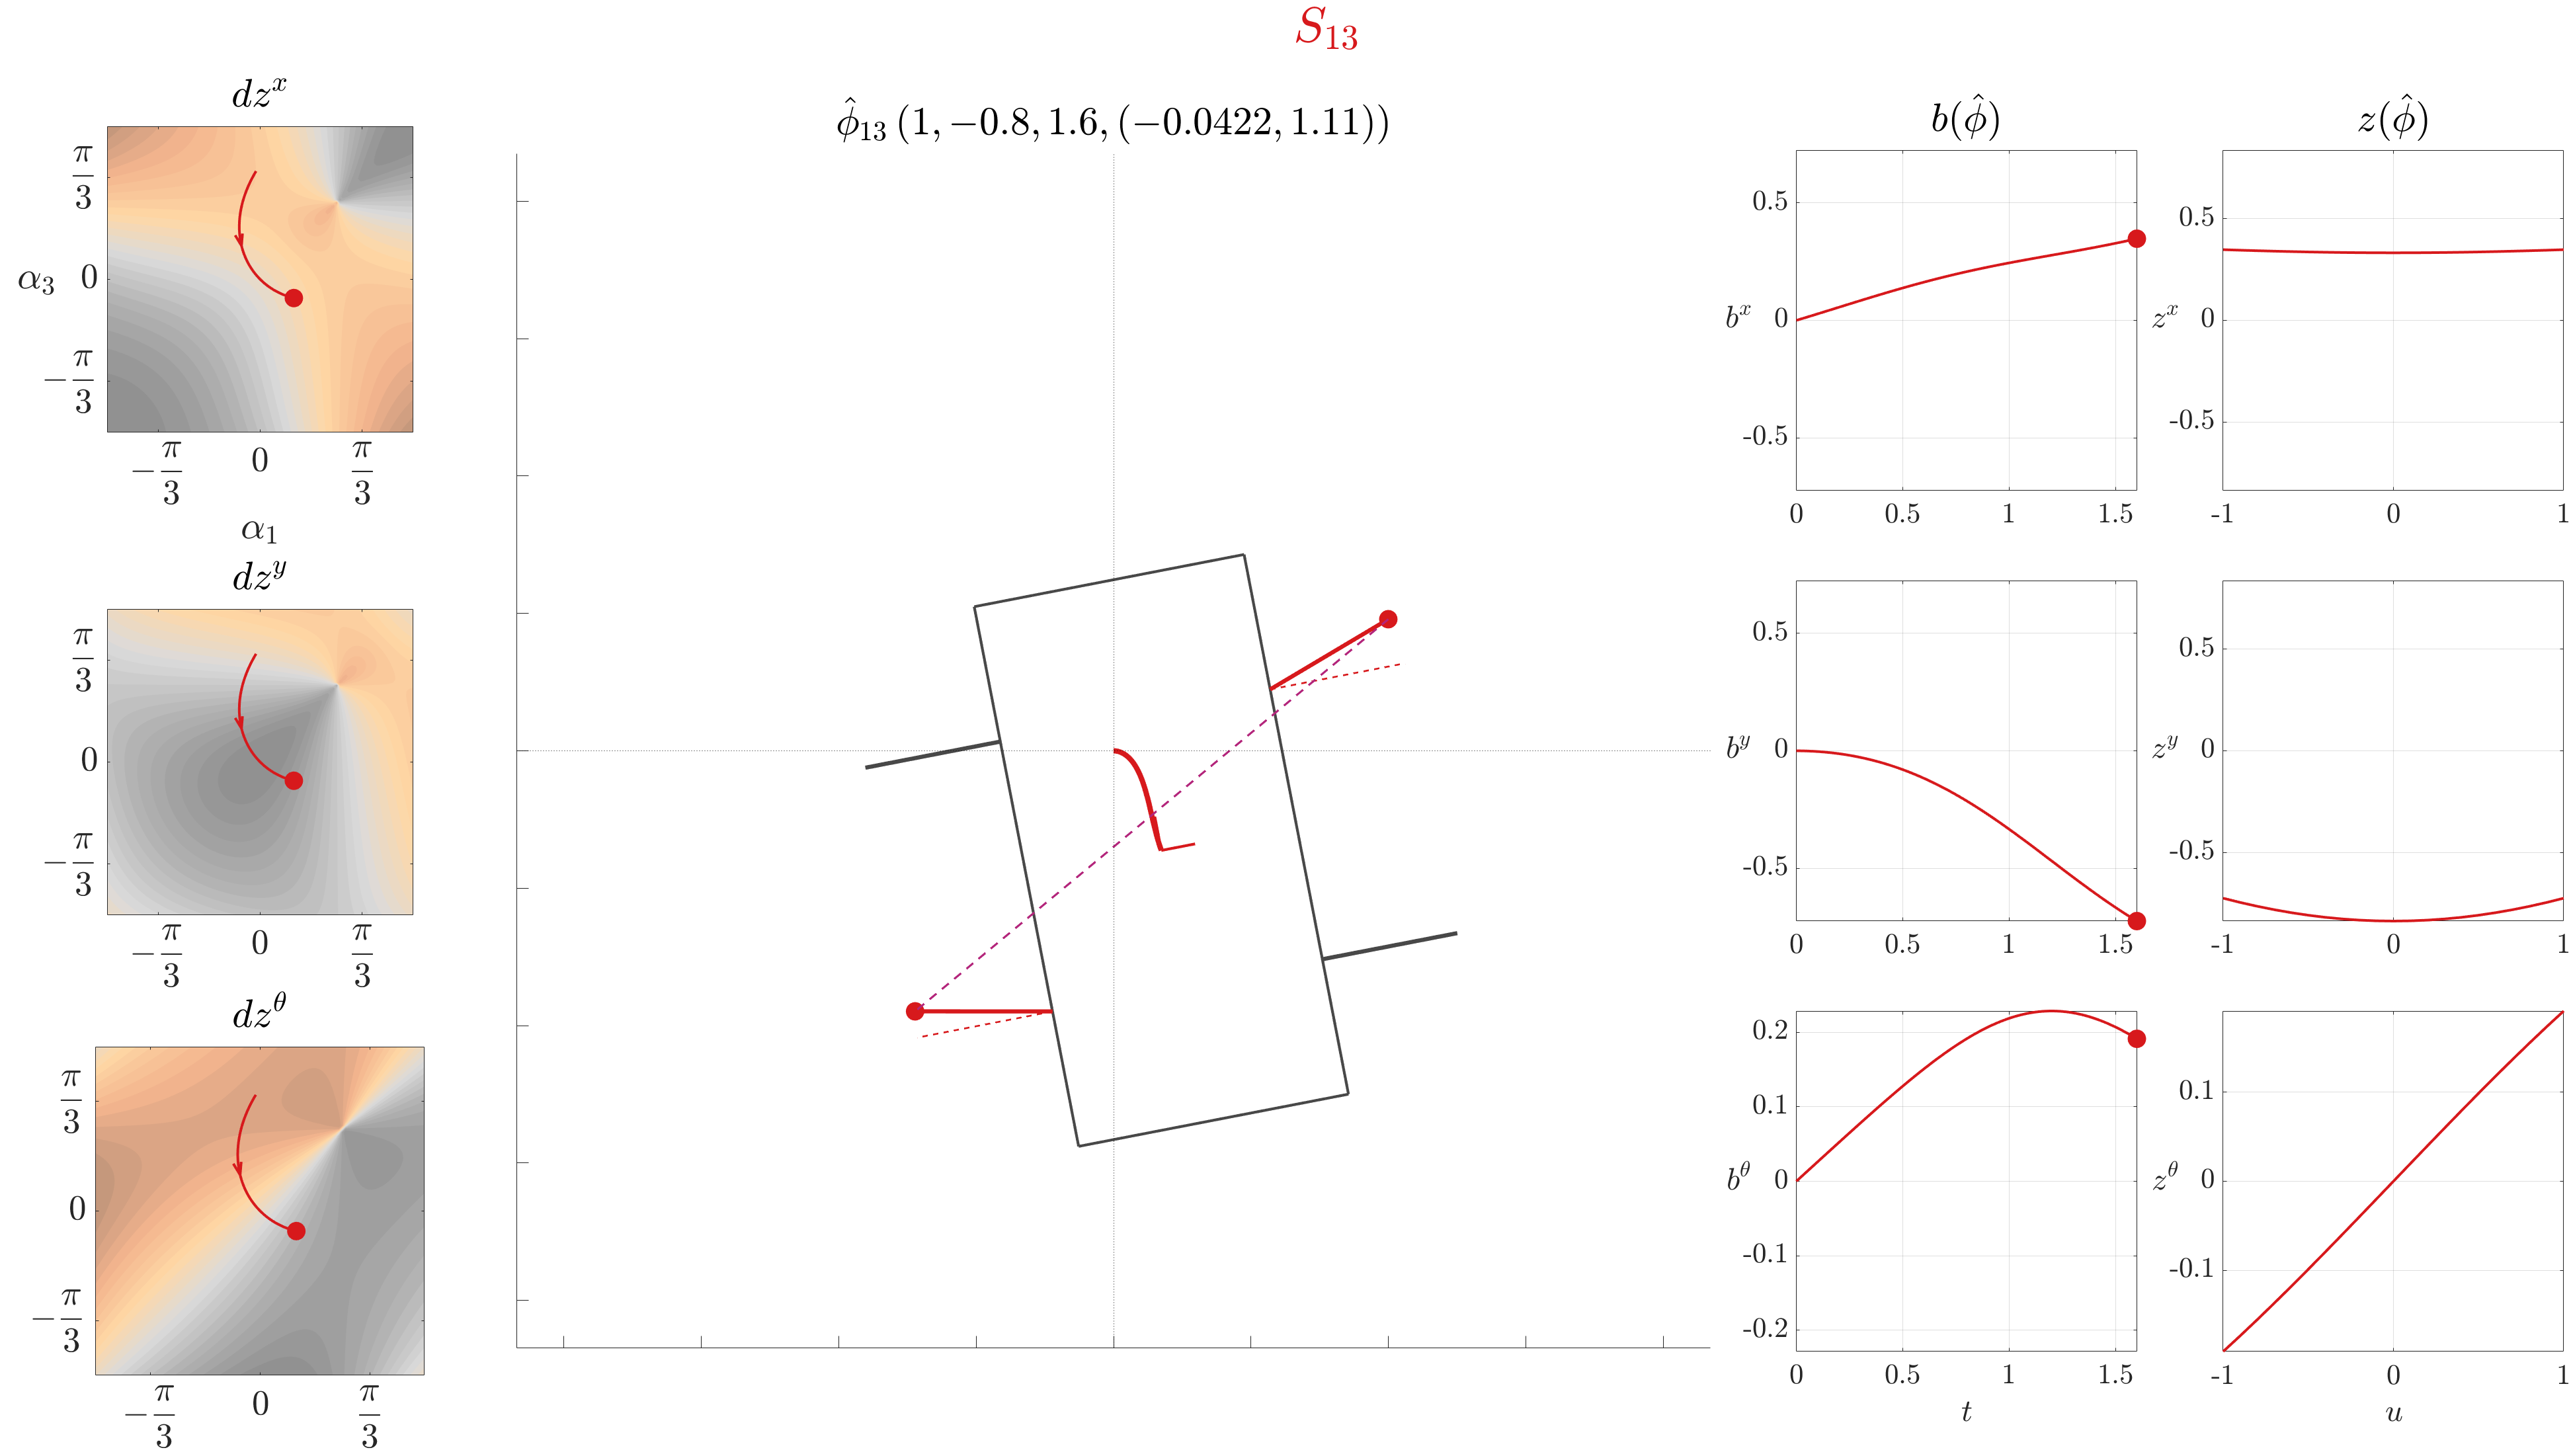

si = 5; % S13 % contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = { p_info{si}, p_kin{si}, kinfunc{si} };
% qlevel2noslip_mp(S_data);
[dz, dpsi, ddpsi, A, Adot, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
%%%%%%%%%%%%%%%%%%%%%%%%%
% conditions: "scale" or "slide"... 
% "scale" just scales the forward or backward path (increases translation), 
% "slide" slides the point of interest forward or backward (helps generate rotation)
% EVERYTHING IS IN THE CONTEXT OF TROT GAIT
% u_mode = "scale"; S_data{1}.mode = u_mode; % for "trial" and "trans"
u_mode = "slide"; S_data{1}.mode = u_mode; % for "steer" and "slide"; % add it to plot information
%%%%%%%%%%%%%%%%%%%%%%%%%
ptf = zeros(1, 2);
%%%%%%%%%%%%%%%%%%%%%%%%%
% t = [1.2, 1.2]; % trial
t = [0.8, 0.8]; % trans & steer
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum;
%%%%%%%%%%%%%%%%%%%%%%%%%
% dirn = -1; % for trial, trans, & steer
dirn = +1; % for steer_lat
%%%%%%%%%%%%%%%%%%%%%%%%%
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' ); c(c > 1) = 1;
path13 = Path2( ank, a, l, dz, dpsi, ddpsi, A, Adot, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
switch u_mode
    case "scale"
        Path2.compute_trajectory( path13, symstr, dnum );
    case "slide"
        slide_mul = [1.5, 1.5]; % amount you cal slide by in [back, forw]
        Path2.compute_slide_trajectory( path13, symstr, dnum, slide_mul );
end
path = path13;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% S_data{1}.skp_path = [1 20];  % for "trial" and "trans"
S_data{1}.skp_path = [1 21]; % for "slide" / any "steer" use this
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qlevel2noslip_mp(S_data);

% S13_Gen_trial = S_data; 
% S13_Gen_trans = S_data; 
% S13_Gen_steer = S_data;
S13_Gen_steer_lat = S_data;
if exist('Data\Gen_S13_data.mat', 'file')
    % save('Data\Gen_S13_data.mat', 'S13_Gen_trial', '-append');
    % save('Data\Gen_S13_data.mat', 'S13_Gen_trans', '-append');
    % save('Data\Gen_S13_data.mat', 'S13_Gen_steer', '-append');
    save('Data\Gen_S13_data.mat', 'S13_Gen_steer_lat', '-append');
else
    % save('Data\Gen_S13_data.mat', 'S13_Gen_trial');
    % save('Data\Gen_S13_data.mat', 'S13_Gen_trans');
    % save('Data\Gen_S13_data.mat', 'S13_Gen_steer');
    save('Data\Gen_S13_data.mat', 'S13_Gen_steer_lat');
end
clear S_data;

addpath 'Data'\ 'Utility Functions'\;
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');

### Translational sub-gait design in $S_{24}$

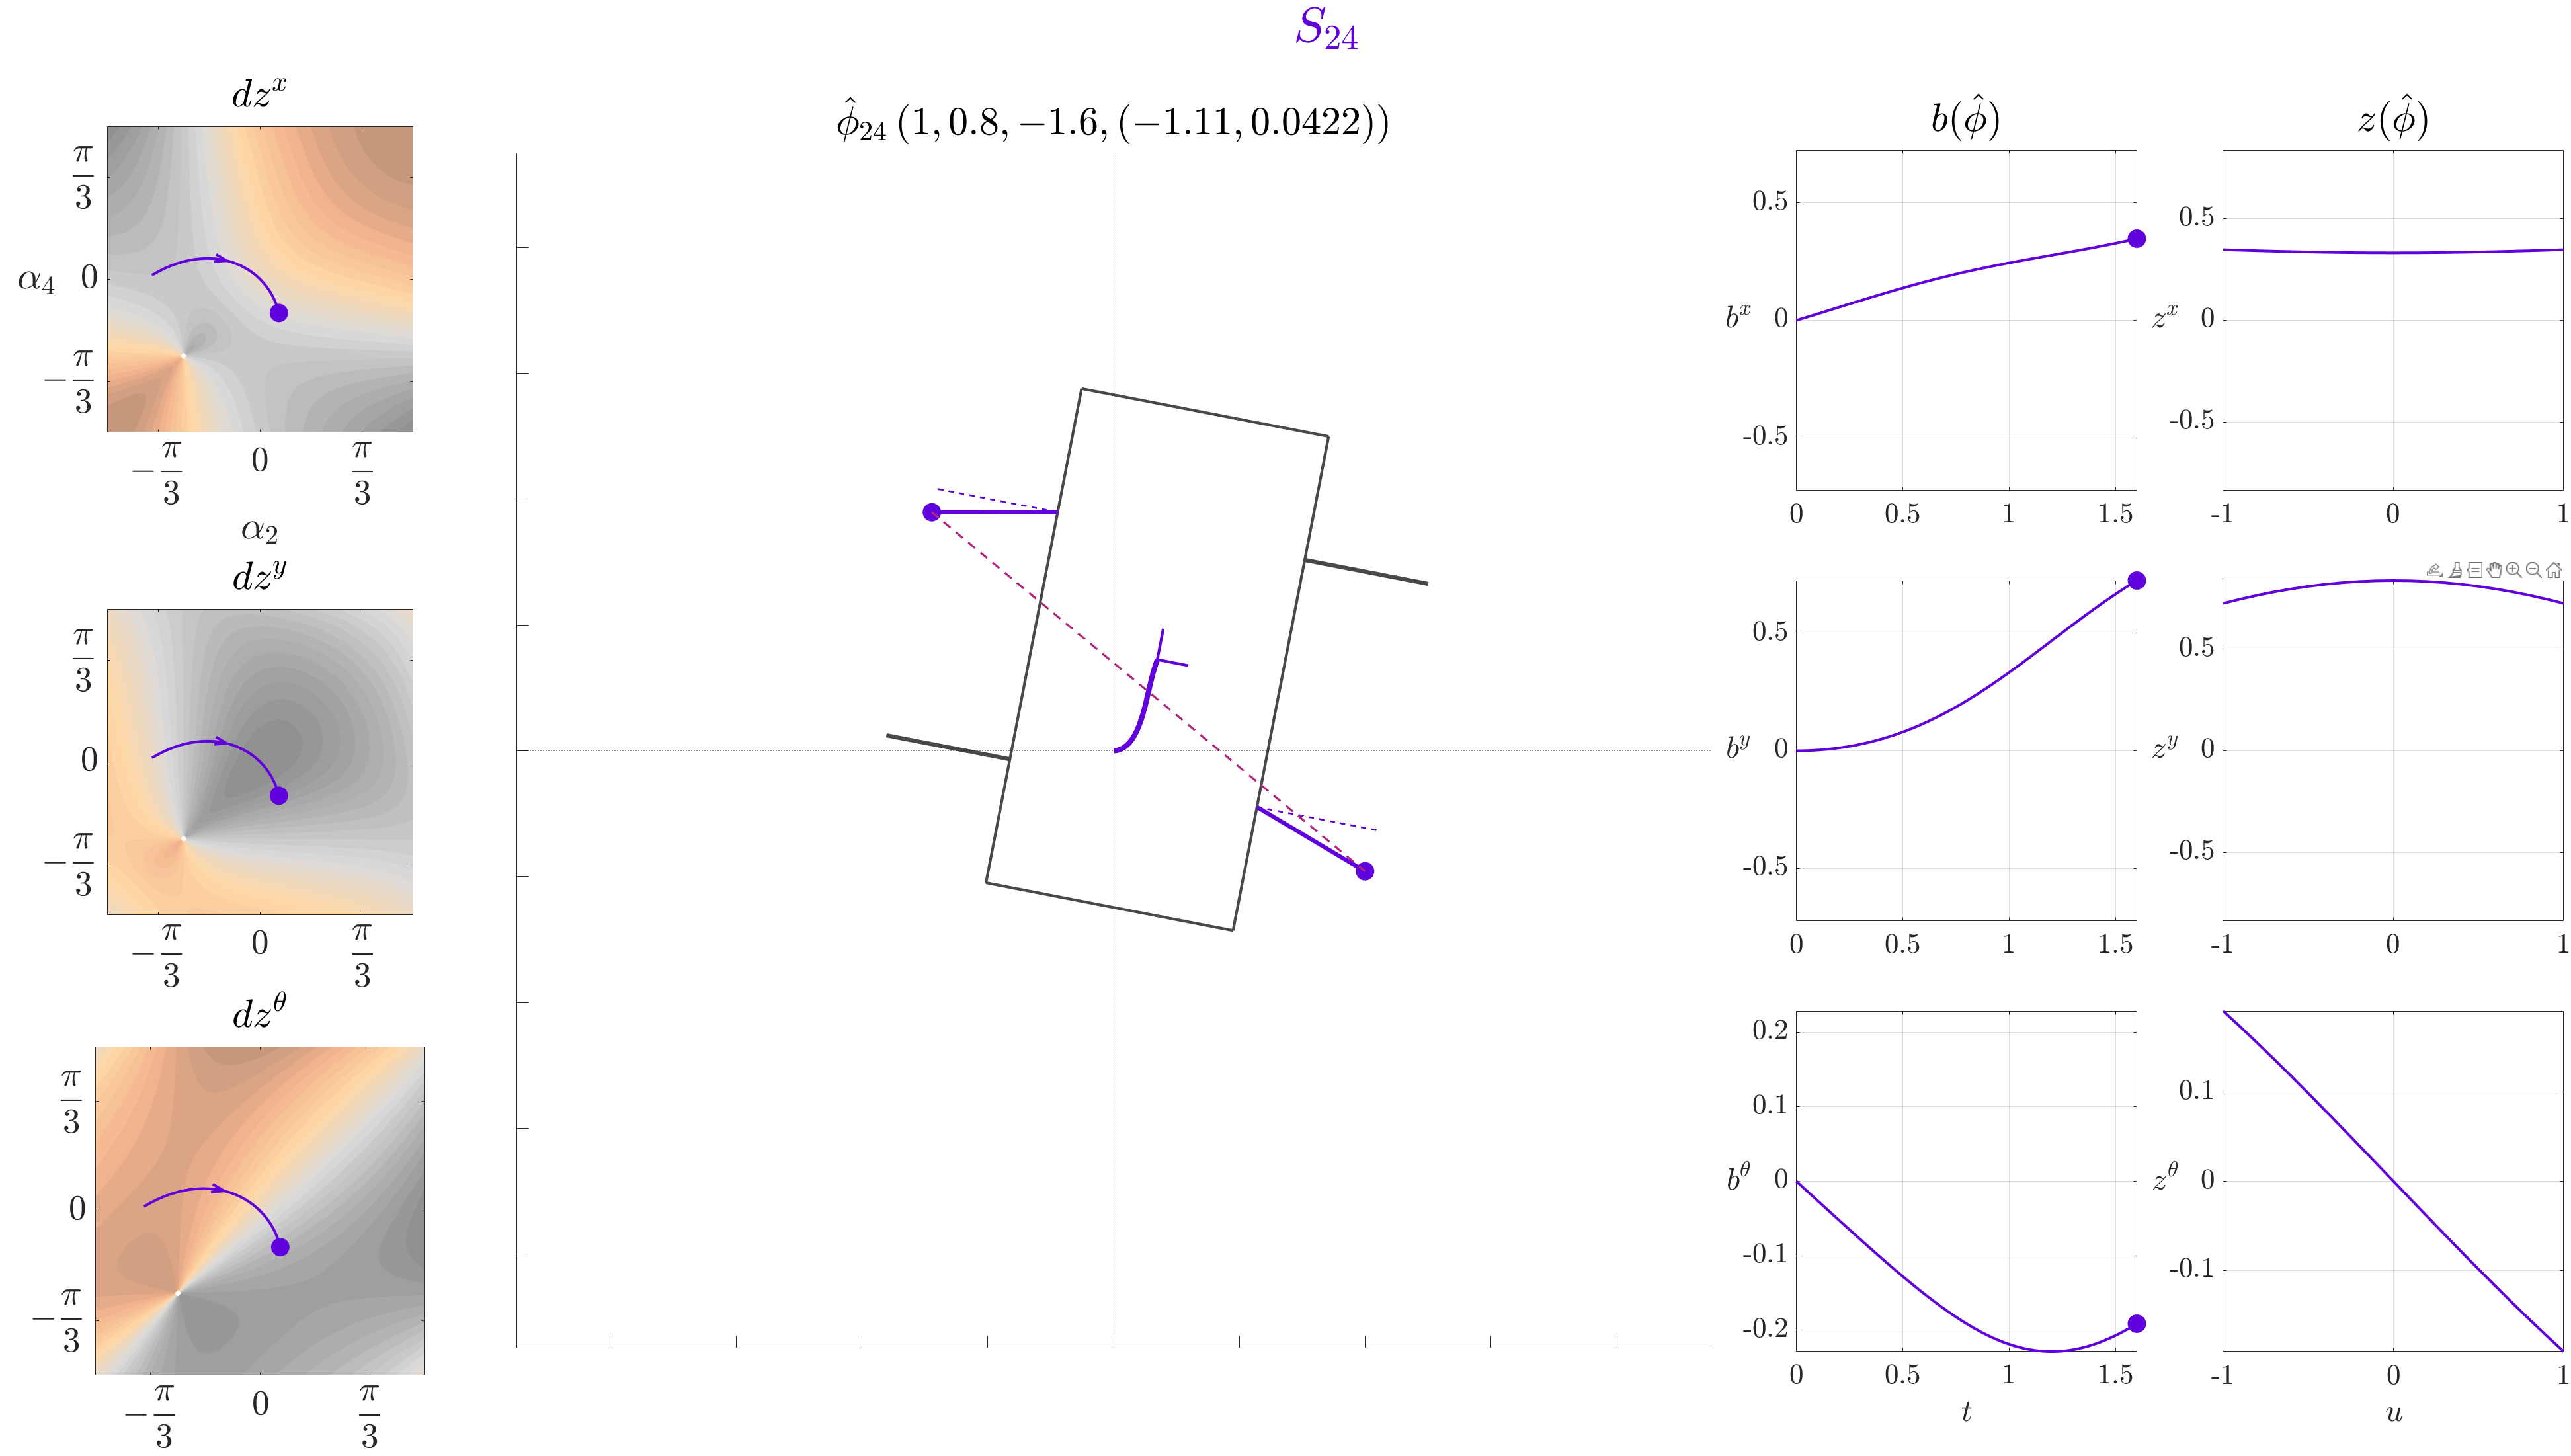

% contact submanifold ordering from left to right: [12, 23, 34, 41, 13, 24]
si = 6; % S24
p_info{si}.cLvl = 25;
p_info{si}.cfLvl = 25;
p_info{si}.lW_s = 2.0;
p_info{si}.colP = [0,0,0]/255;
p_info{si}.lS = ':';
S_data = {p_info{si}, p_kin{si}, kinfunc{si}};
% qlevel2noslip_mp(S_data);
[dz, dpsi, ddpsi, A, Adot, ksq, symstr] = returnVectorFields(S_data{3}, si);
ank = kinfunc{si}.ank;
a = kinfunc{si}.aa;
l = kinfunc{si}.ll;
%%%%%%%%%%%%%%%%%%%%%%%%
% u_mode = "scale"; S_data{1}.mode = u_mode;
u_mode = "slide"; S_data{1}.mode = u_mode;
%%%%%%%%%%%%%%%%%%%%%%%%%
ptf = zeros(1, 2);
%%%%%%%%%%%%%%%%%%%%%%%%%
% t = [1.2, 1.2]; % trial
t = [0.8, 0.8]; % trans & steer
dc = 0.2;
dnum = 201; S_data{3}.dnum = dnum; 
%%%%%%%%%%%%%%%%%%%%%%%%%
dirn = -1; % for "trial", "trans", and "steer"
%%%%%%%%%%%%%%%%%%%%%%%%%
c = interp1( linspace(p_info{si}.ksq_lim(1), p_info{si}.ksq_lim(2), size(p_info{si}.jetDark, 1)), p_info{si}.jetDark, ksq(a, l, ptf(1), ptf(2)), 'spline' ); c(c > 1) = 1;
path24 = Path2( ank, a, l, dz, dpsi, ddpsi, A, Adot, ptf, t, dc, [c; [37, 37, 37]/255], si, dirn );
switch u_mode
    case "scale"
        Path2.compute_trajectory( path24, symstr, dnum );
    case "slide"
        slide_mul = [1.5, 1.5];
        Path2.compute_slide_trajectory( path24, symstr, dnum, slide_mul );
end
path = path24;
S_data{4} = pltkin;
S_data{5} = path;
S_data{1}.fA = 0.70;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S_data{6} = false; % true-- video, false-- no video
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% S_data{1}.skp_path = [1 20]; % scale-- trans/trial!!
S_data{1}.skp_path = [1 21]; % [1, 21] % slide-- steer/steer_lat!!
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
qlevel2noslip_mp(S_data);

% S24_Gen_trial = S_data;
% S24_Gen_trans = S_data;
S24_Gen_steer = S_data; 
if exist('Data\Gen_S24_data.mat', 'file')
    % save('Data\Gen_S24_data.mat', 'S24_Gen_trial', '-append');
    % save('Data\Gen_S24_data.mat', 'S24_Gen_trans', '-append');
    save('Data\Gen_S24_data.mat', 'S24_Gen_steer', '-append');
else
    % save('Data\Gen_S24_data.mat', 'S24_Gen_trial');
    % save('Data\Gen_S24_data.mat', 'S24_Gen_trans');
    save('Data\Gen_S24_data.mat', 'S24_Gen_steer');
end
clear S_data;

addpath 'Data'\ 'Utility Functions'\
load('case_1_kinematics'); load('case_1_kinematics_motionplan.mat');
% load('Data\Gen_S13_data.mat', 'S13_Gen_trial'); % load this and one below for trial
% load('Data\Gen_S24_data.mat', 'S24_Gen_trial');
load('Data\Gen_S13_data.mat', 'S13_Gen_trans'); % load this and one below for trans-- 1 to 2
load('Data\Gen_S24_data.mat', 'S24_Gen_trans');
% load('Data\Gen_S13_data.mat', 'S13_Gen_steer'); % for streer 1 to 4
% load('Data\Gen_S24_data.mat', 'S24_Gen_steer');
% load('Data\Gen_S13_data.mat', 'S13_Gen_steer_lat'); % for steer 5 to 8
% load('Data\Gen_S24_data.mat', 'S24_Gen_steer');

### 
$$S_{13} \leftrightarrow S_{24}$$


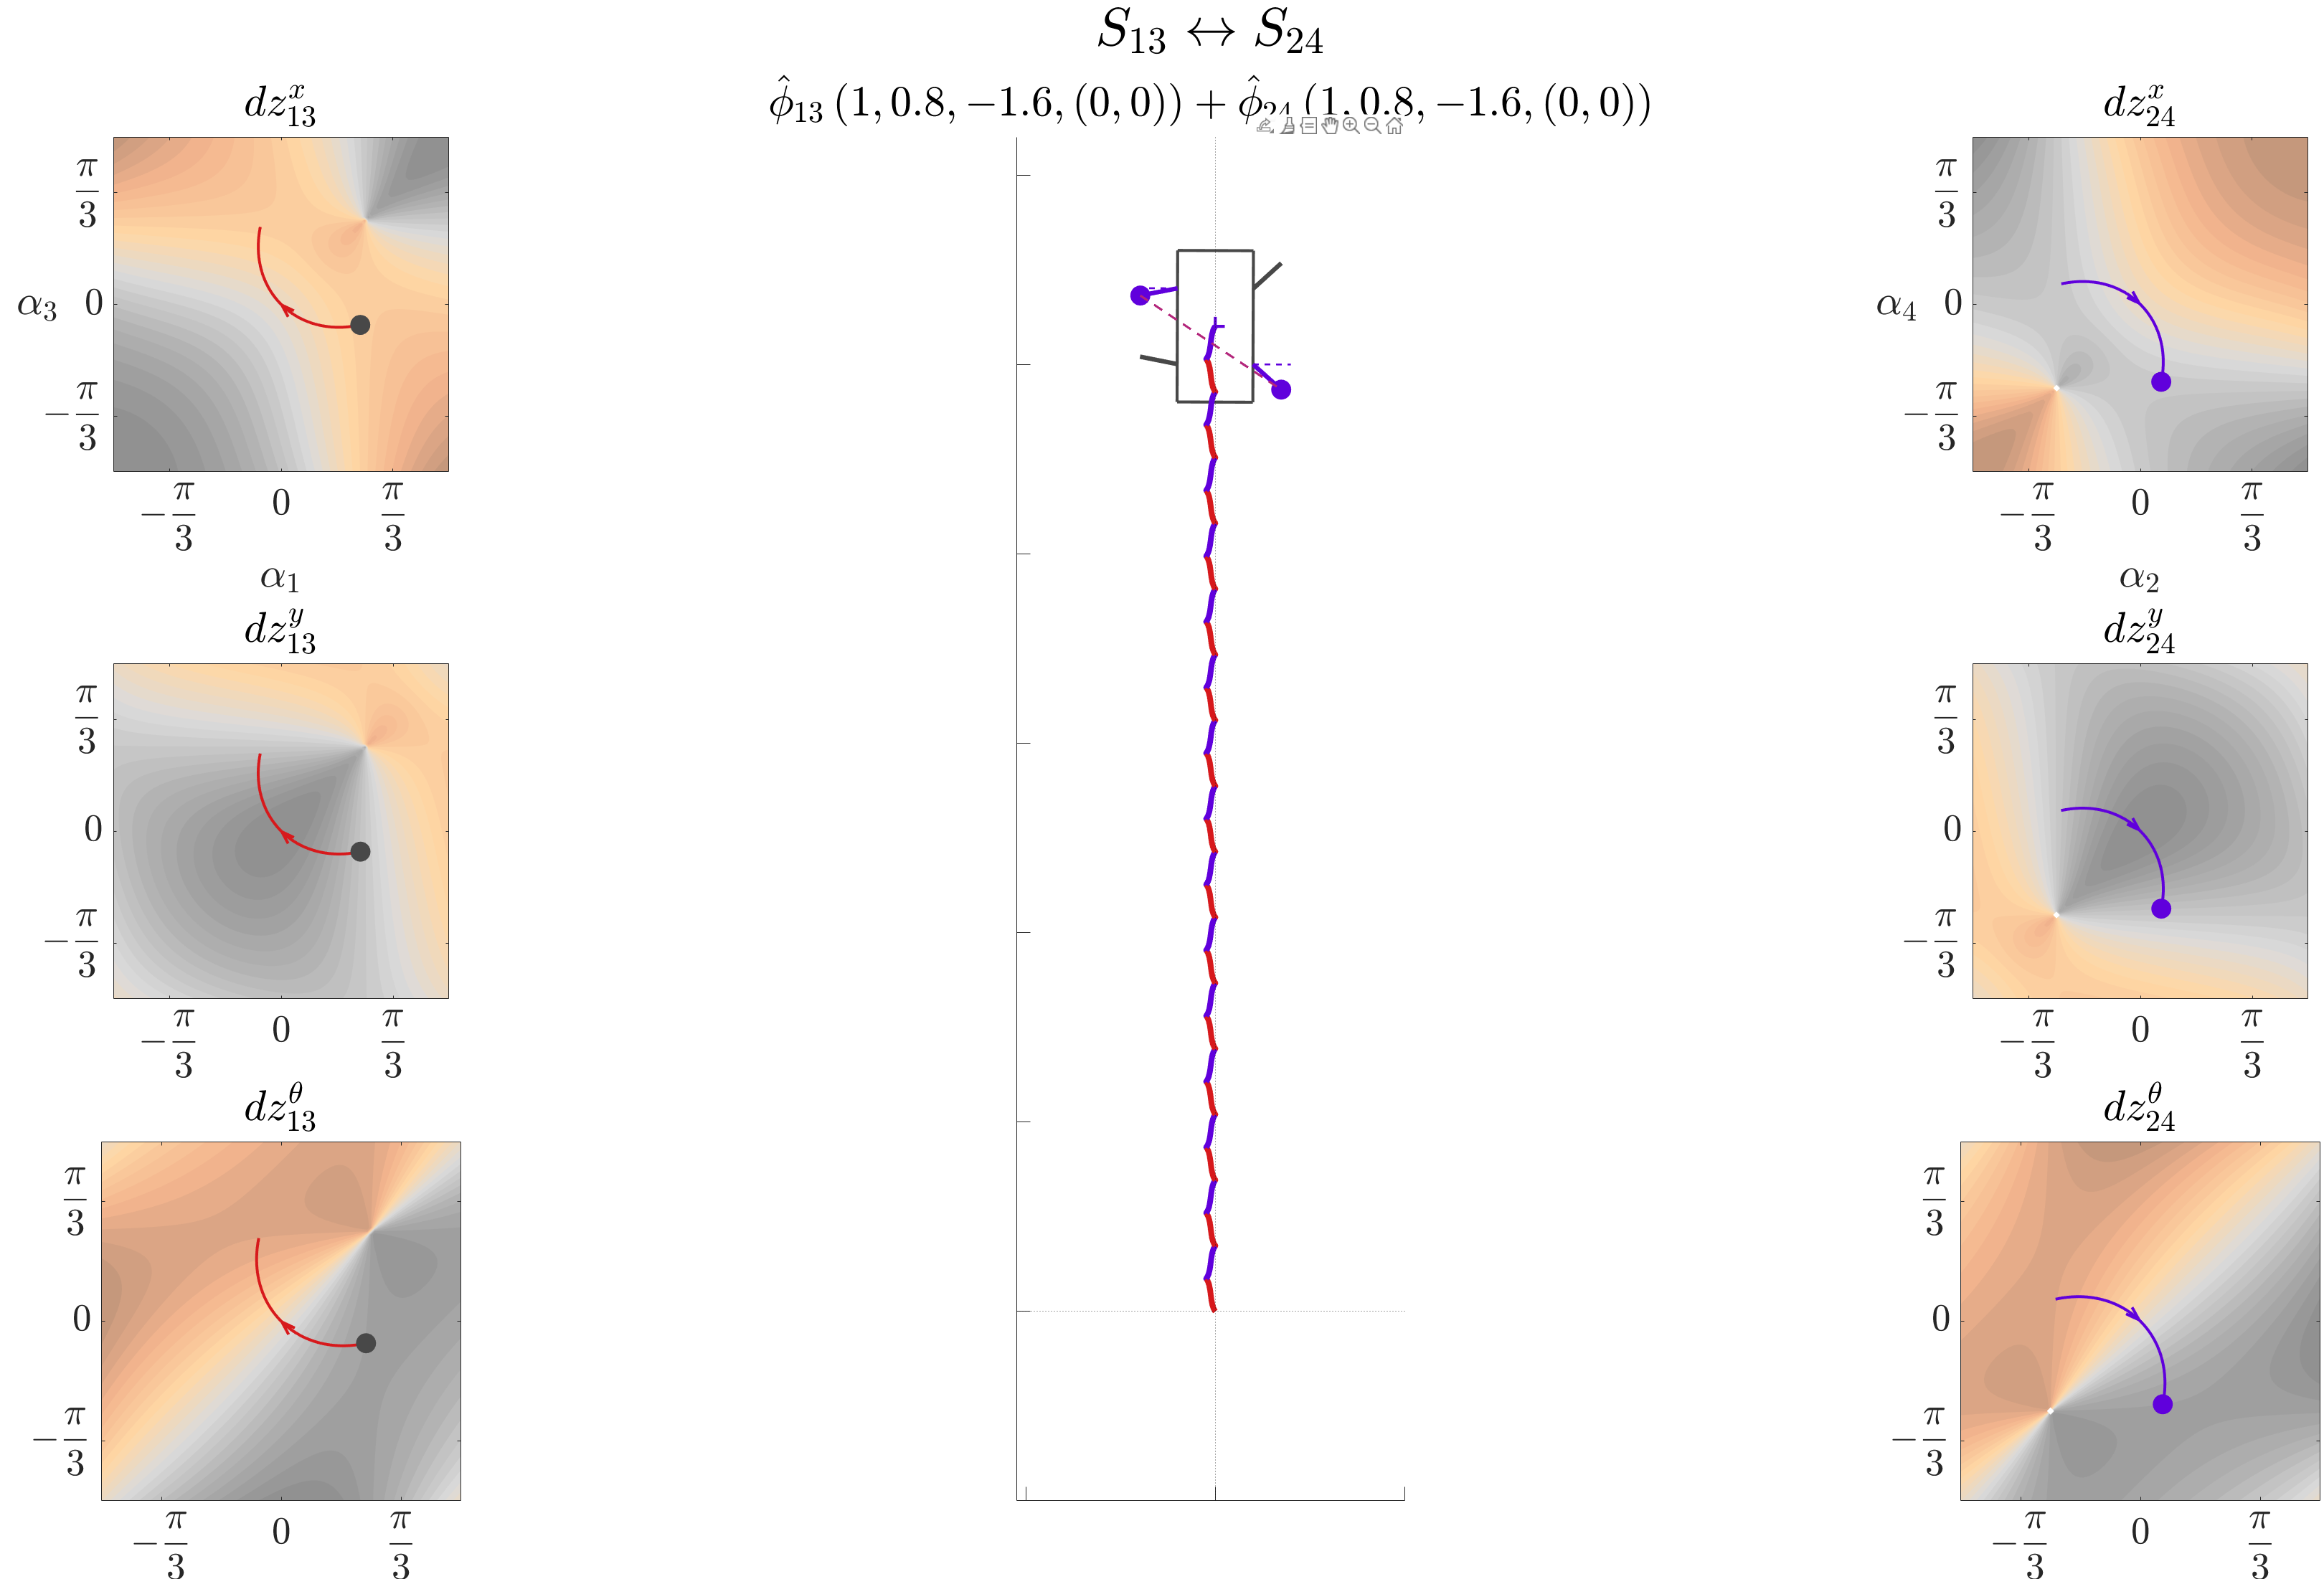

dataij = [];
dataij.vidF = false; % true % false
% dataij.u = [+100, +100]/100; dataij.gaitC_num = 15; % trial                  % inputs can only be multiples of 10!!!!
dataij.u = [+100, +100]/100; dataij.gaitC_num = 15; % trans_1
% dataij.u = [-100, +100]/100; dataij.gaitC_num = 15; % trans_2
% dataij.u = [+100, -100]/100; dataij.gaitC_num = 15; % steer_1
% dataij.u = [-100, +100]/100; dataij.gaitC_num = 15; % steer_2
% dataij.u = [+50, -50]/100; dataij.gaitC_num = 15; % steer_3
% dataij.u = [-50, +50]/100; dataij.gaitC_num = 15; % steer_4
% dataij.u = [+100, -100]/100; dataij.gaitC_num = 15; % steer_5
% dataij.u = [-100, +100]/100; dataij.gaitC_num = 15; % steer_6
% dataij.u = [+50, -50]/100; dataij.gaitC_num = 15; % steer_7
% dataij.u = [-50, +50]/100; dataij.gaitC_num = 15; % steer_8
% S13_Gen_trial{1}.fA = 0.7;
% S24_Gen_trial{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S13_Gen_trial, S24_Gen_trial, dataij);
% plotnetdispofnoslip2bgaits(S13_Gen_trial, S24_Gen_trial, dataij);
% plotNetPanelofNoslip2bgaits(S13_Gen_trial, S24_Gen_trial, dataij);
S13_Gen_trans{1}.fA = 0.7;
S24_Gen_trans{1}.fA = 0.7;
dataij = qlevel2noslip_mp(S13_Gen_trans, S24_Gen_trans, dataij);

ans =     0.7071    0.4243    0.1414


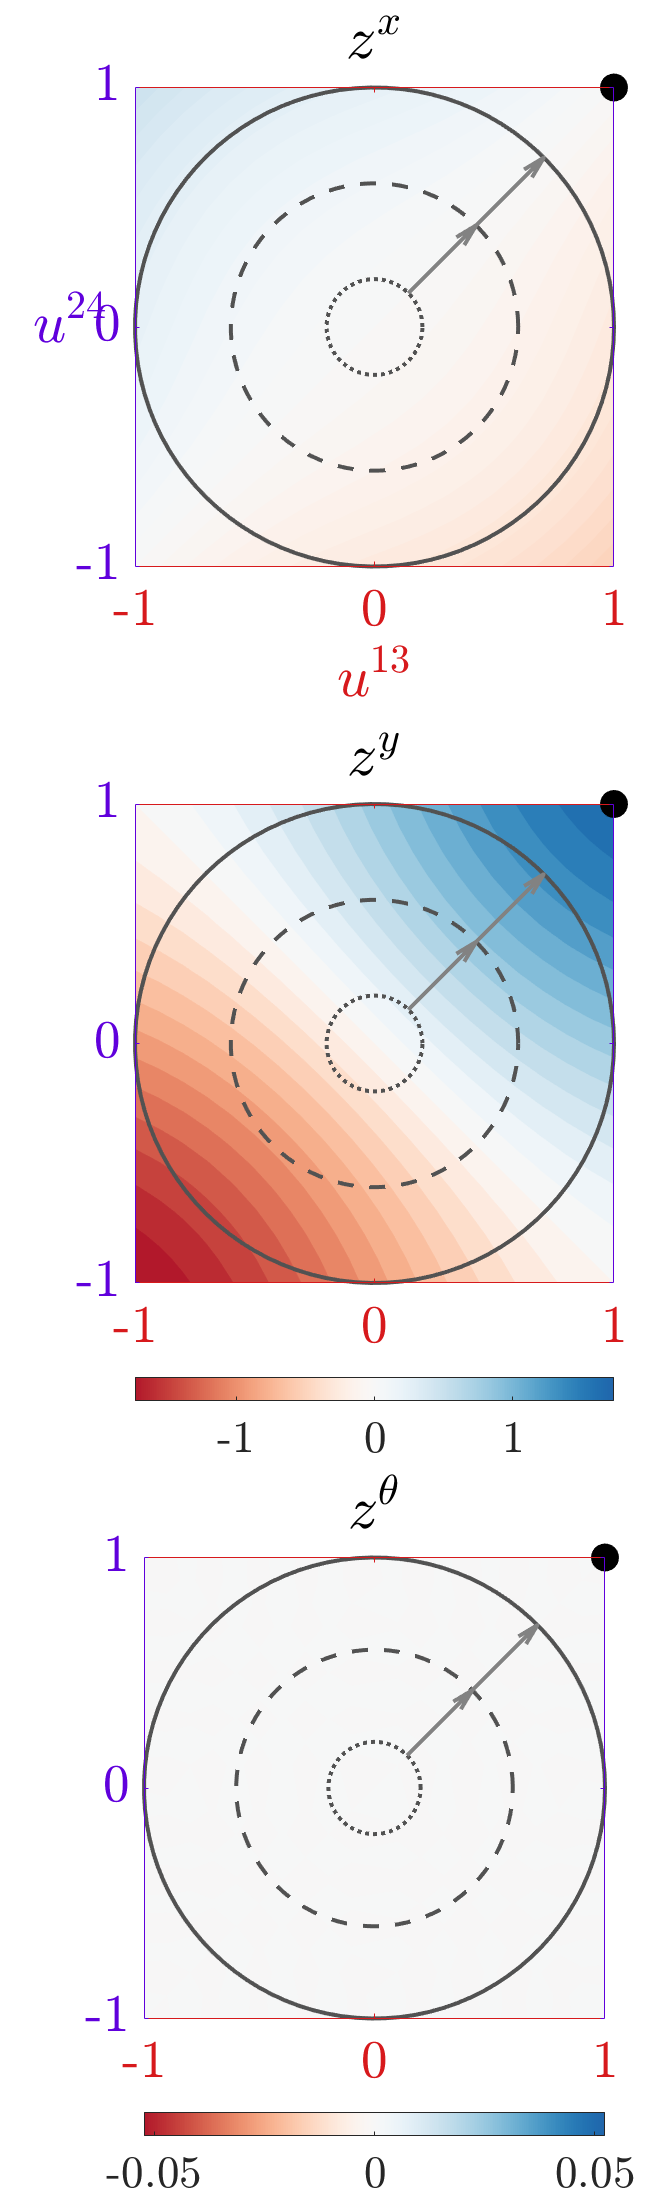

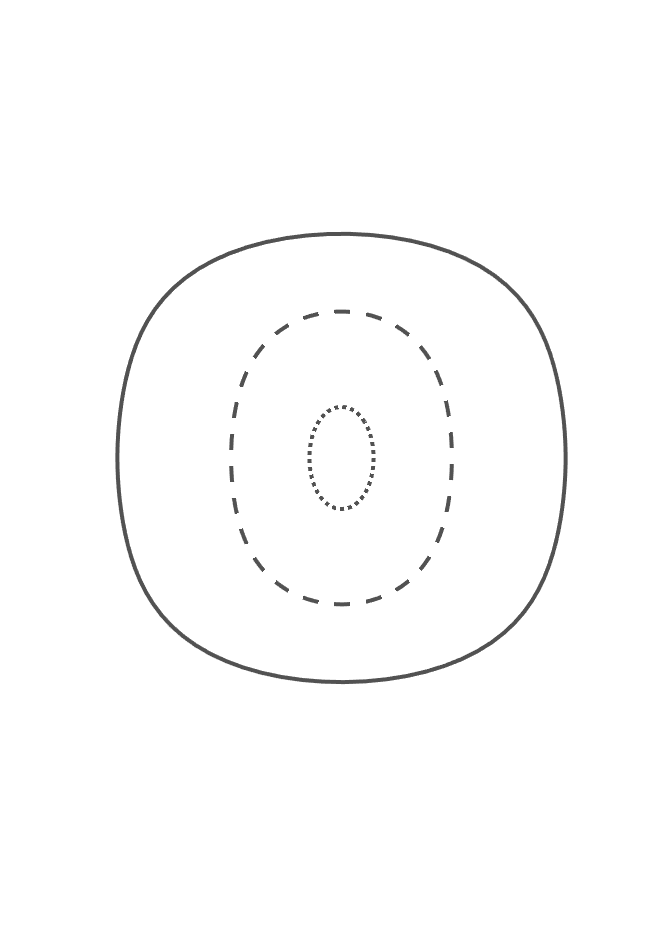

plotnetdispofnoslip2bgaits(S13_Gen_trans, S24_Gen_trans, dataij);

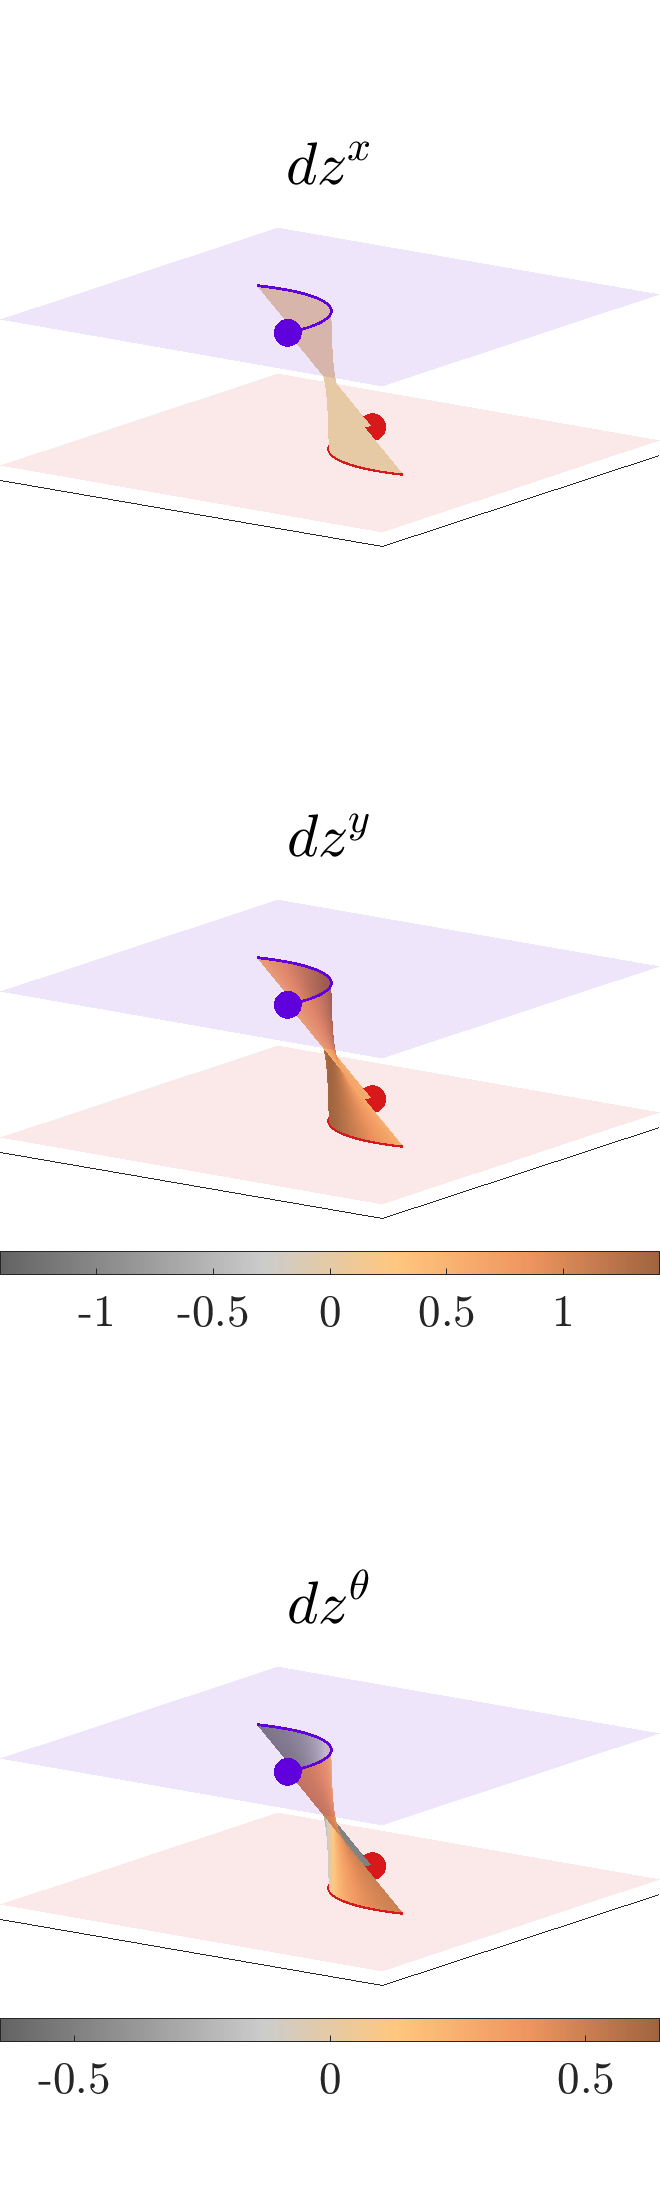

plotNetPanelofNoslip2bgaits(S13_Gen_trans, S24_Gen_trans, dataij);

% S13_Gen_steer{1}.fA = 0.7;
% S24_Gen_steer{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S13_Gen_steer, S24_Gen_steer, dataij);
% plotnetdispofnoslip2bgaits(S13_Gen_steer, S24_Gen_steer, dataij);
% plotNetPanelofNoslip2bgaits(S13_Gen_steer, S24_Gen_steer, dataij);
% S13_Gen_steer_lat{1}.fA = 0.7;
% S24_Gen_steer{1}.fA = 0.7;
% dataij = qlevel2noslip_mp(S13_Gen_steer_lat, S24_Gen_steer, dataij);
% plotnetdispofnoslip2bgaits(S13_Gen_steer_lat, S24_Gen_steer, dataij);
% plotNetPanelofNoslip2bgaits(S13_Gen_steer_lat, S24_Gen_steer, dataij);
% close all;
% % Gen_S13toS24_trial_data = dataij;
% % Gen_S13toS24_trans_1_data = dataij;
% % Gen_S13toS24_trans_2_data = dataij;
% % Gen_S13toS24_steer_1_data = dataij;
% % Gen_S13toS24_steer_2_data = dataij;
% % Gen_S13toS24_steer_3_data = dataij;
% % Gen_S13toS24_steer_4_data = dataij;
% % Gen_S13toS24_steer_5_data = dataij;
% % Gen_S13toS24_steer_6_data = dataij;
% % Gen_S13toS24_steer_7_data = dataij;
% % Gen_S13toS24_steer_8_data = dataij;
% if exist('Data\Gen_S13toS24.mat', 'file')
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_trial_data', '-append');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_trans_1_data', '-append');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_trans_2_data', '-append');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_1_data', '-append');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_2_data', '-append');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_3_data', '-append');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_4_data', '-append');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_5_data', '-append');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_6_data', '-append');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_7_data', '-append');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_8_data', '-append');
% else
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_trial_data');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_trans_1_data');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_trans_2_data');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_1_data');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_2_data');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_3_data');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_4_data');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_5_data');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_6_data');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_7_data');
%     % save('Data\Gen_S13toS24.mat', 'Gen_S13toS24_steer_8_data');
% end

addpath 'Data'\ 'Utility Functions'\;

### Stitching Trajectories together

The goal is take the gait structure generated earlier and then plot/animate the system for how many ever gait cycles we require.

load('Data\Gen_S13toS24.mat'); % load all the "quadlevel2noslip_mp" gaits
load('Data\Gen_S13_data.mat'); load('Data\Gen_S24_data.mat'); % load all individual "subgait" data as well

Roughly plotting the body trajectory helps us determine a composite gait before hand.

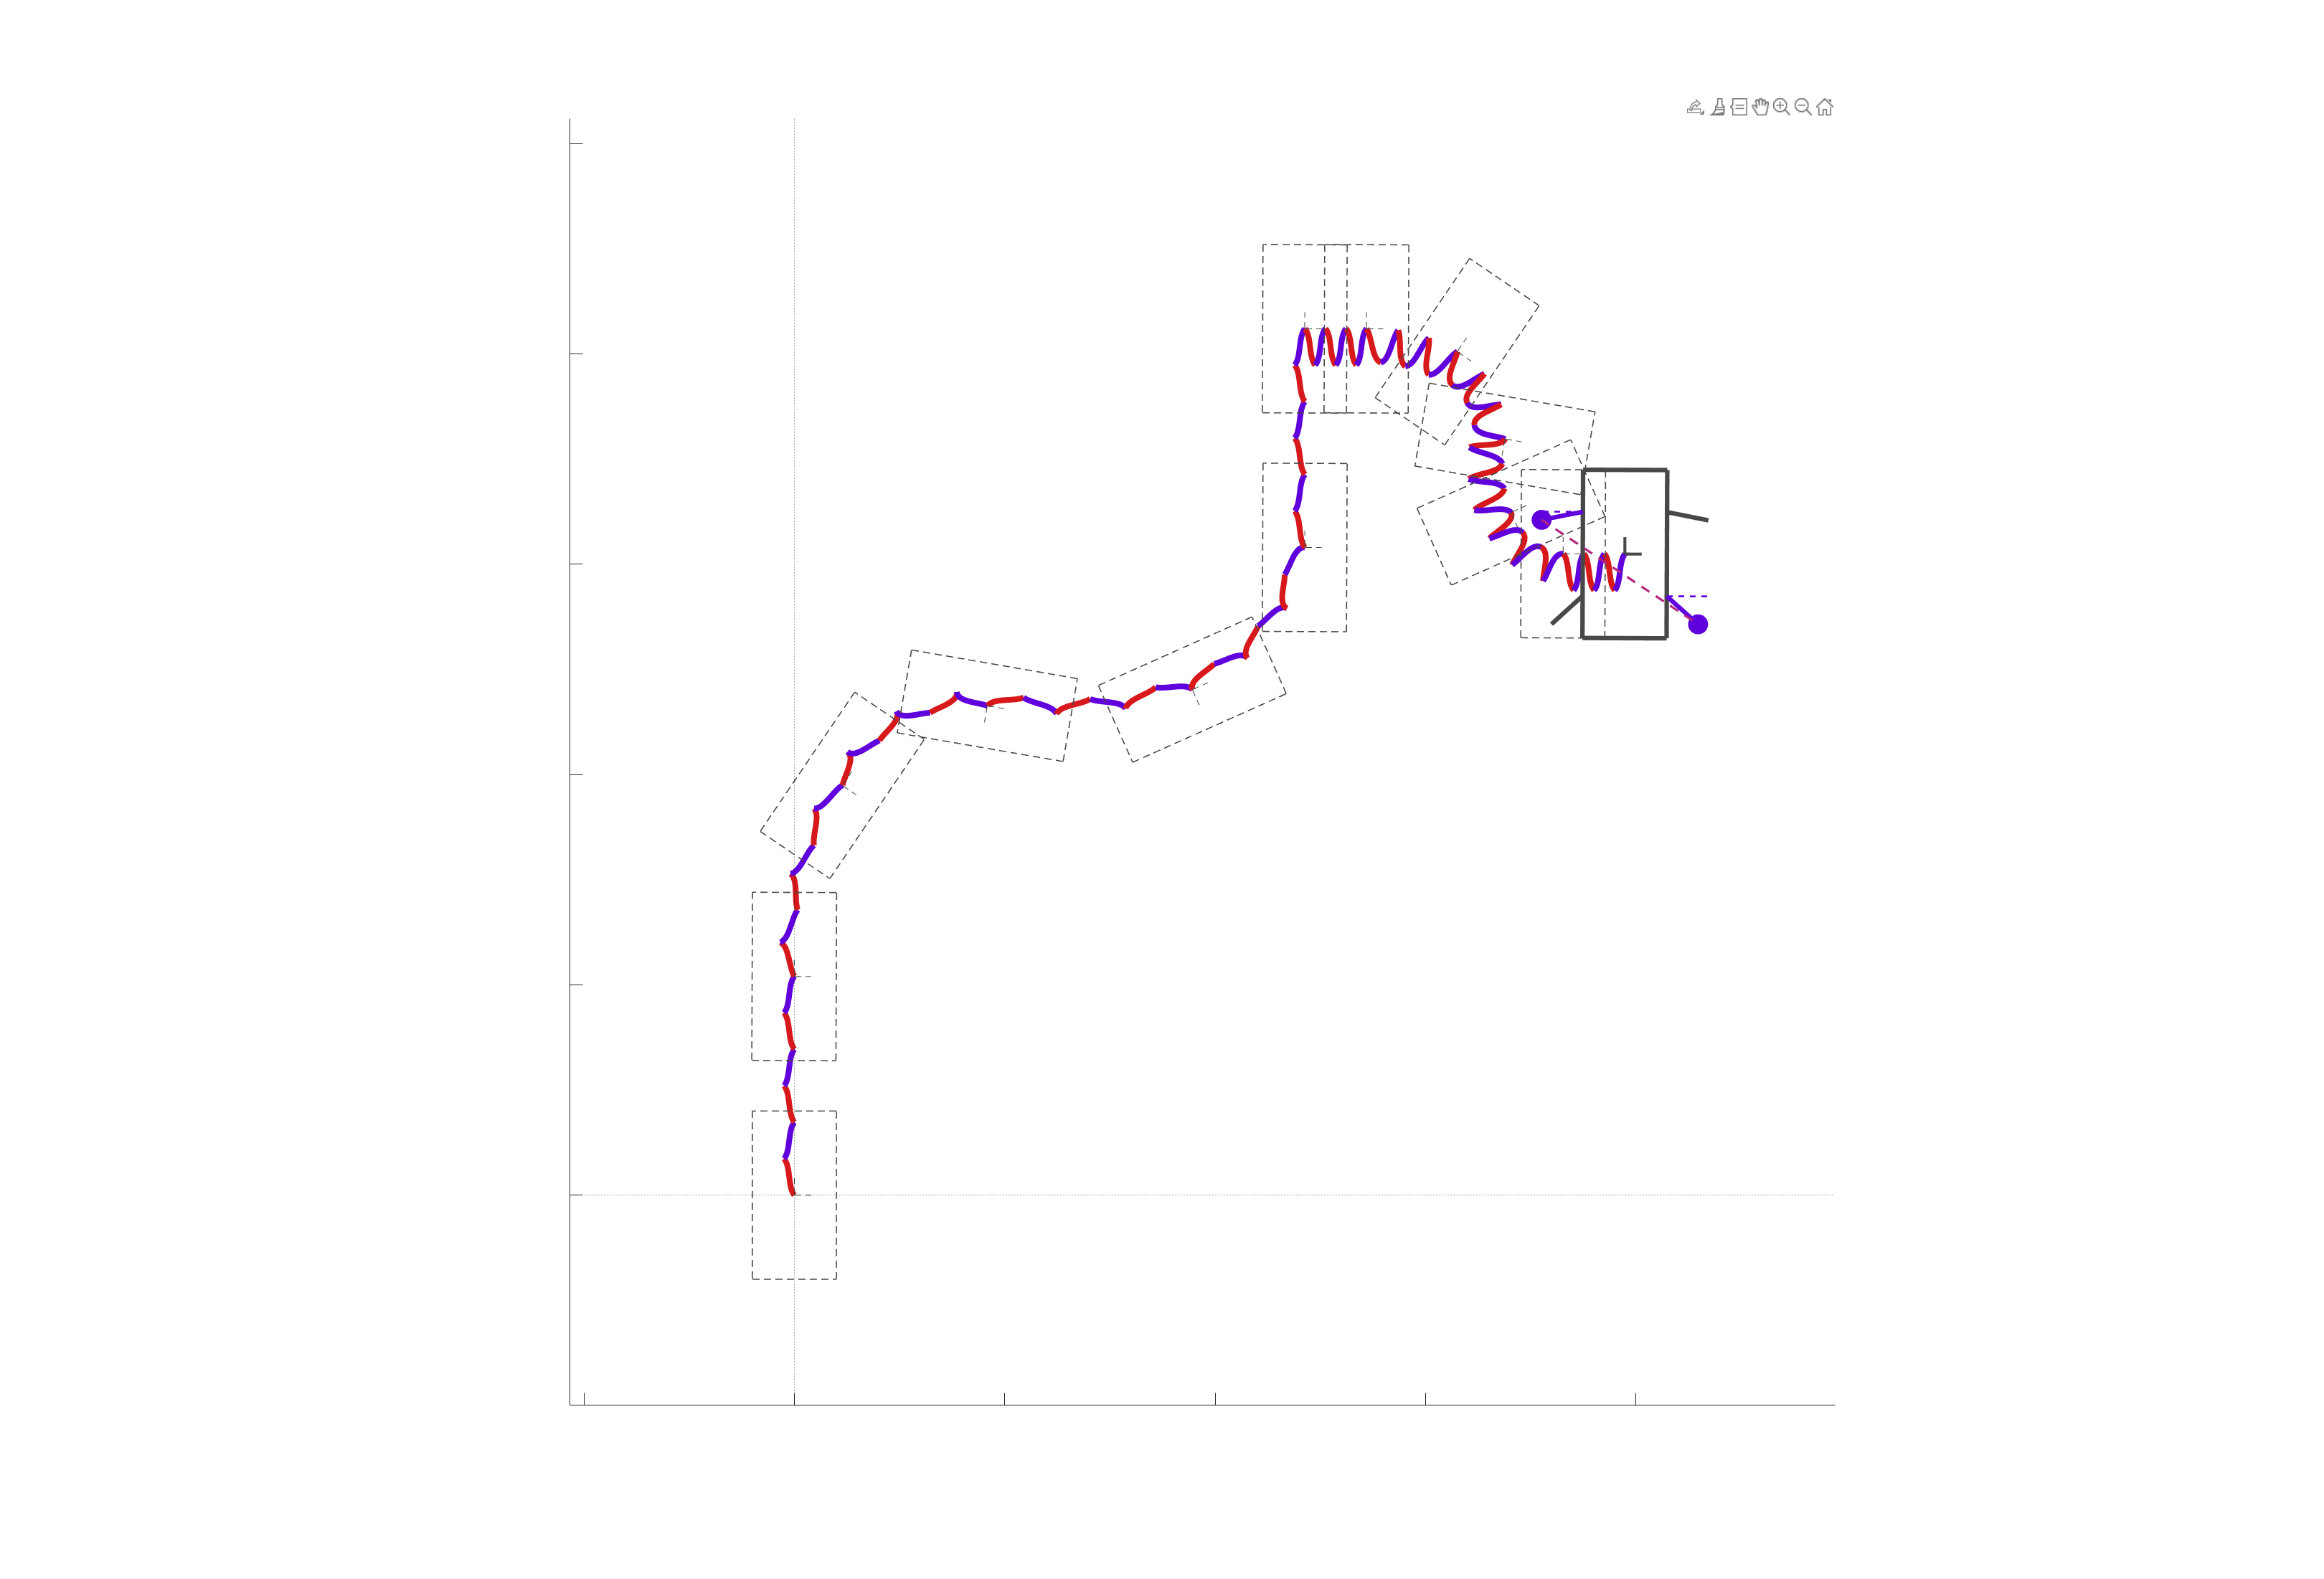

% compute the composite trajectory
[pltTraj, traj] = stitchQuadSE2gaits({    ...
    {{S13_Gen_trans, S24_Gen_trans}, {S13_Gen_steer, S24_Gen_steer}, {S13_Gen_trans, S24_Gen_trans}, {S13_Gen_steer_lat, S24_Gen_steer}, {S13_Gen_trans, S24_Gen_trans}},...
    {Gen_S13toS24_trans_1_data, Gen_S13toS24_steer_1_data, Gen_S13toS24_trans_2_data, Gen_S13toS24_steer_5_data, Gen_S13toS24_trans_2_data},...
    { {[1, 1]}, {[-0.5, 0.5], [-1, 1], [0.5, -0.5], [1, -1]}, {[1, 1], [-1, 1]}, {[-0.5, 0.5], [-1, 1], [0.5, -0.5], [1, -1]}, {[-1, 1]} },...
    { {3},      {3,           3,       3,           3},       {3,      3},       {3,           3,       3,           3},       {3} }    });
% Create the SE(2) snapshot
m = 2160; n = 1800; % fixed resolution
f = figure('units','pixels','position',[100 -200 m n],'Color','w');
set(gcf,'Visible','on'); % pop-out figure
hA = plot_SE2snapshot_QLvl2_Rigid_NoSlip( gca, pltTraj);

Let's now animate this trajectory!

% data ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
v = [];
save_addr = ''; % change to local address
save_name = 'composite_gait_1';

% get the points along the trajectory to animate
vid_time = 10; % in secs
v.fps = 60; % frames per second
% t = extractTimeVectorForCompGaitAnimation( traj.dnum, traj.gcVec, v.fps*vid_time, 'first' ); % slow down just the first gait cycle in each composite gait
t = round(linspace(1, traj.dnum, v.fps*vid_time));
if t(end) < traj.dnum
    t(end+1) = traj.dnum;
end
vidF = true;
v.Name = [save_addr save_name];
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% initialize video
if vidF
    video = VideoWriter([v.Name,'.mp4'],'MPEG-4');
    video.FrameRate = v.fps;
    video.Quality = 100;
    open(video);
end

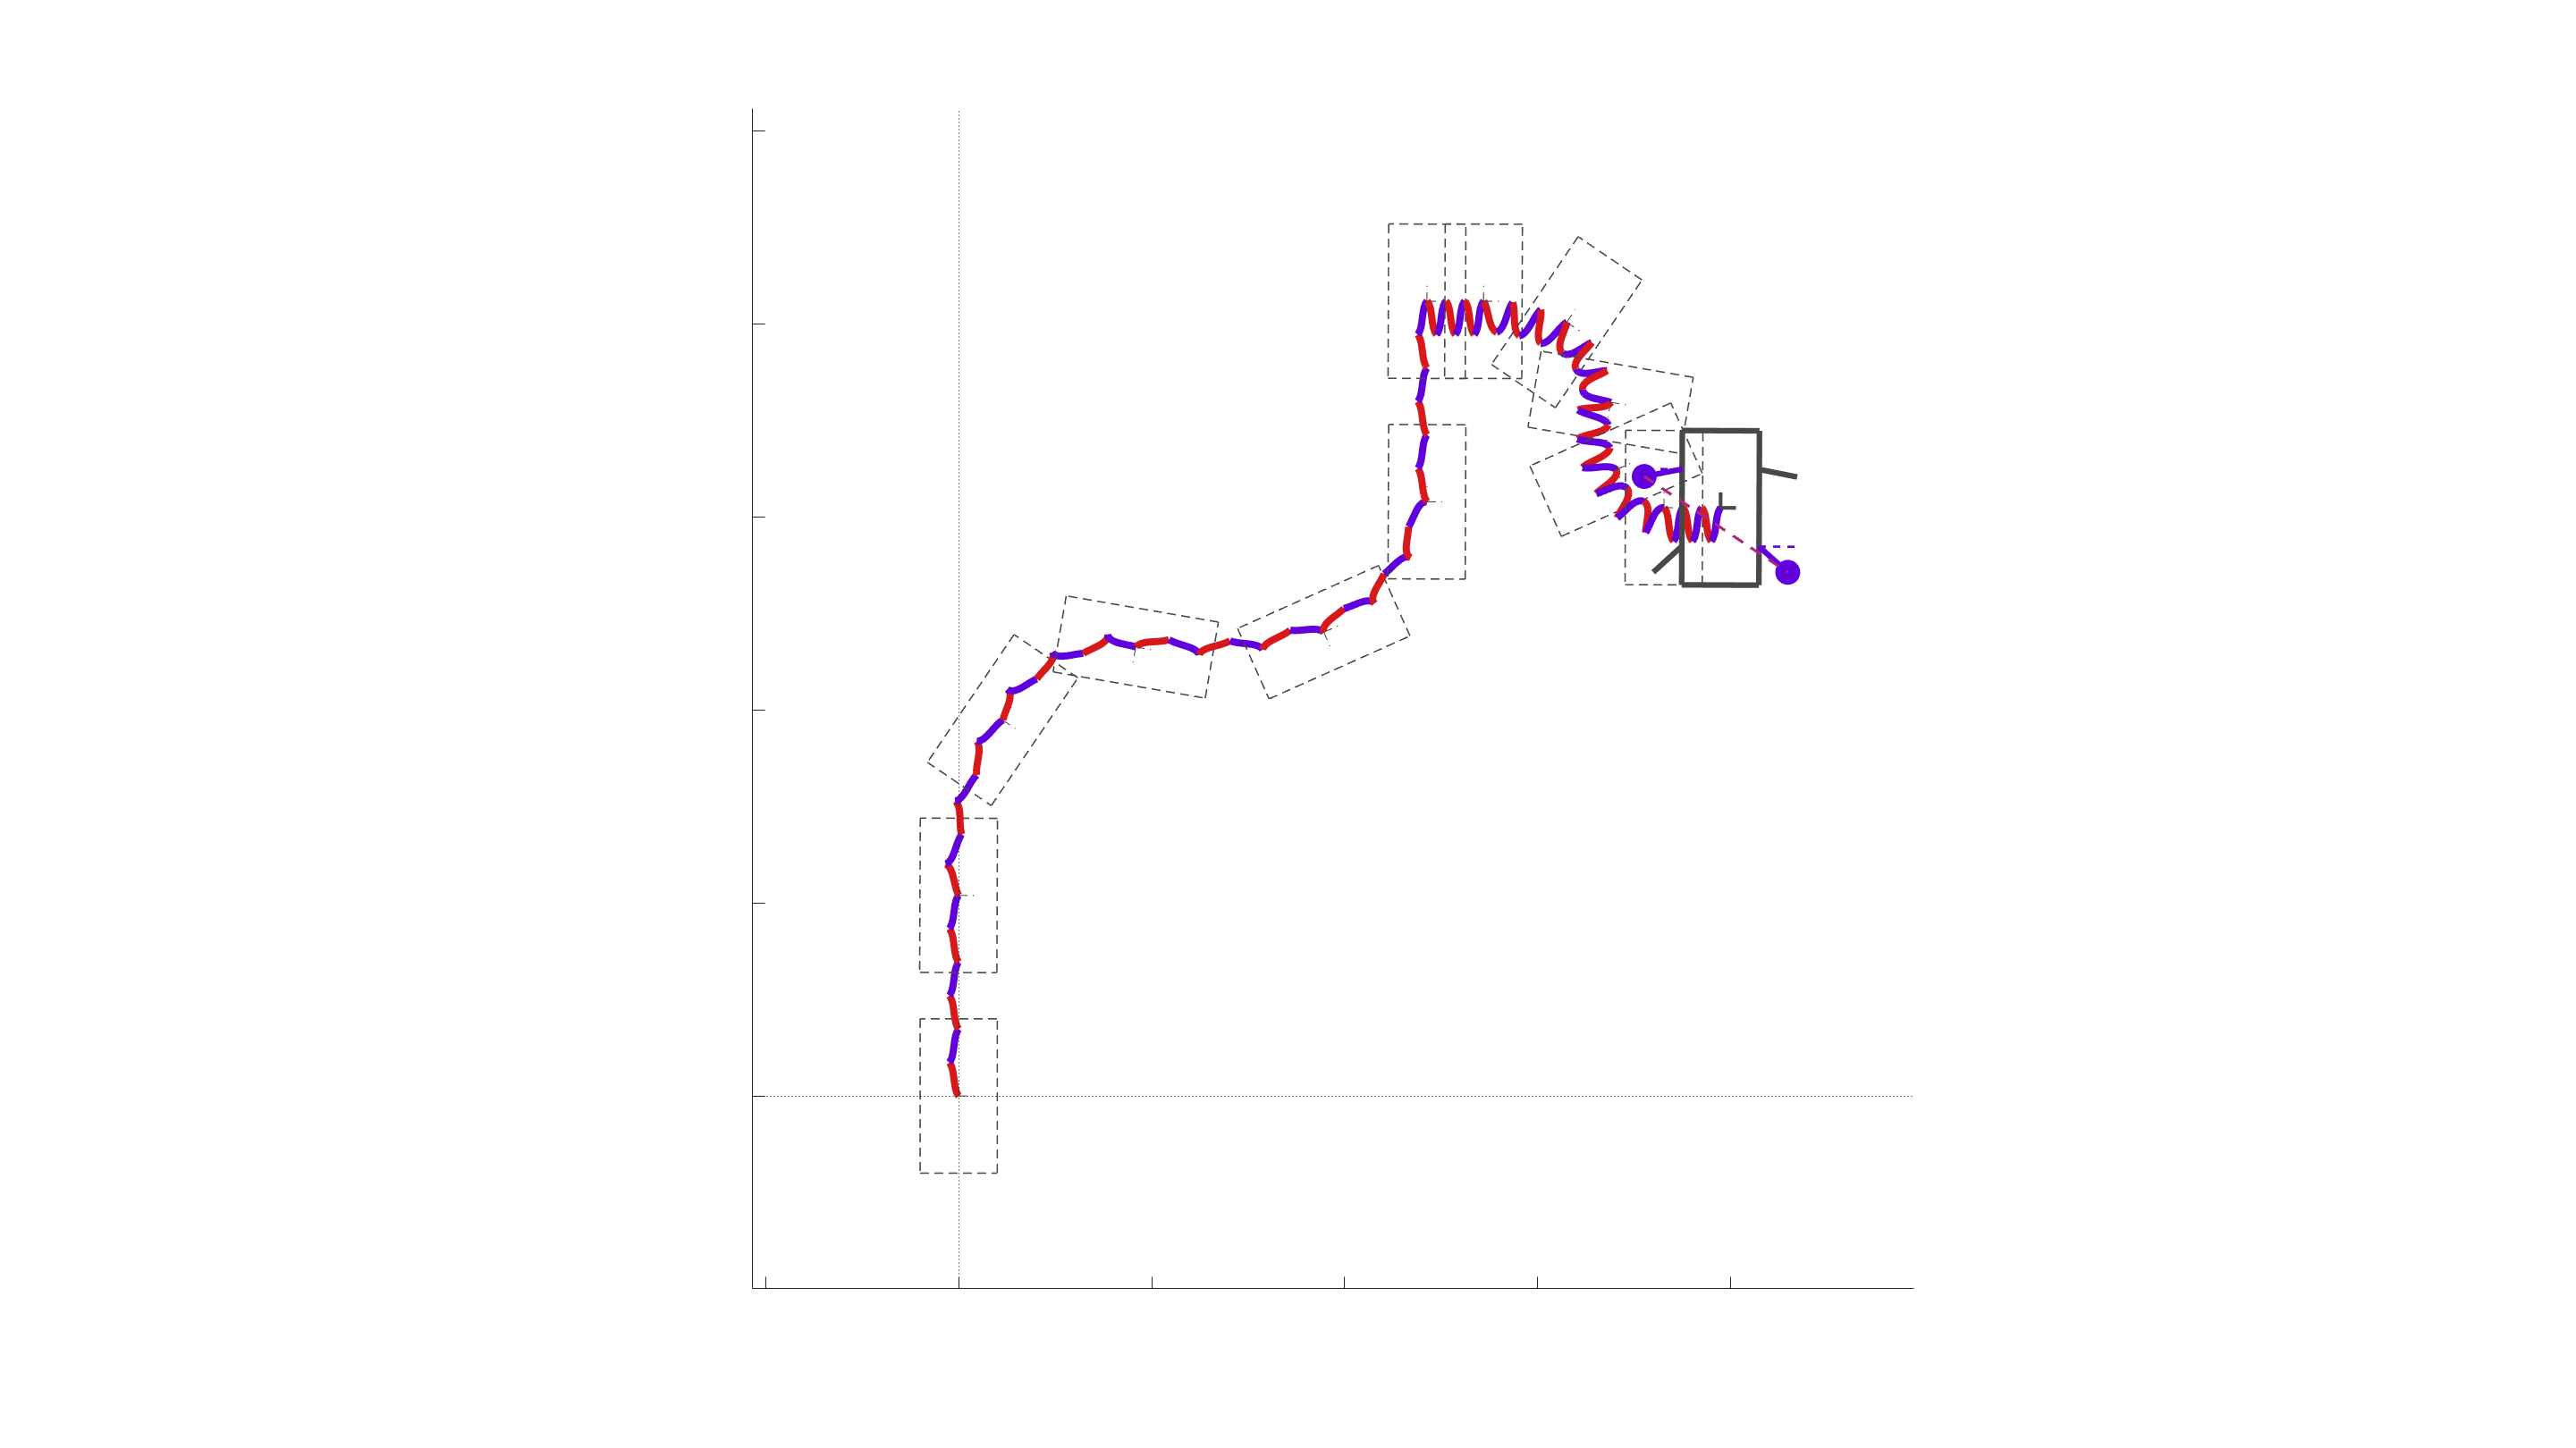


% plot
f = figure('units','pixels','position',[0 0 1920 1080],'Color','w'); ax = gca;
set(f,'Visible','on');

for i = 1:numel(t)

    if i ~= 1
        for j = 1:numel(h)
            delete(h{j}); % delete plots
        end
    end
    
    switch i == 1
        case 0
            F = [t(i-1) t(i)];
        case 1
            F = [nan t(i)];
    end
    h = plot_SE2snapshot_QLvl2_Rigid_NoSlip(ax, pltTraj, F); % SE(2) snapshot
    drawnow;

    if vidF
        writeVideo(video,getframe(f)); % get the frame
    end

end


if vidF
    close(video); % close the video
end

addpath 'Data'\ 'Utility Functions'\;
load('Data\Gen_S13toS24.mat');
load('Data\Gen_S13_data.mat'); load('Data\Gen_S24_data.mat');

Just wanna plot the zero displacement case (or close to it).

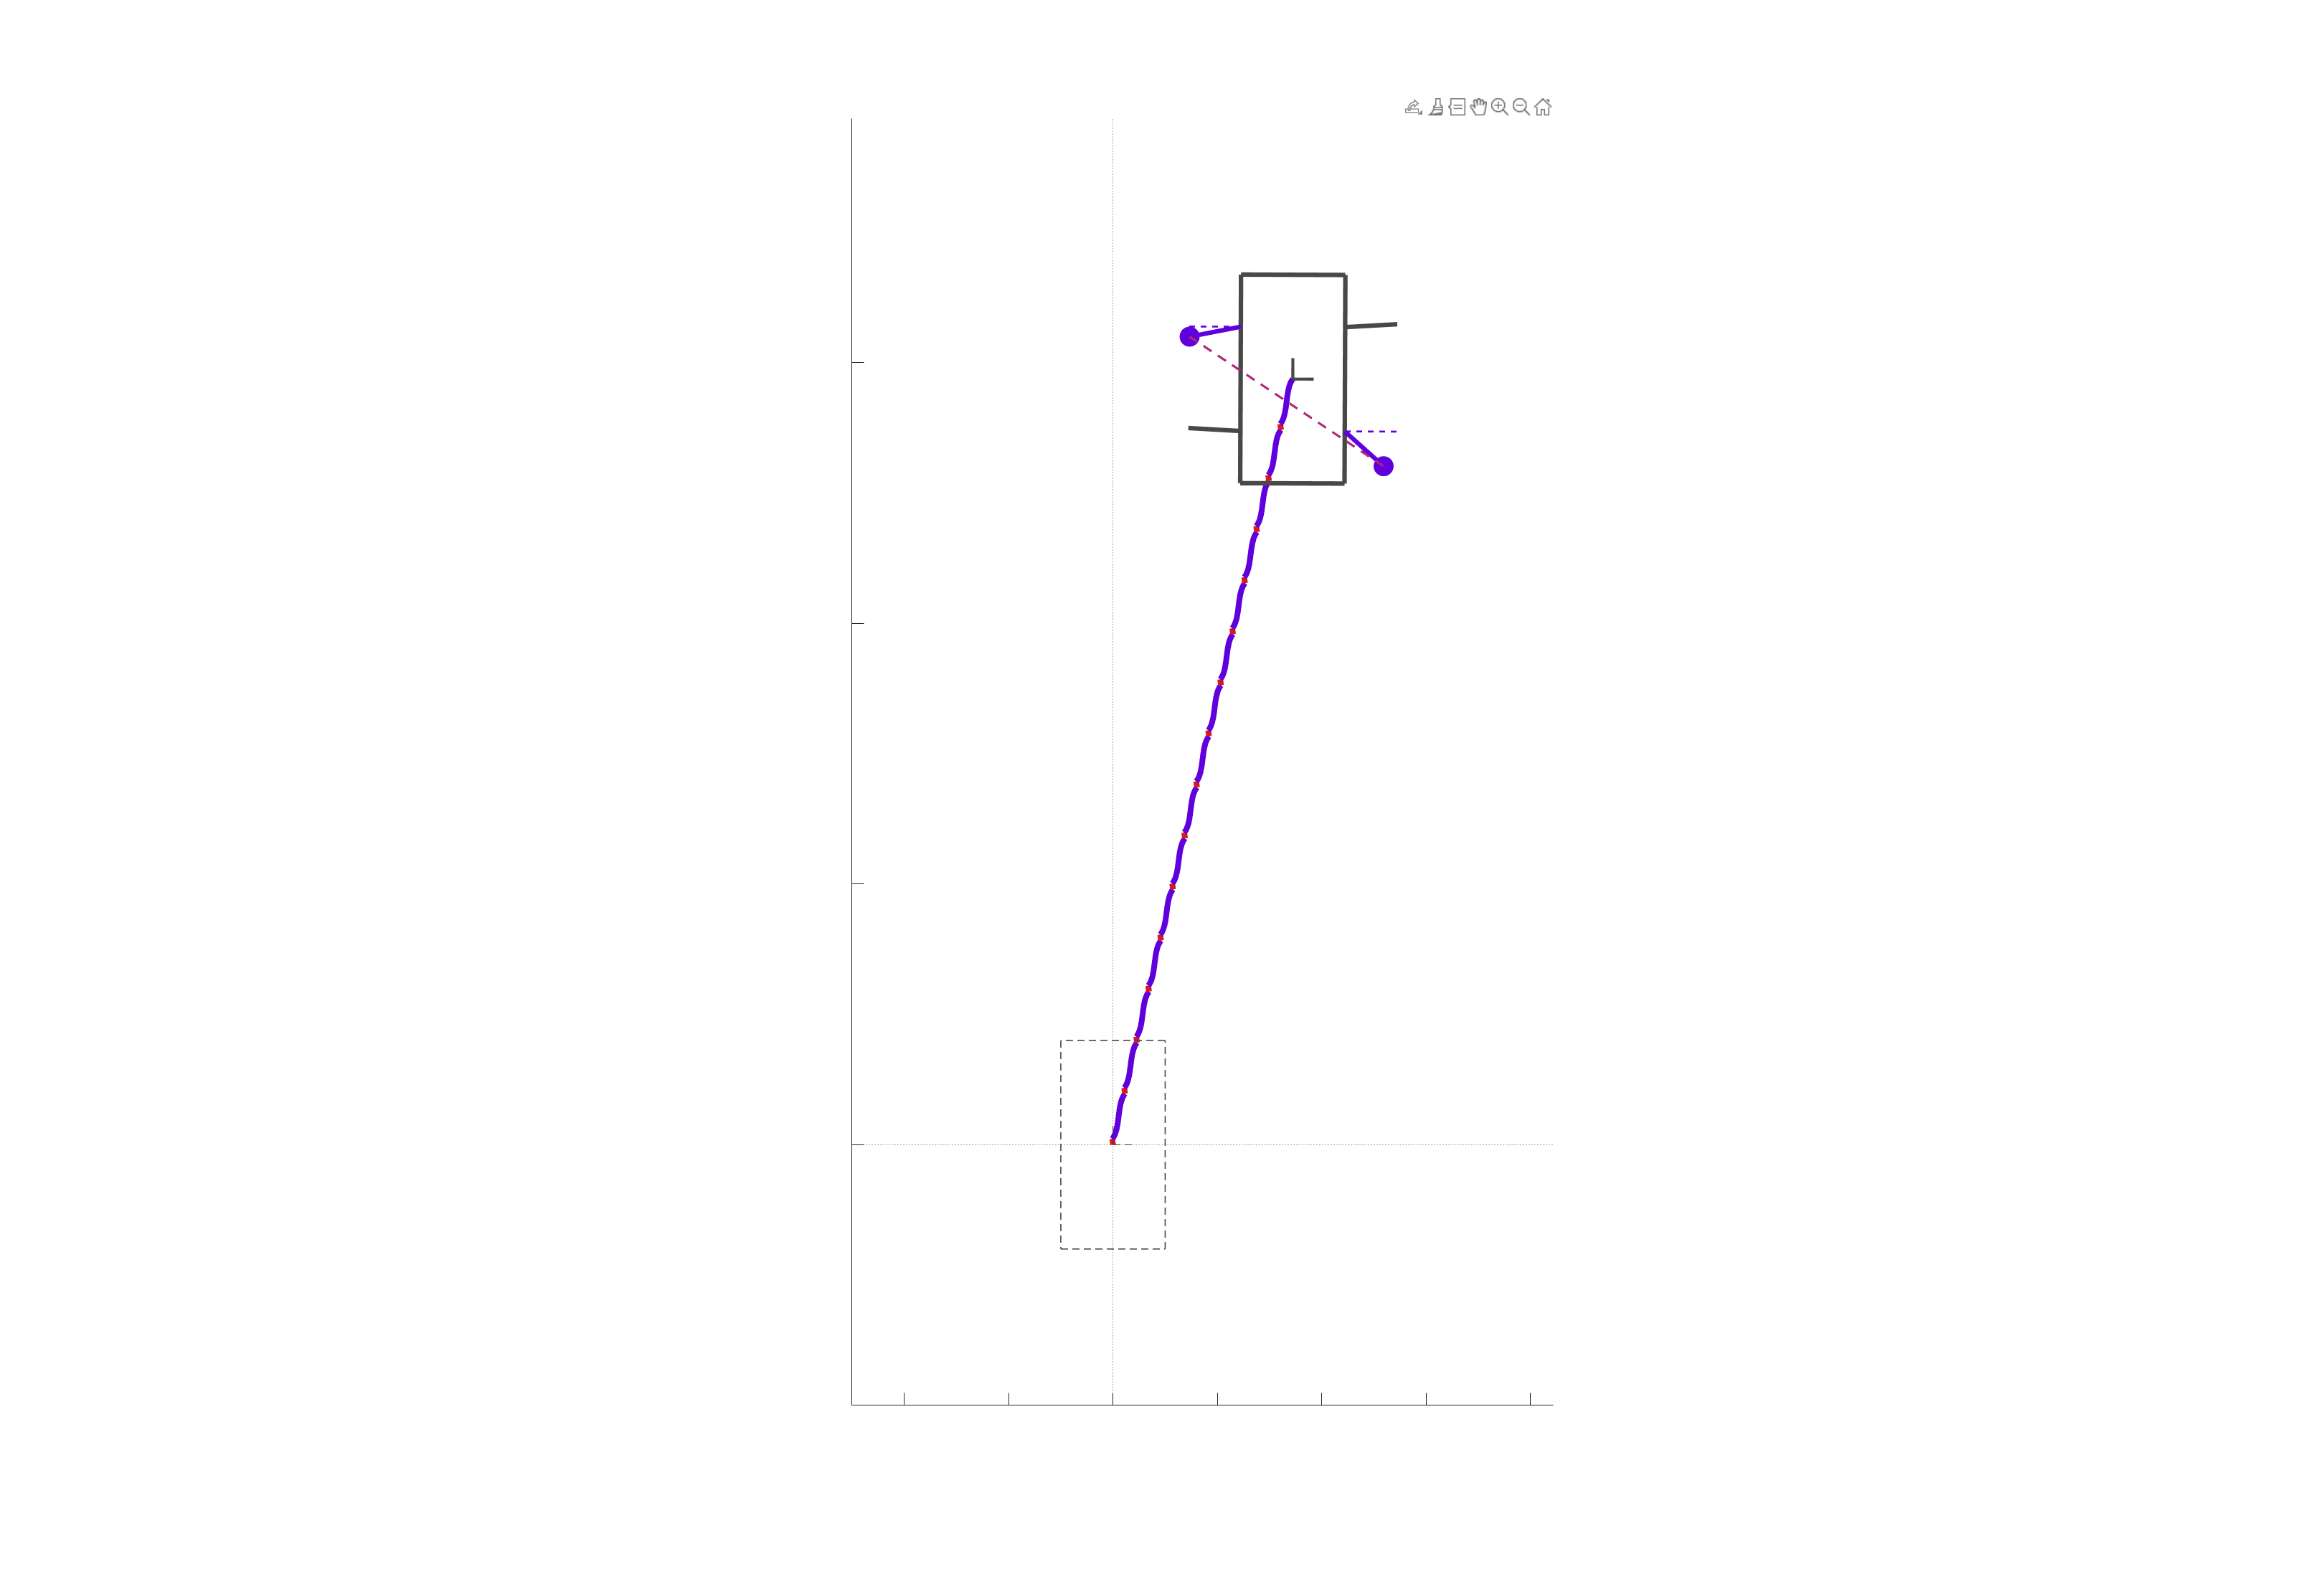

[pltTraj, ~] = stitchQuadSE2gaits({    ...
    {{S13_Gen_trans, S24_Gen_trans}},...
    {Gen_S13toS24_trans_1_data},...
    { {[0.1, 1.0]} },...
    { {15} }    });

m = 2160; n = 1800;
f = figure('units','pixels','position',[100 -200 m n],'Color','w');
set(f,'Visible','on');
plot_SE2snapshot_QLvl2_Rigid_NoSlip( gca, pltTraj);

addpath 'Data'\ 'Utility Functions'\;
load('Data\Gen_S13toS24.mat');
load('Data\Gen_S13_data.mat'); load('Data\Gen_S24_data.mat');

The average speed control case!

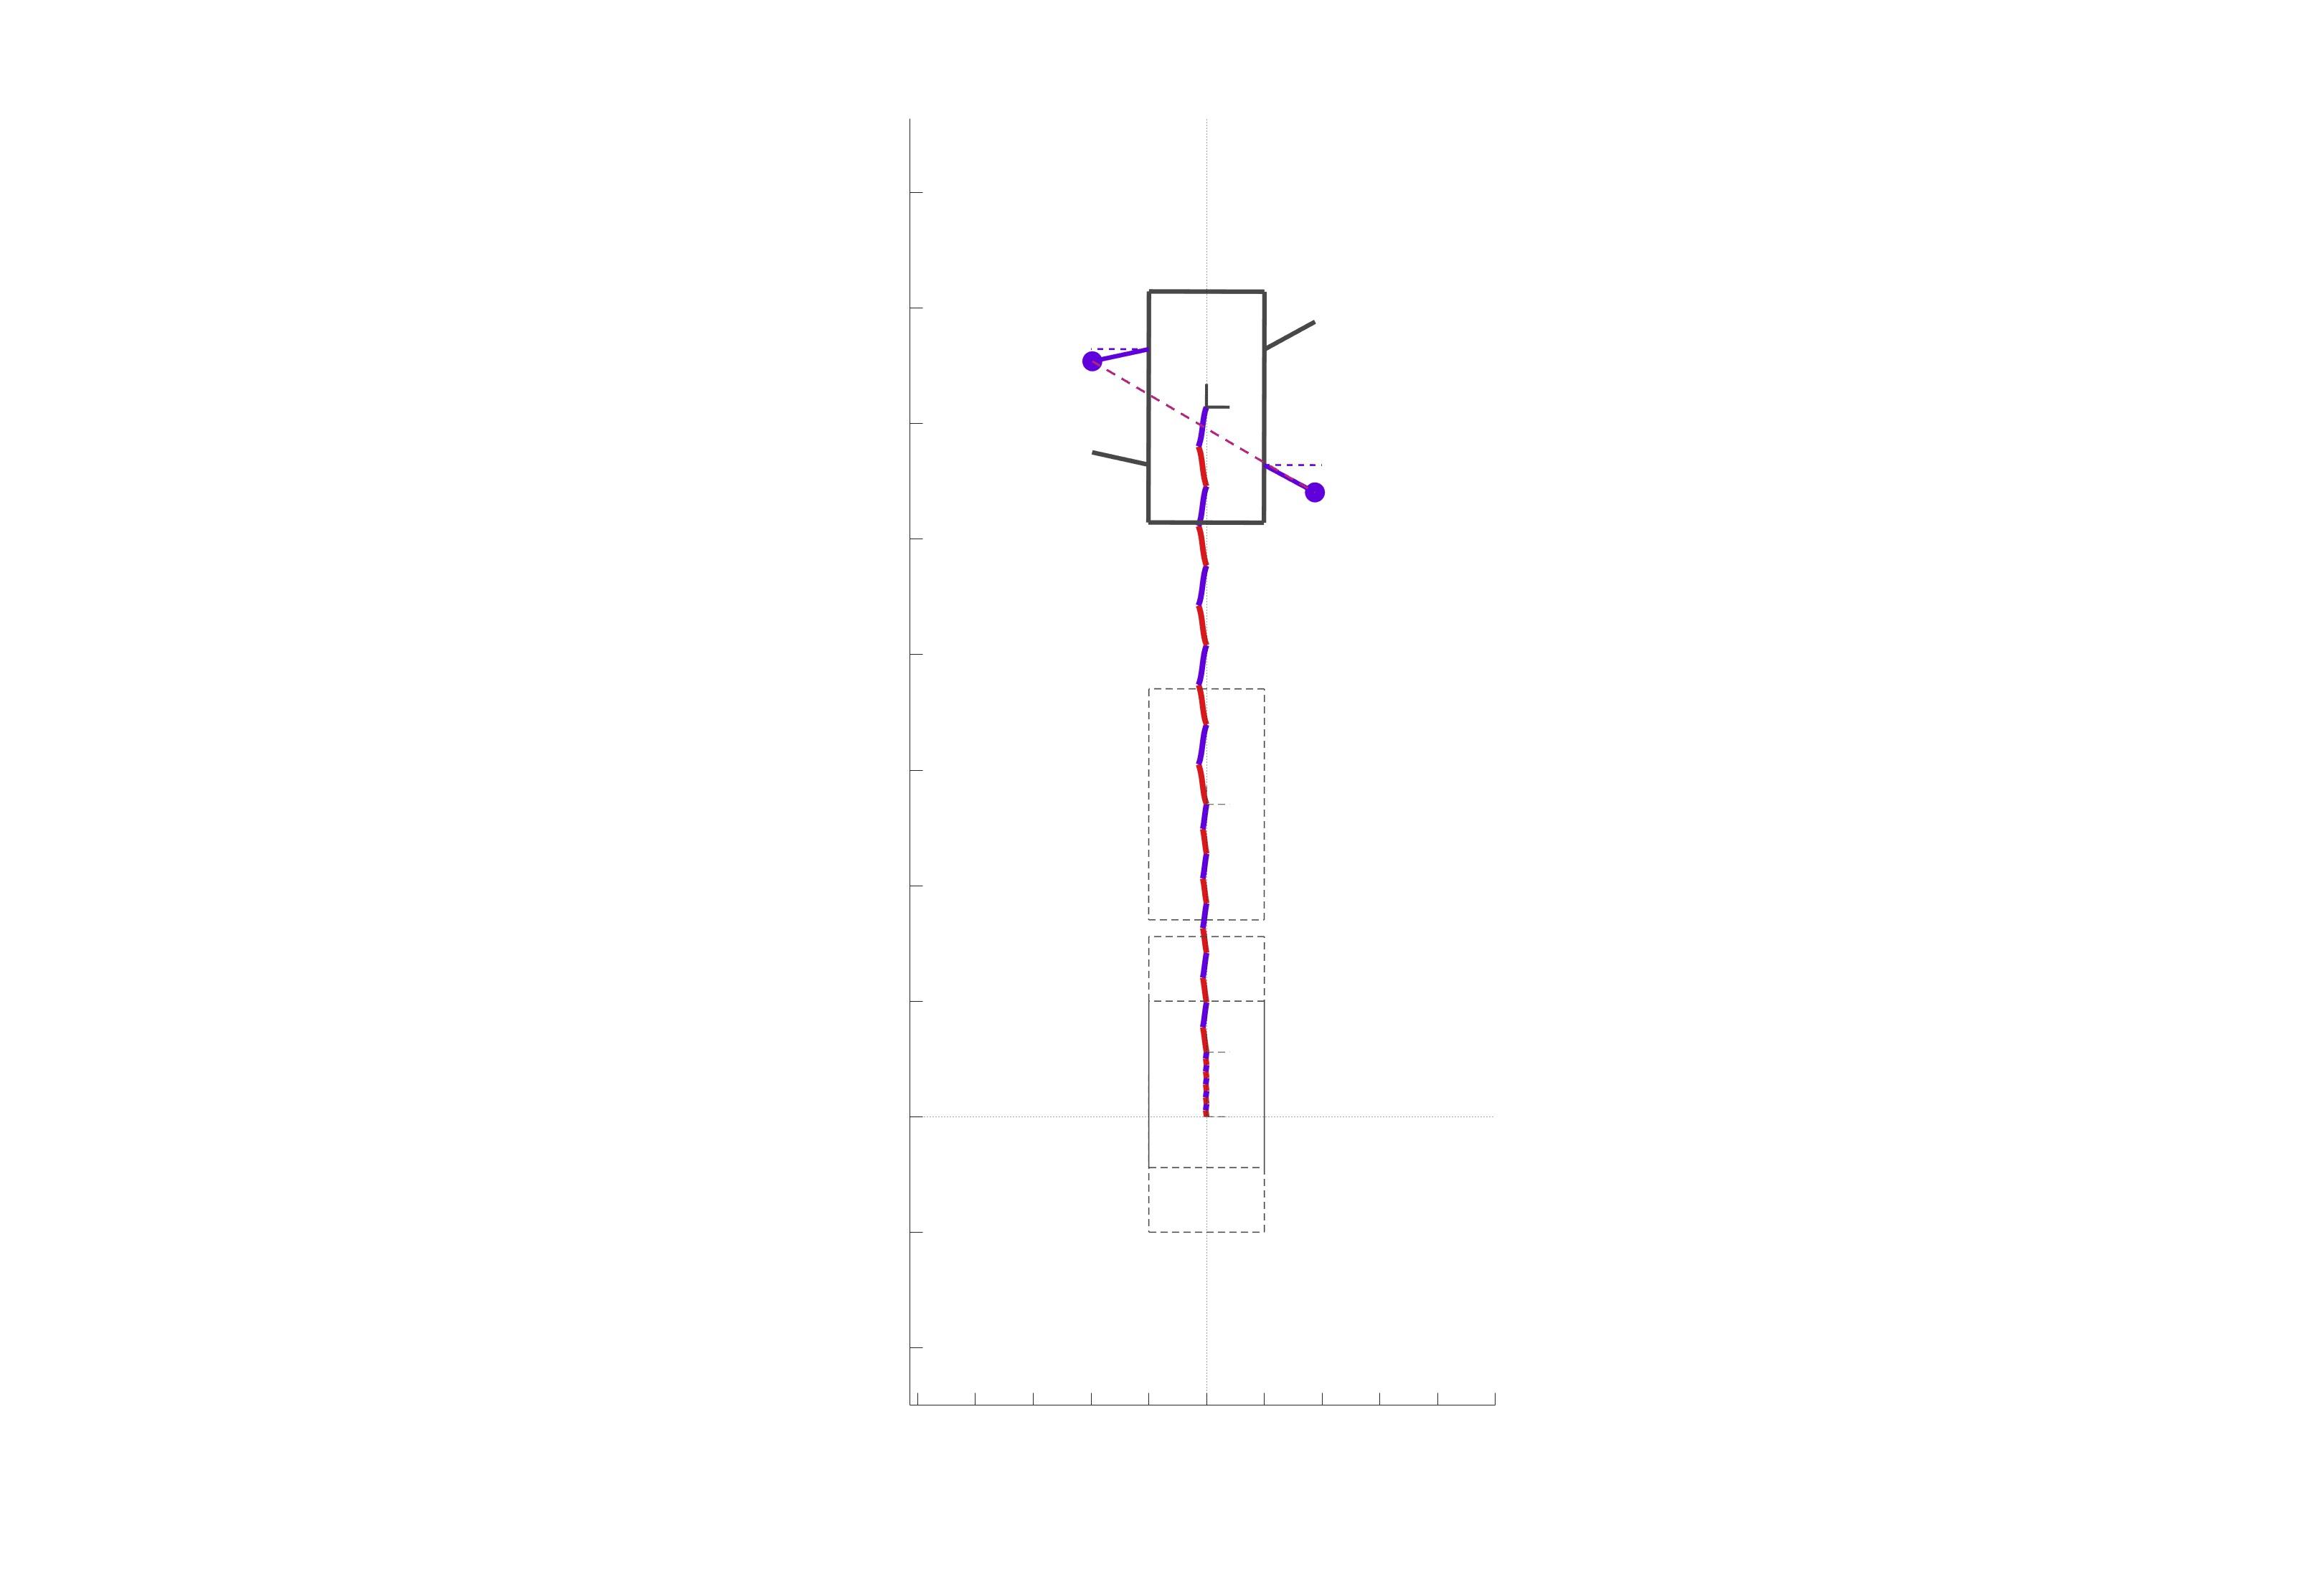

[pltTraj, traj] = stitchQuadSE2gaits({    ...
    {{S13_Gen_trans, S24_Gen_trans}},...
    {Gen_S13toS24_trans_1_data},...
    { {[0.1, 0.1], [0.4, 0.4], [0.7, 0.7]} },...
    { {5, 5, 5} }    });

m = 2160; n = 1800;
f = figure('units','pixels','position',[100 -200 m n],'Color','w');
set(f,'Visible','on');
plot_SE2snapshot_QLvl2_Rigid_NoSlip( gca, pltTraj);

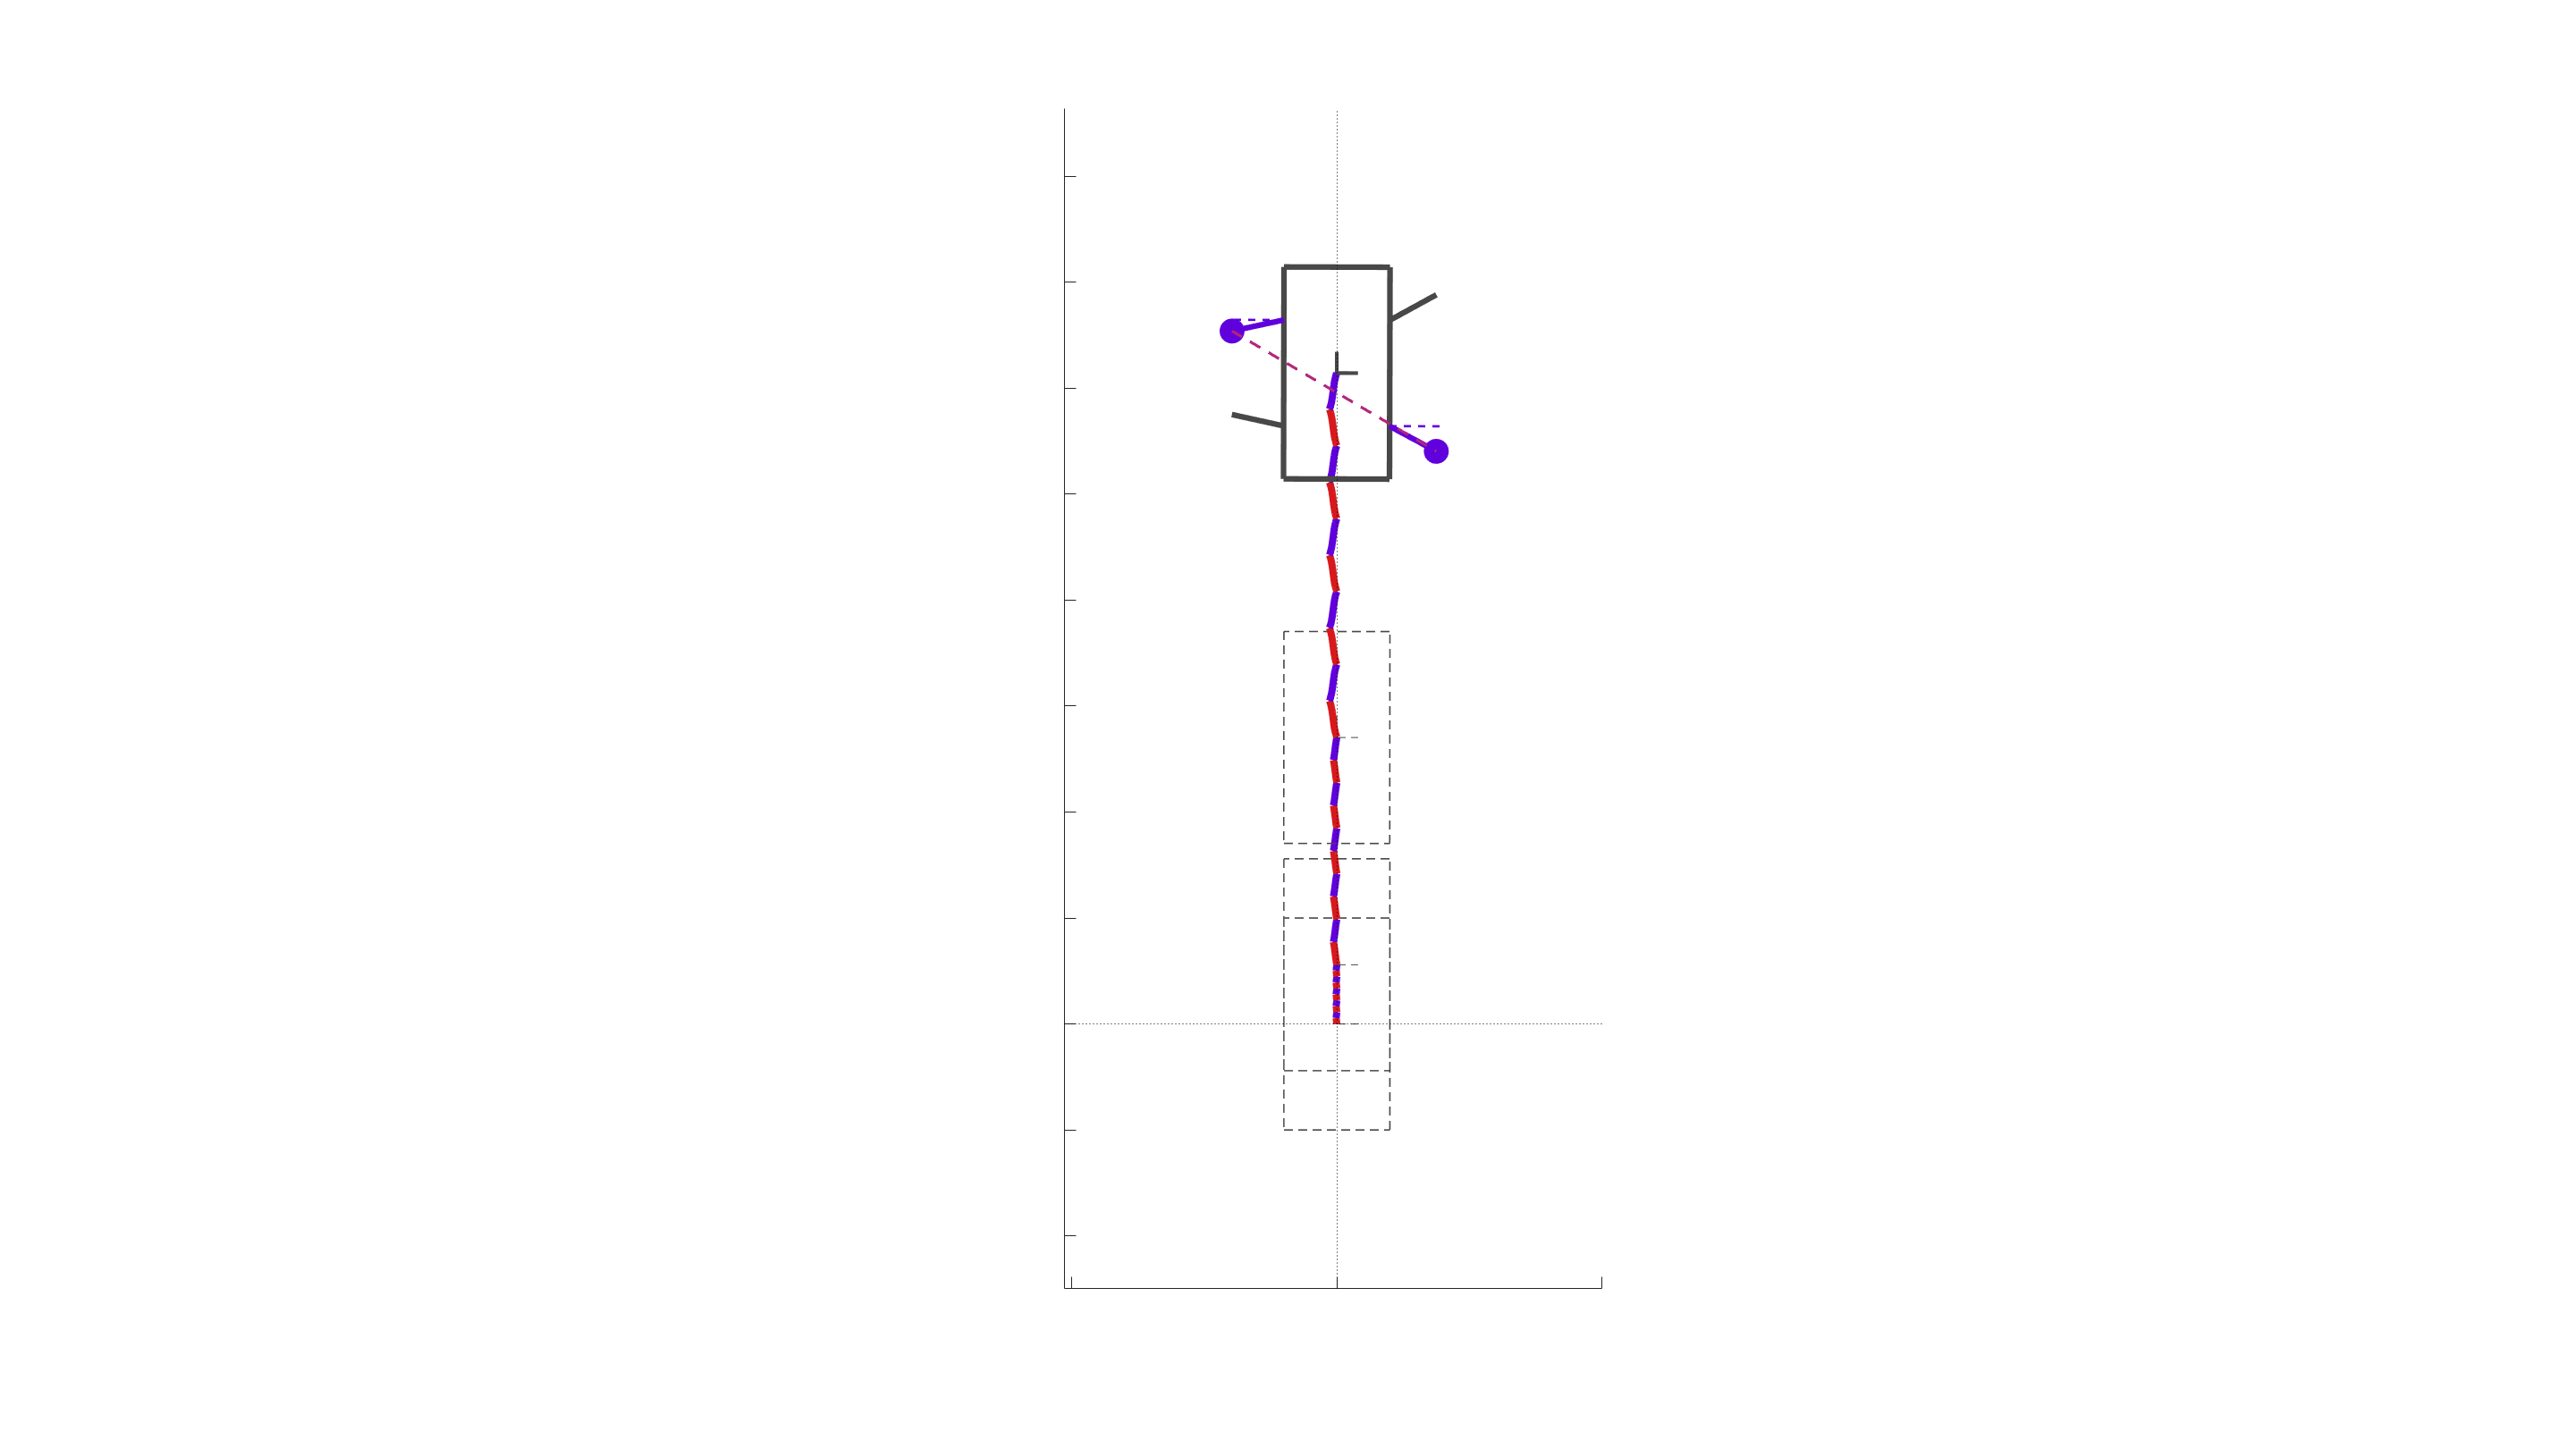

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
v = [];
save_addr = '';
save_name = 'composite_gait_2';

vid_time = 10;
v.fps = 60;
t = round(linspace(1, traj.dnum, v.fps*vid_time));
if t(end) < traj.dnum
    t(end+1) = traj.dnum;
end
vidF = true;
v.Name = [save_addr save_name];
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

if vidF
    video = VideoWriter([v.Name,'.mp4'],'MPEG-4');
    video.FrameRate = v.fps;
    video.Quality = 100;
    open(video);
end
f = figure('units','pixels','position',[0 0 1920 1080],'Color','w'); ax = gca;
set(f,'Visible','on');
for i = 1:numel(t)
    if i ~= 1
        for j = 1:numel(h)
            delete(h{j});
        end
    end
    switch i == 1
        case 0
            F = [t(i-1) t(i)];
        case 1
            F = [nan t(i)];
    end
    h = plot_SE2snapshot_QLvl2_Rigid_NoSlip(ax, pltTraj, F);
    drawnow;
    if vidF
        writeVideo(video,getframe(f));
    end

end

if vidF
    close(video)
end

addpath 'Data'\ 'Utility Functions'\;
load('Data\Gen_S13toS24.mat');
load('Data\Gen_S13_data.mat'); load('Data\Gen_S24_data.mat');

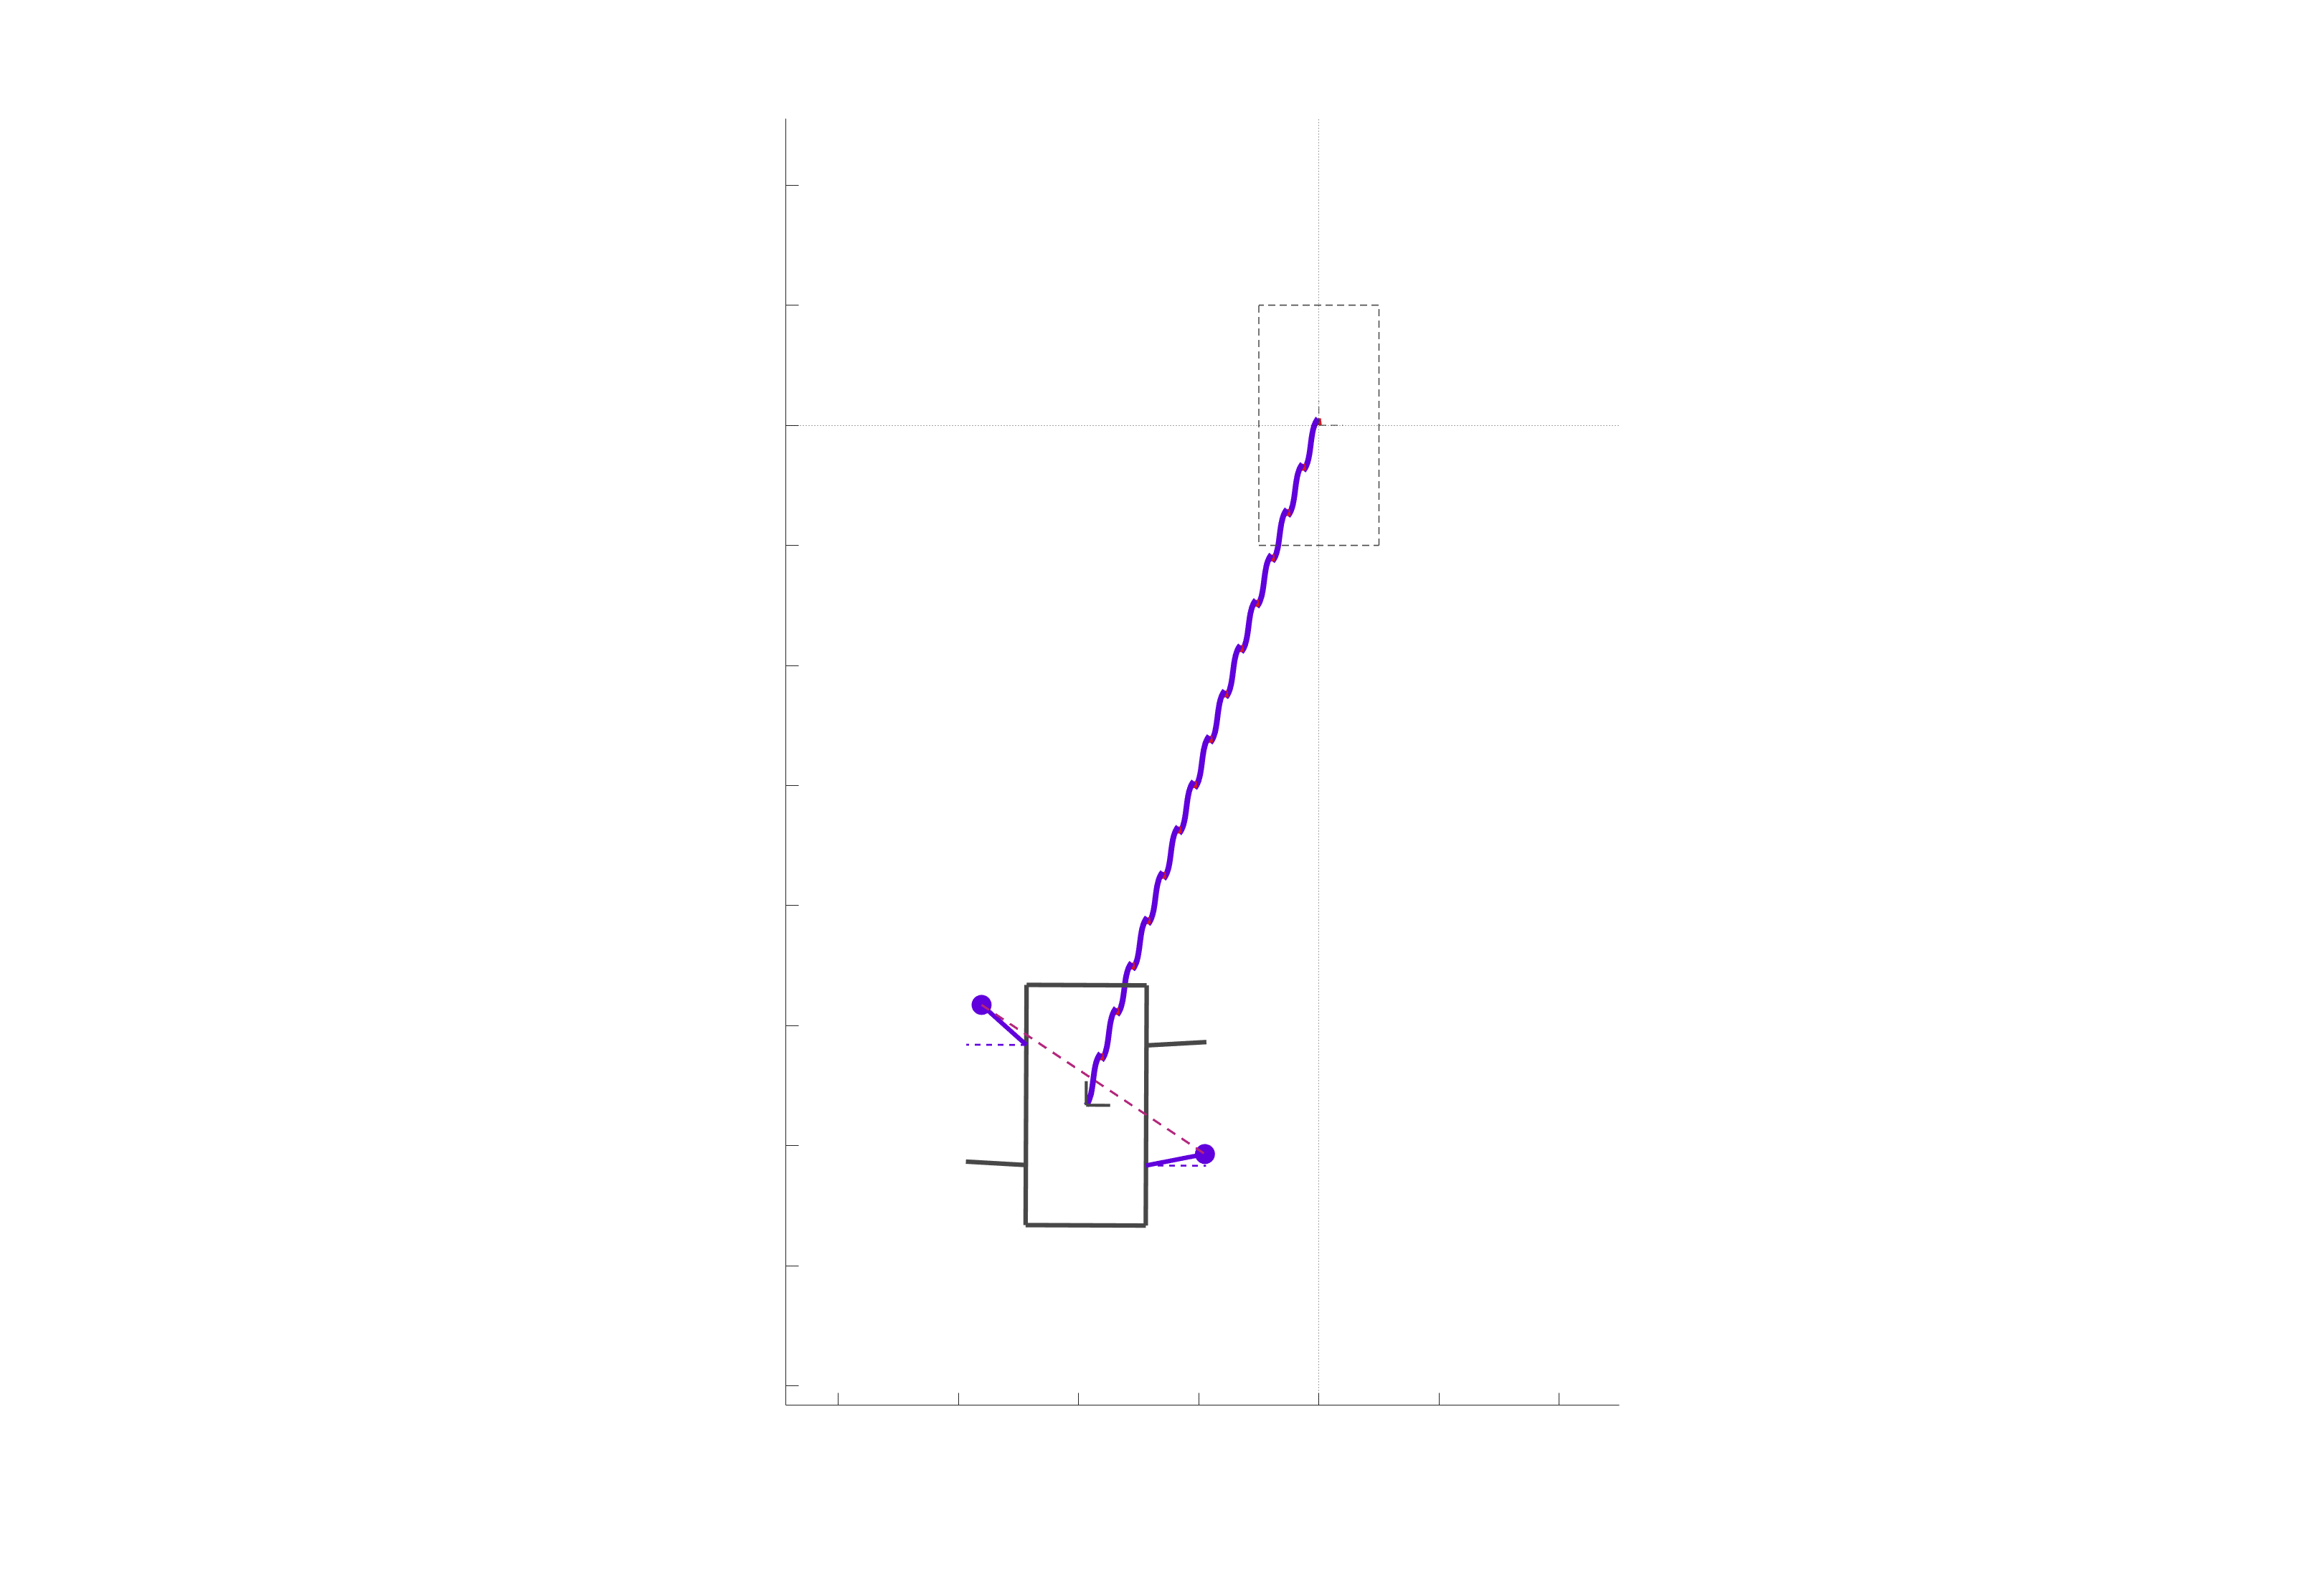

[pltTraj, traj] = stitchQuadSE2gaits({    ...
    {{S13_Gen_trans, S24_Gen_trans}},...
    {Gen_S13toS24_trans_1_data},...
    { {[0.1, -1]} },...
    { {15} }    });

m = 2160; n = 1800;
f = figure('units','pixels','position',[100 -200 m n],'Color','w');
set(f,'Visible','on');
plot_SE2snapshot_QLvl2_Rigid_NoSlip( gca, pltTraj);

% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
v = [];
save_addr = '';
save_name = 'composite_gait_3_DL';

vid_time = 10;
v.fps = 60;
t = round(linspace(1, traj.dnum, v.fps*vid_time));
if t(end) < traj.dnum
    t(end+1) = traj.dnum;
end
vidF = true;
v.Name = [save_addr save_name];
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

if vidF
    video = VideoWriter([v.Name,'.mp4'],'MPEG-4');
    video.FrameRate = v.fps;
    video.Quality = 100;
    open(video);
end
f = figure('units','pixels','position',[0 0 1920 1080],'Color','w'); ax = gca;
set(f,'Visible','on');
for i = 1:numel(t)
    if i ~= 1
        for j = 1:numel(h)
            delete(h{j});
        end
    end
    switch i == 1
        case 0
            F = [t(i-1) t(i)];
        case 1
            F = [nan t(i)];
    end
    h = plot_SE2snapshot_QLvl2_Rigid_NoSlip(ax, pltTraj, F);
    drawnow;
    if vidF
        writeVideo(video,getframe(f));
    end

end
if vidF
    close(video)
end

addpath 'Data'\ 'Utility Functions'\;
load('Data\Gen_S13toS24.mat');
load('Data\Gen_S13_data.mat'); load('Data\Gen_S24_data.mat');

Need a similar snapshot for a translational gait-- both forward and lateral.

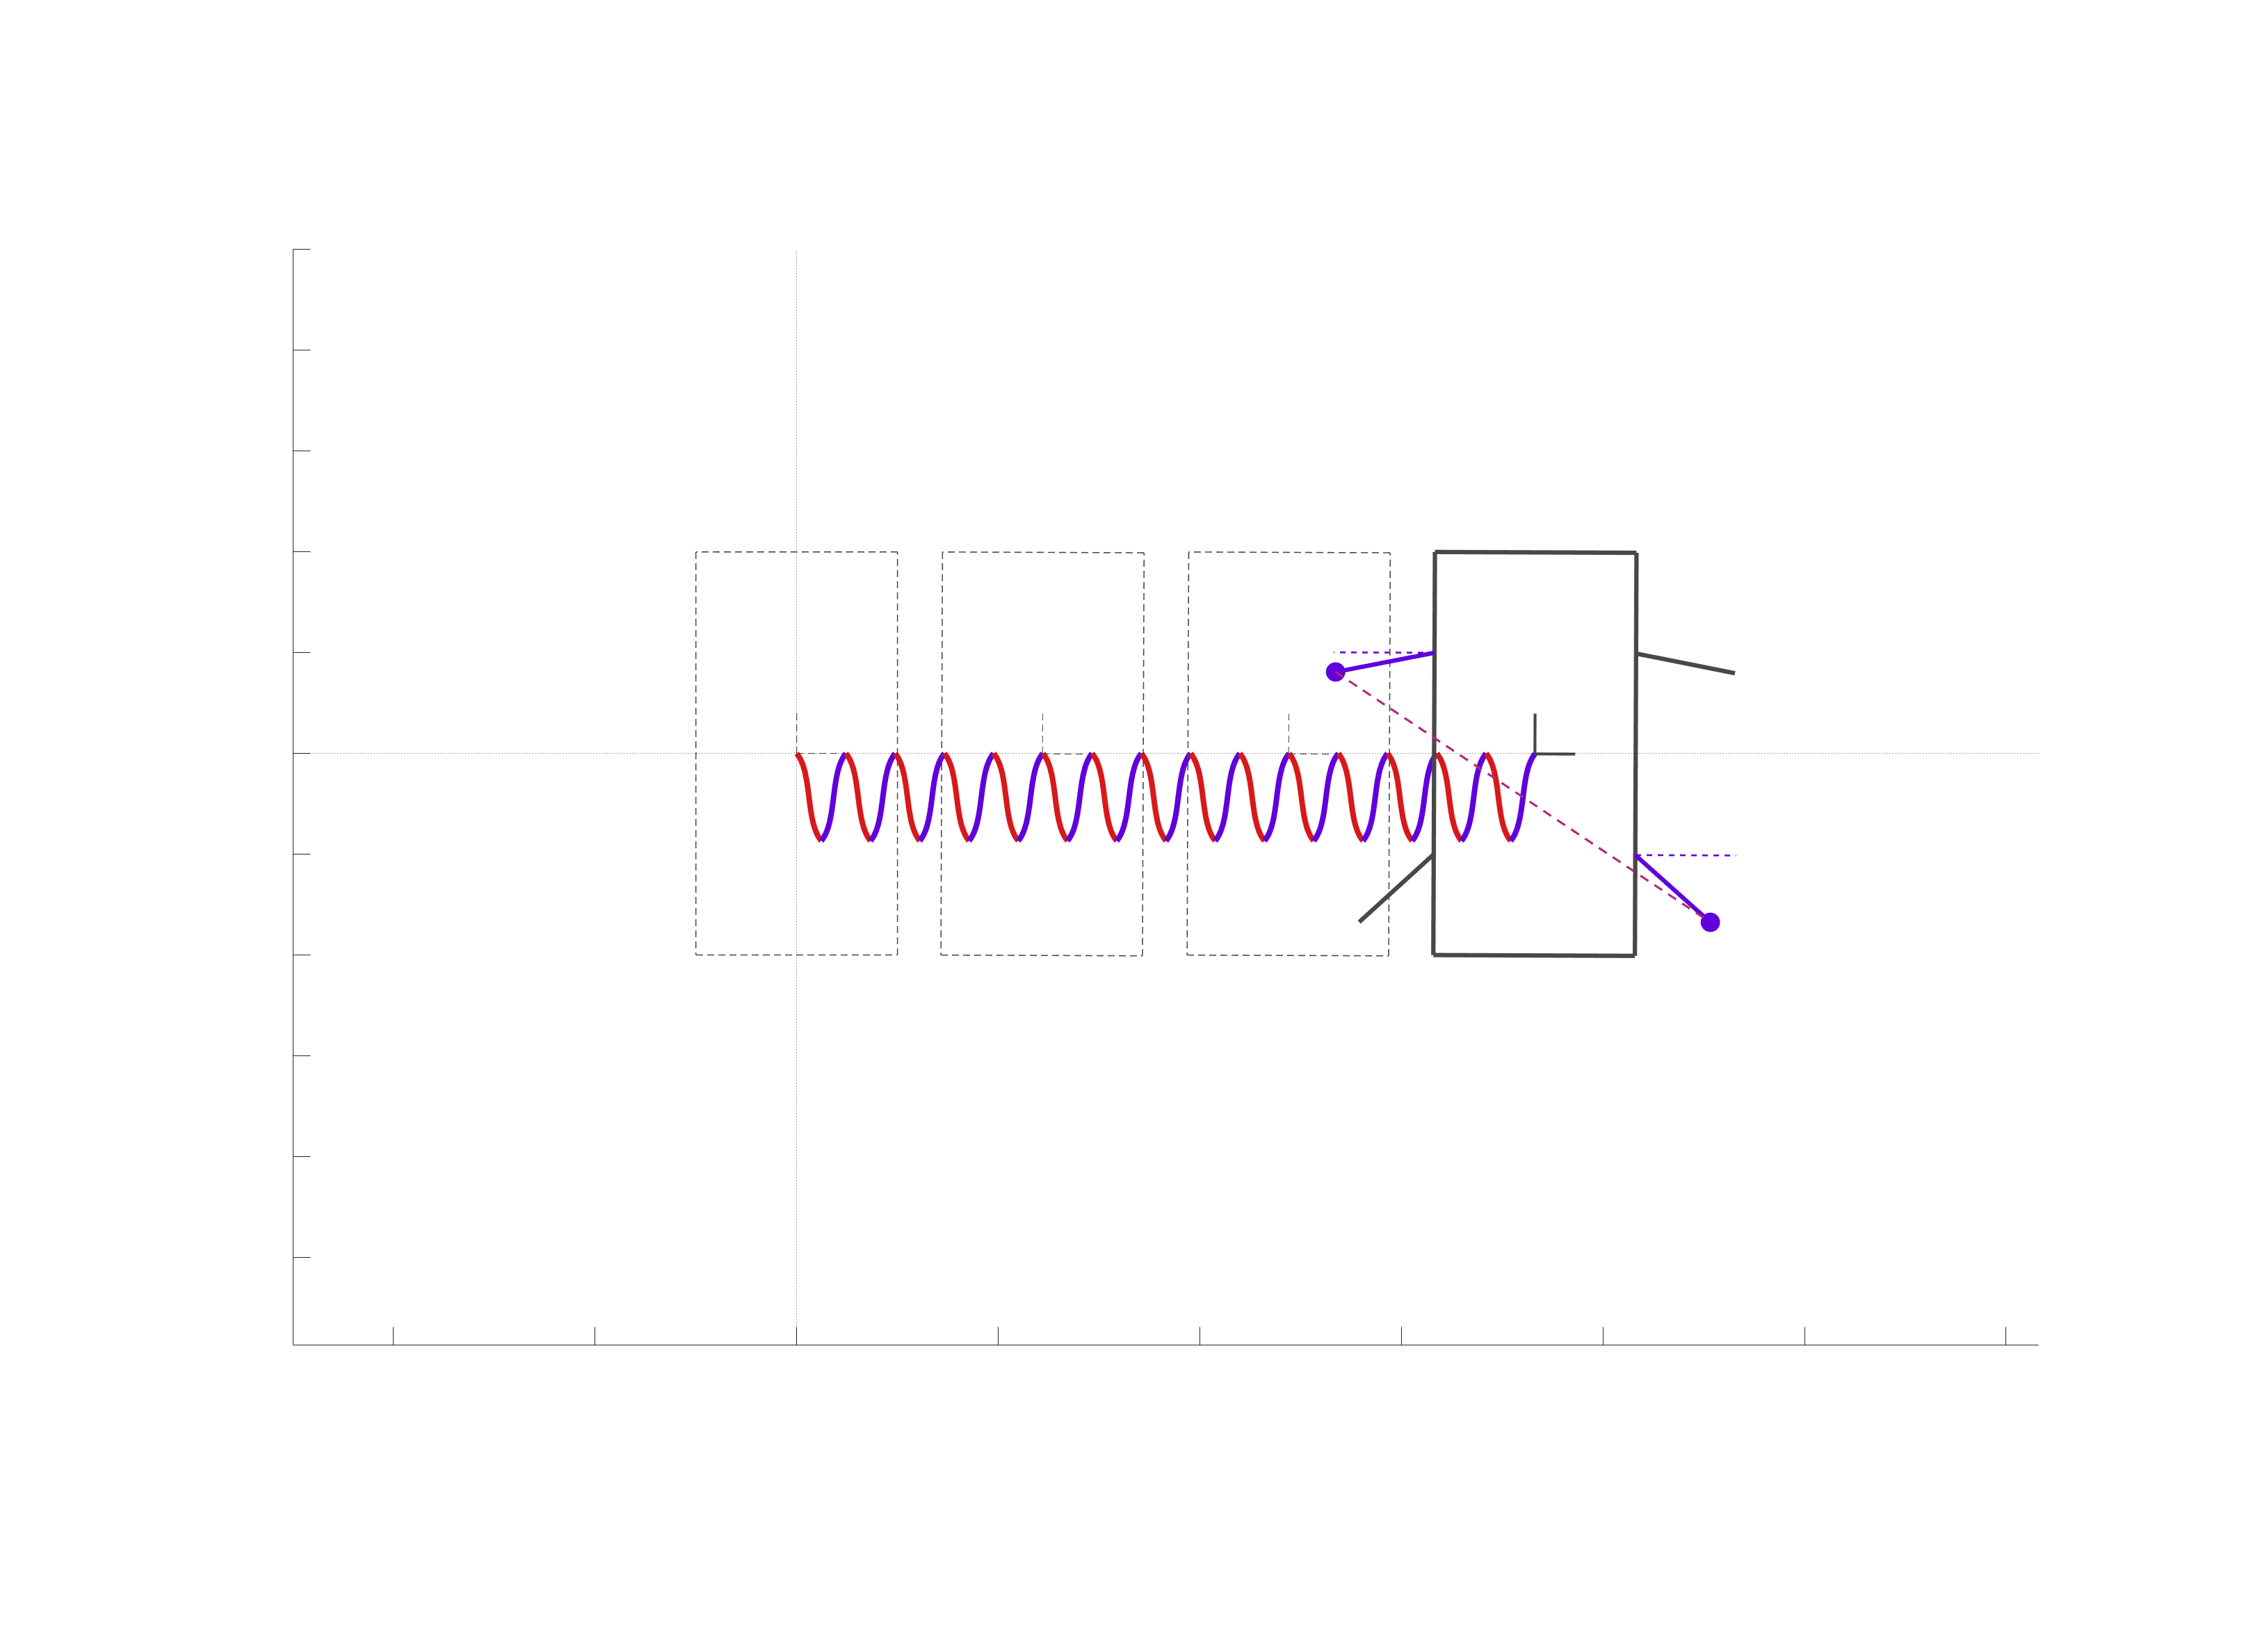

[pltTraj, traj] = stitchQuadSE2gaits({    ...
    {{S13_Gen_trans, S24_Gen_trans}, {S13_Gen_trans, S24_Gen_trans}, {S13_Gen_trans, S24_Gen_trans}},...
    {Gen_S13toS24_trans_1_data, Gen_S13toS24_trans_1_data, Gen_S13toS24_trans_1_data},...
    { {[-1, 1]}, {[-1, 1]}, {[-1, 1]} },... % {[1, 1]}, {[1, 1]}, {[1, 1]} % {[-1, 1]}, {[-1, 1]}, {[-1, 1]}
    { {5},      {5},      {5} }...
                                     });
% Create the SE(2) snapshot
m = 2160; n = 1800; % fixed resolution
f = figure('units','pixels','position',[100 -200 m n],'Color','w');
set(gcf,'Visible','on'); % pop-out figure
hA = plot_SE2snapshot_QLvl2_Rigid_NoSlip( gca, pltTraj);

Create a translation video.

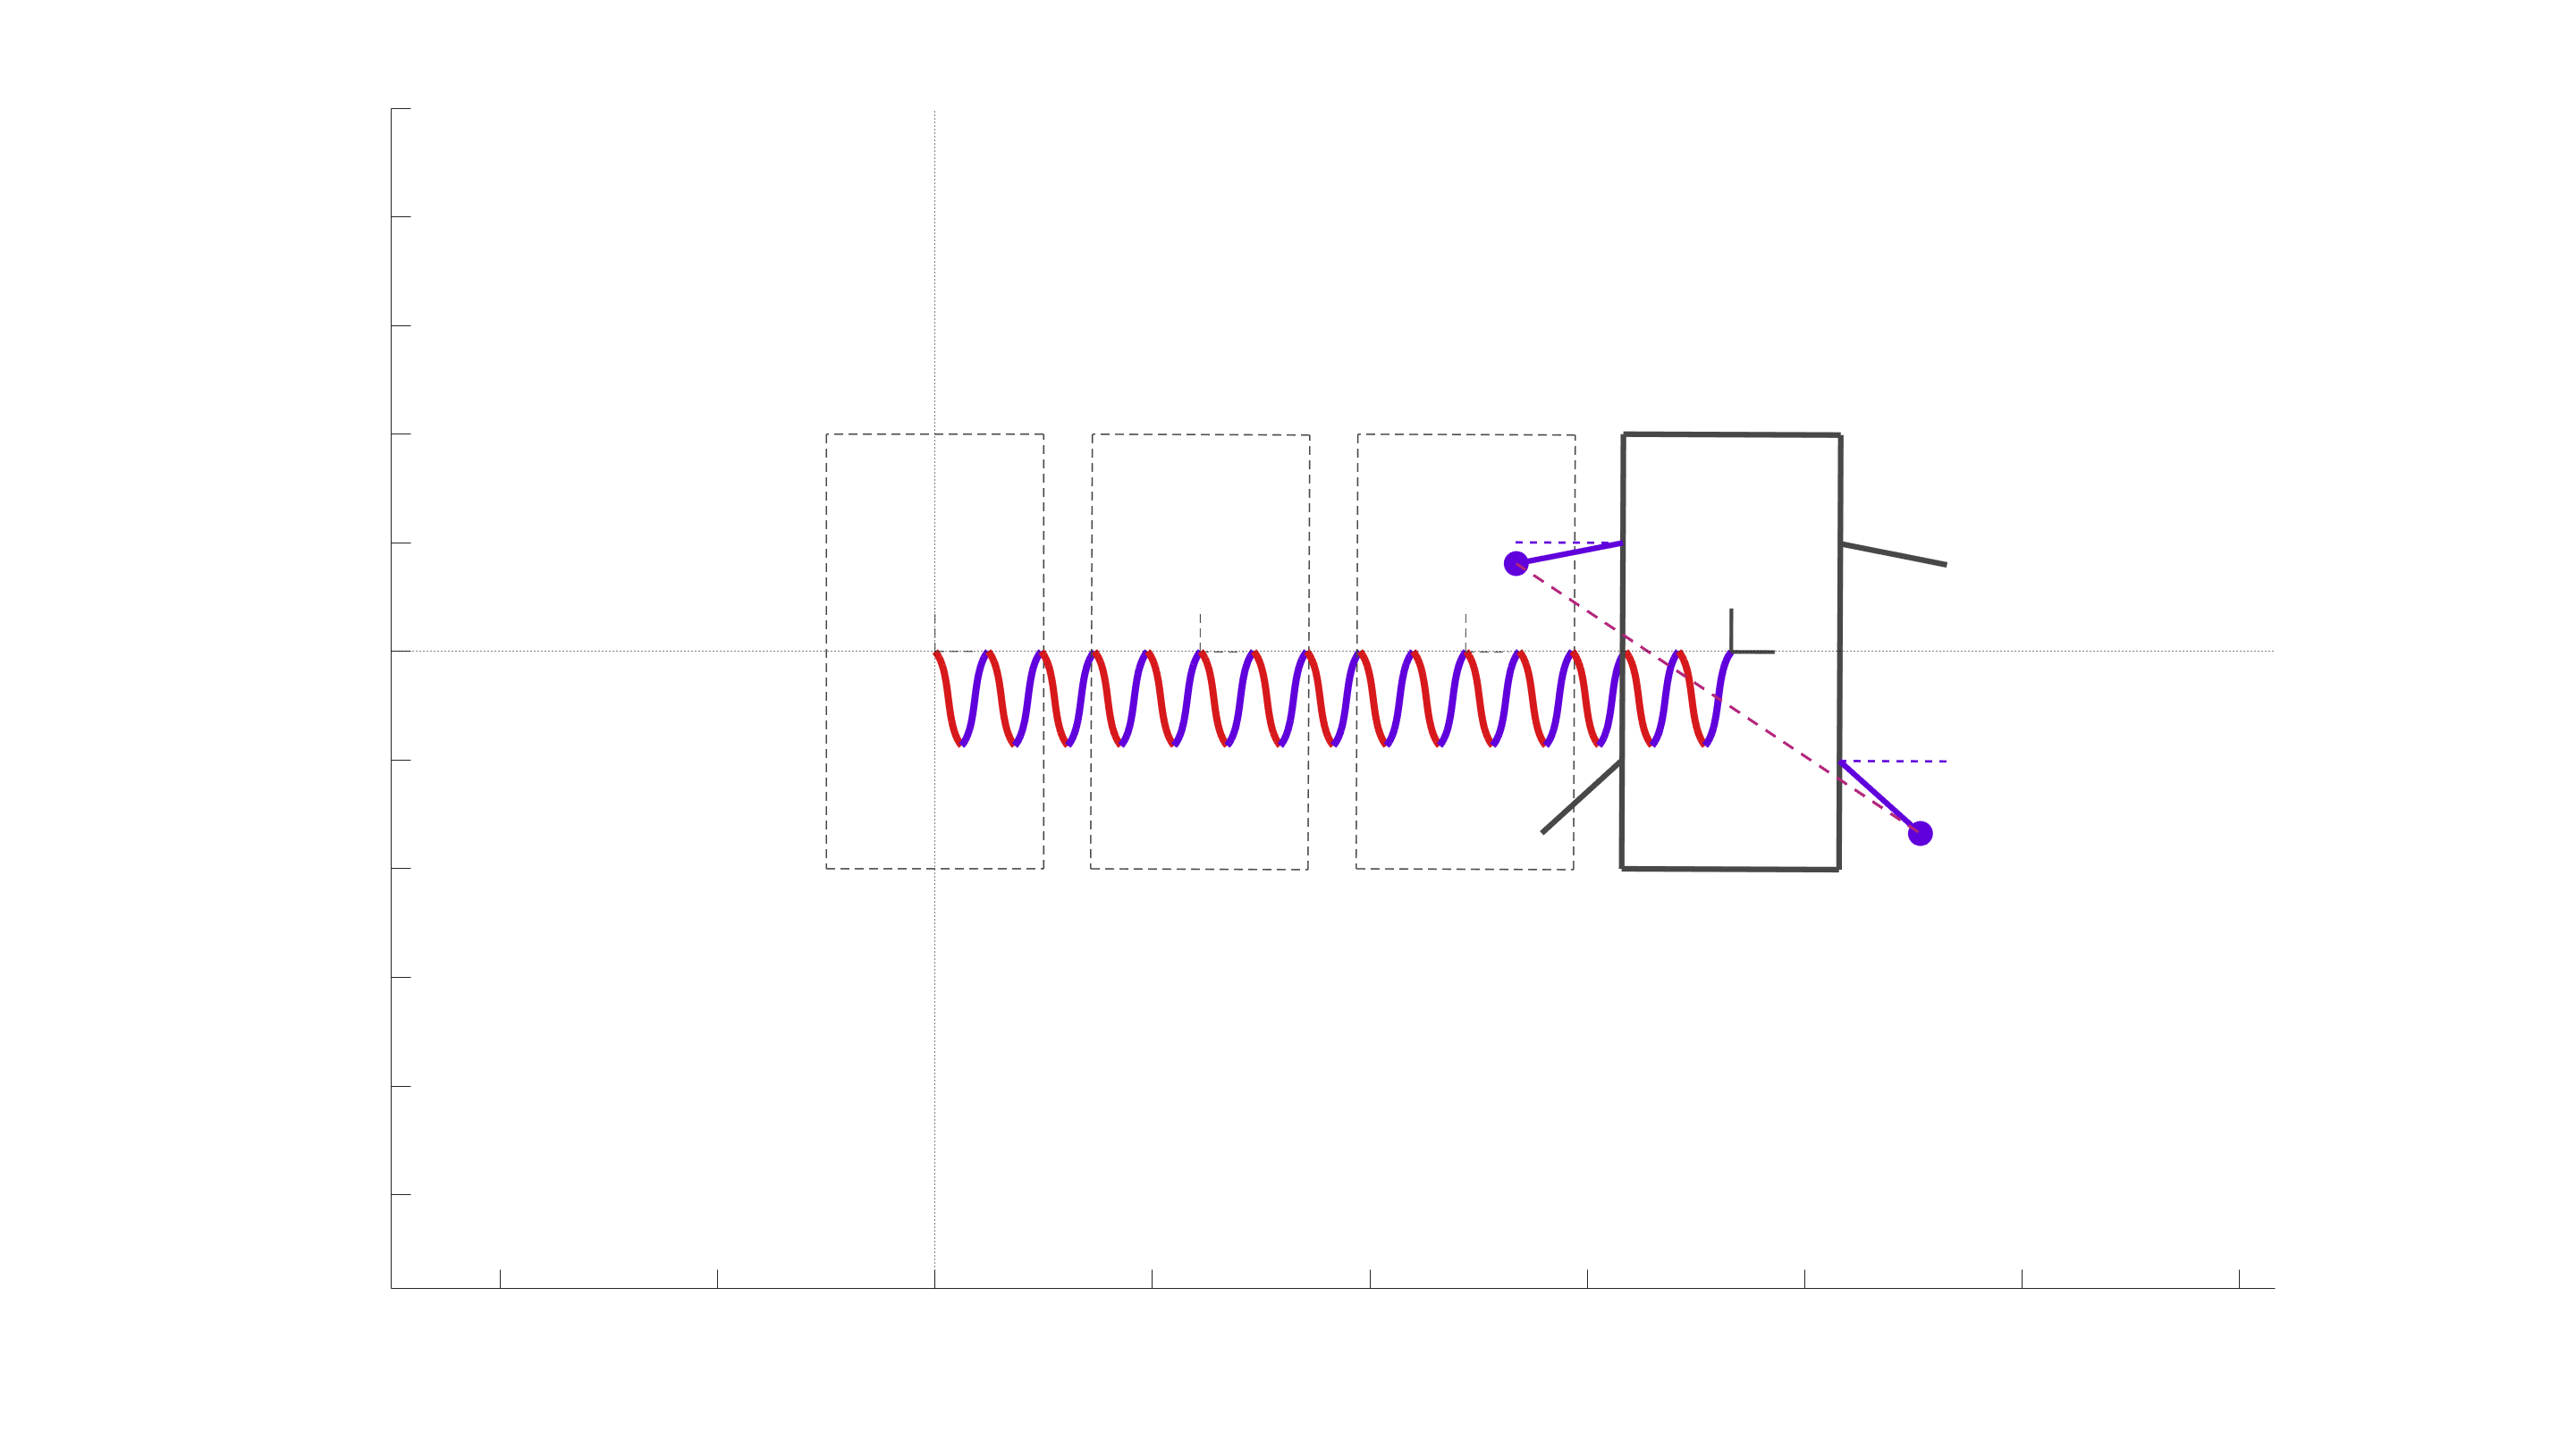

% data ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
v = [];
save_addr = ''; % change to local address
save_name = 'translation_gait_2'; % translation_gait_1 % translation_gait_2

% get the points along the trajectory to animate
vid_time = 10; % in secs
v.fps = 60; % frames per second
% t = extractTimeVectorForCompGaitAnimation( traj.dnum, traj.gcVec, v.fps*vid_time, 'first' ); % slow down just the first gait cycle in each composite gait
t = round(linspace(1, traj.dnum, v.fps*vid_time));
if t(end) < traj.dnum
    t(end+1) = traj.dnum;
end
vidF = true;
v.Name = [save_addr save_name];
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% initialize video
if vidF
    video = VideoWriter([v.Name,'.mp4'],'MPEG-4');
    video.FrameRate = v.fps;
    video.Quality = 100;
    open(video);
end

% plot
f = figure('units','pixels','position',[0 0 1920 1080],'Color','w'); ax = gca;
set(f,'Visible','on');

for i = 1:numel(t)

    if i ~= 1
        for j = 1:numel(h)
            delete(h{j}); % delete plots
        end
    end
    
    switch i == 1
        case 0
            F = [t(i-1) t(i)];
        case 1
            F = [nan t(i)];
    end
    h = plot_SE2snapshot_QLvl2_Rigid_NoSlip(ax, pltTraj, F); % SE(2) snapshot
    drawnow;

    if vidF
        writeVideo(video,getframe(f)); % get the frame
    end

end

if vidF
    close(video); % close the video
end

addpath 'Data'\ 'Utility Functions'\;
load('Data\Gen_S13toS24.mat');
load('Data\Gen_S13_data.mat'); load('Data\Gen_S24_data.mat');

Replicate trial and trans as closely as possible-- (1, 0.7).

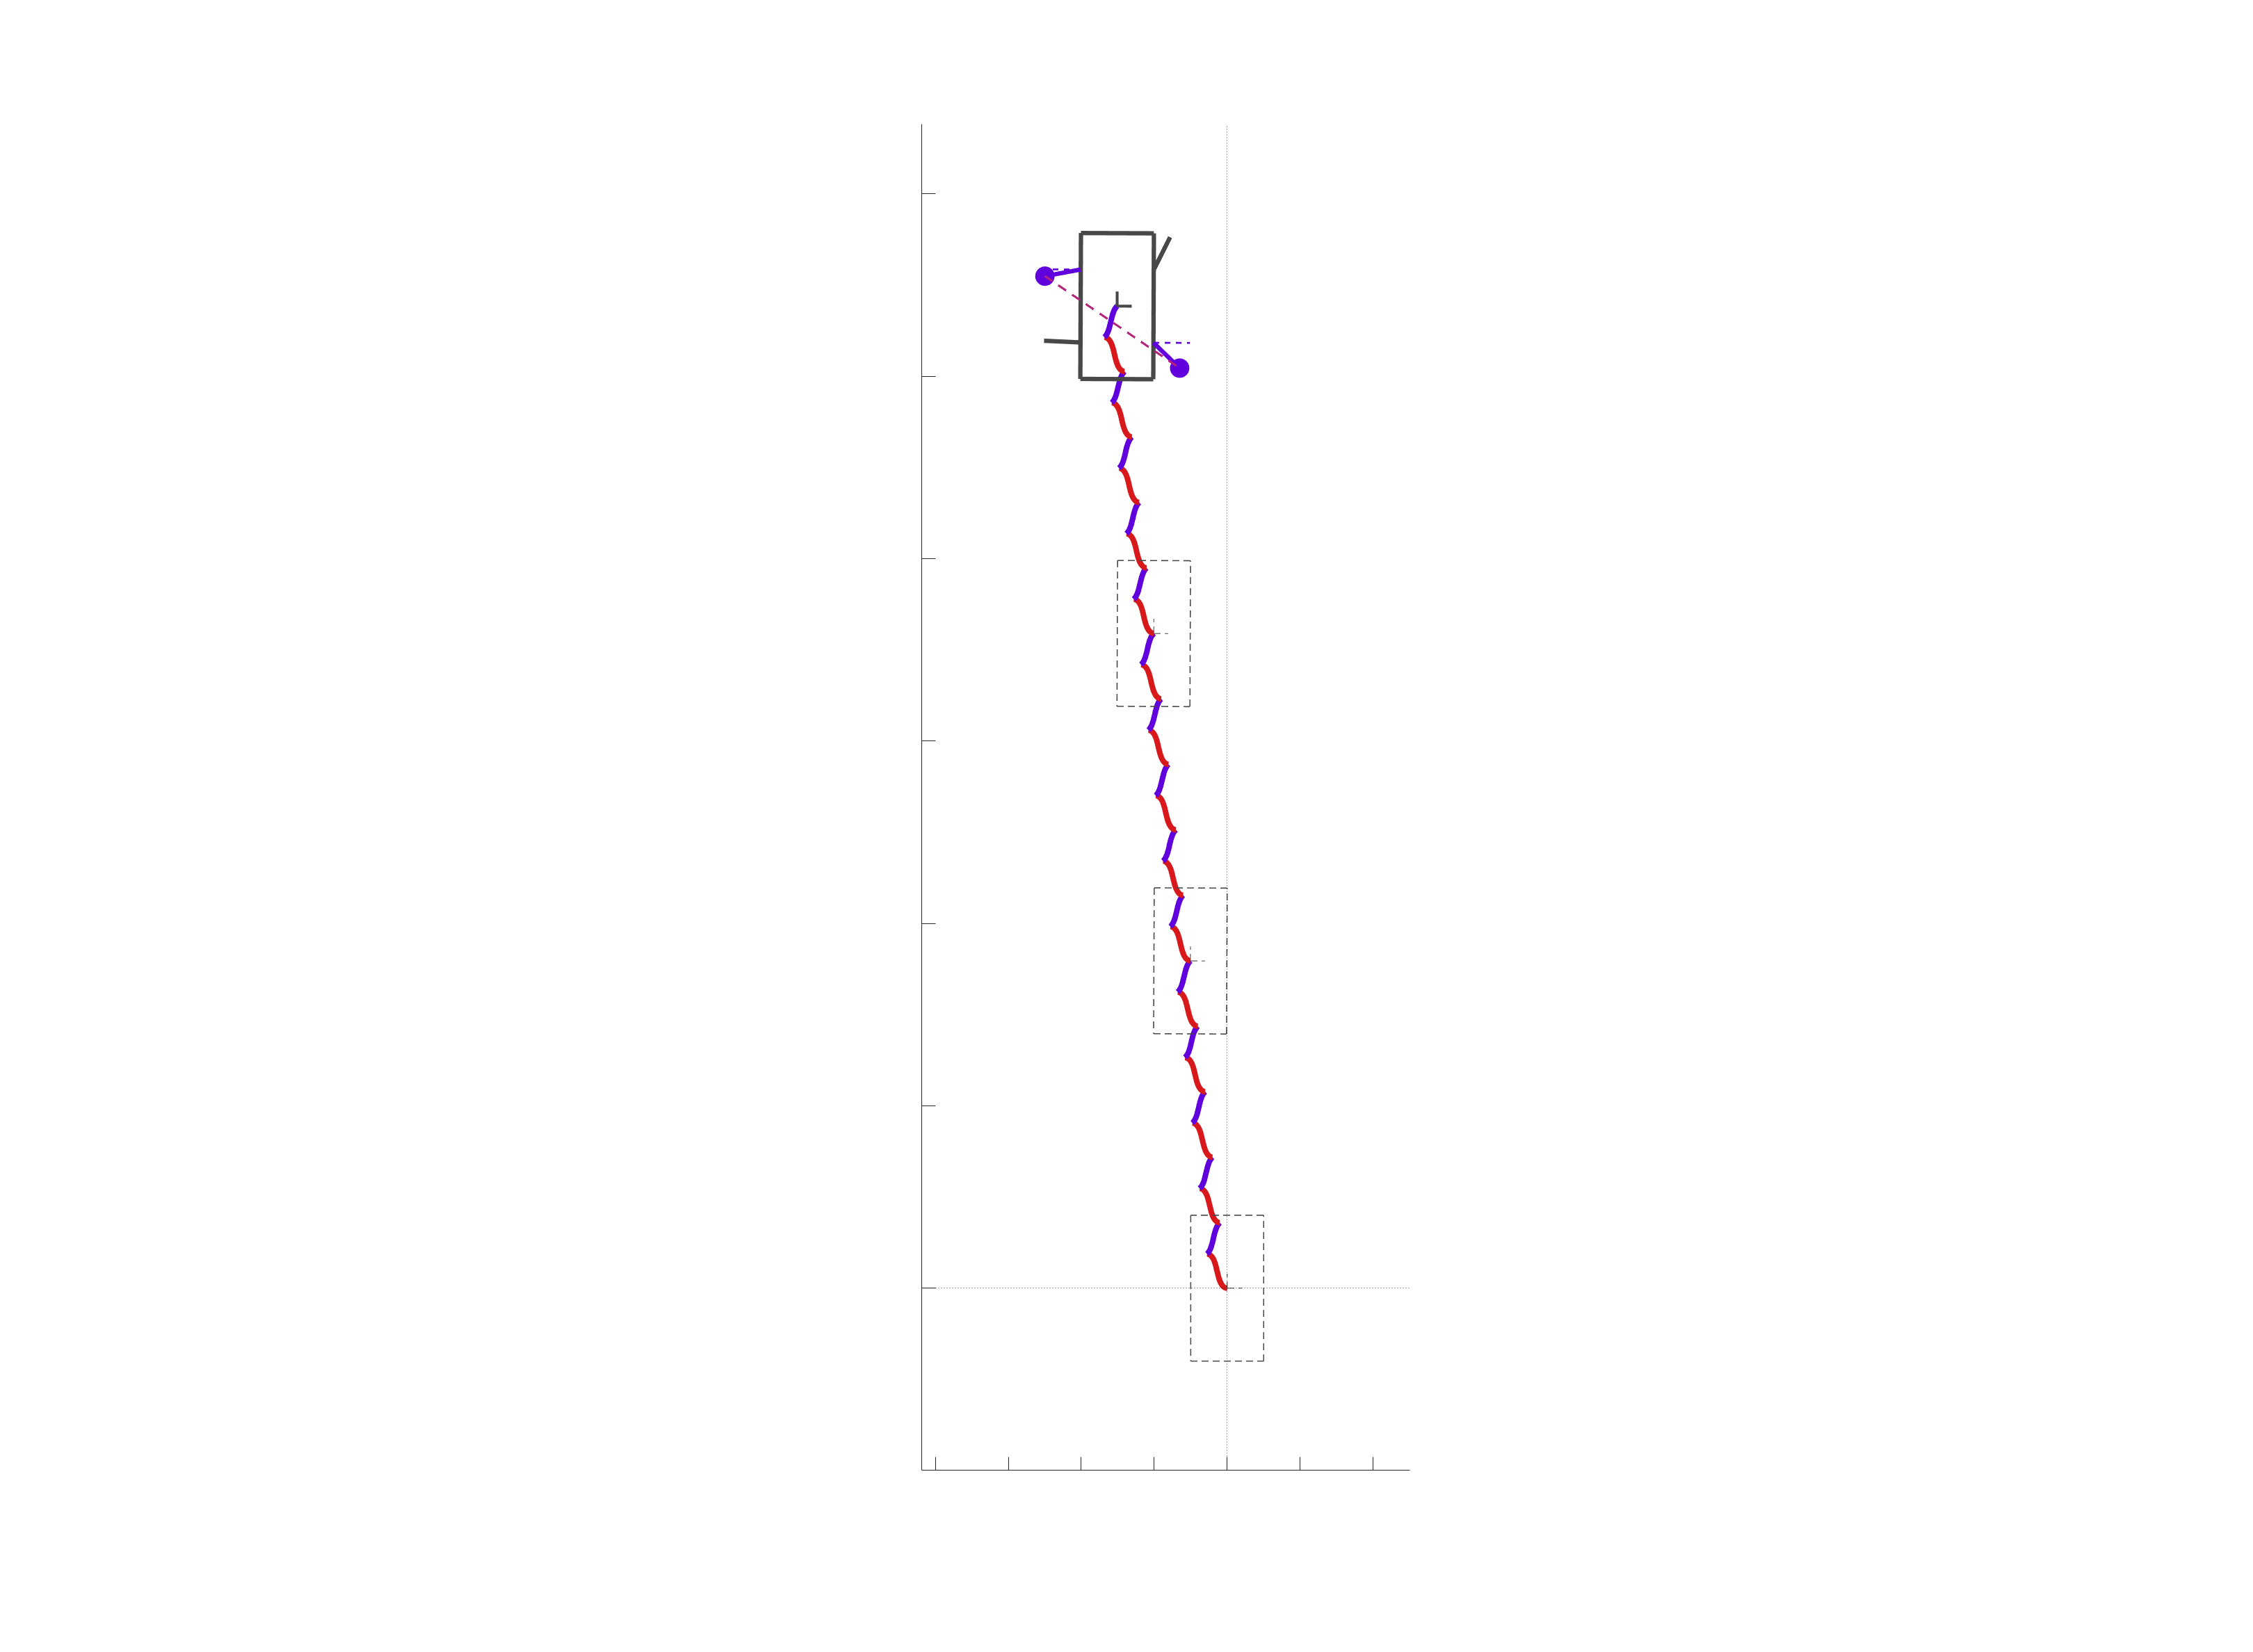

[pltTraj, traj] = stitchQuadSE2gaits({    ...
    {{S13_Gen_trial, S24_Gen_trial}, {S13_Gen_trial, S24_Gen_trial}, {S13_Gen_trial, S24_Gen_trial}},...
    {Gen_S13toS24_trial_data, Gen_S13toS24_trial_data, Gen_S13toS24_trial_data},...
    { {[1, 0.7]}, {[1, 0.7]}, {[1, 0.7]} },...
    { {5},      {5},      {5} }...
                                     });
m = 2160; n = 1800;
f = figure('units','pixels','position',[100 -200 m n],'Color','w');
set(gcf,'Visible','on');
hA = plot_SE2snapshot_QLvl2_Rigid_NoSlip( gca, pltTraj);

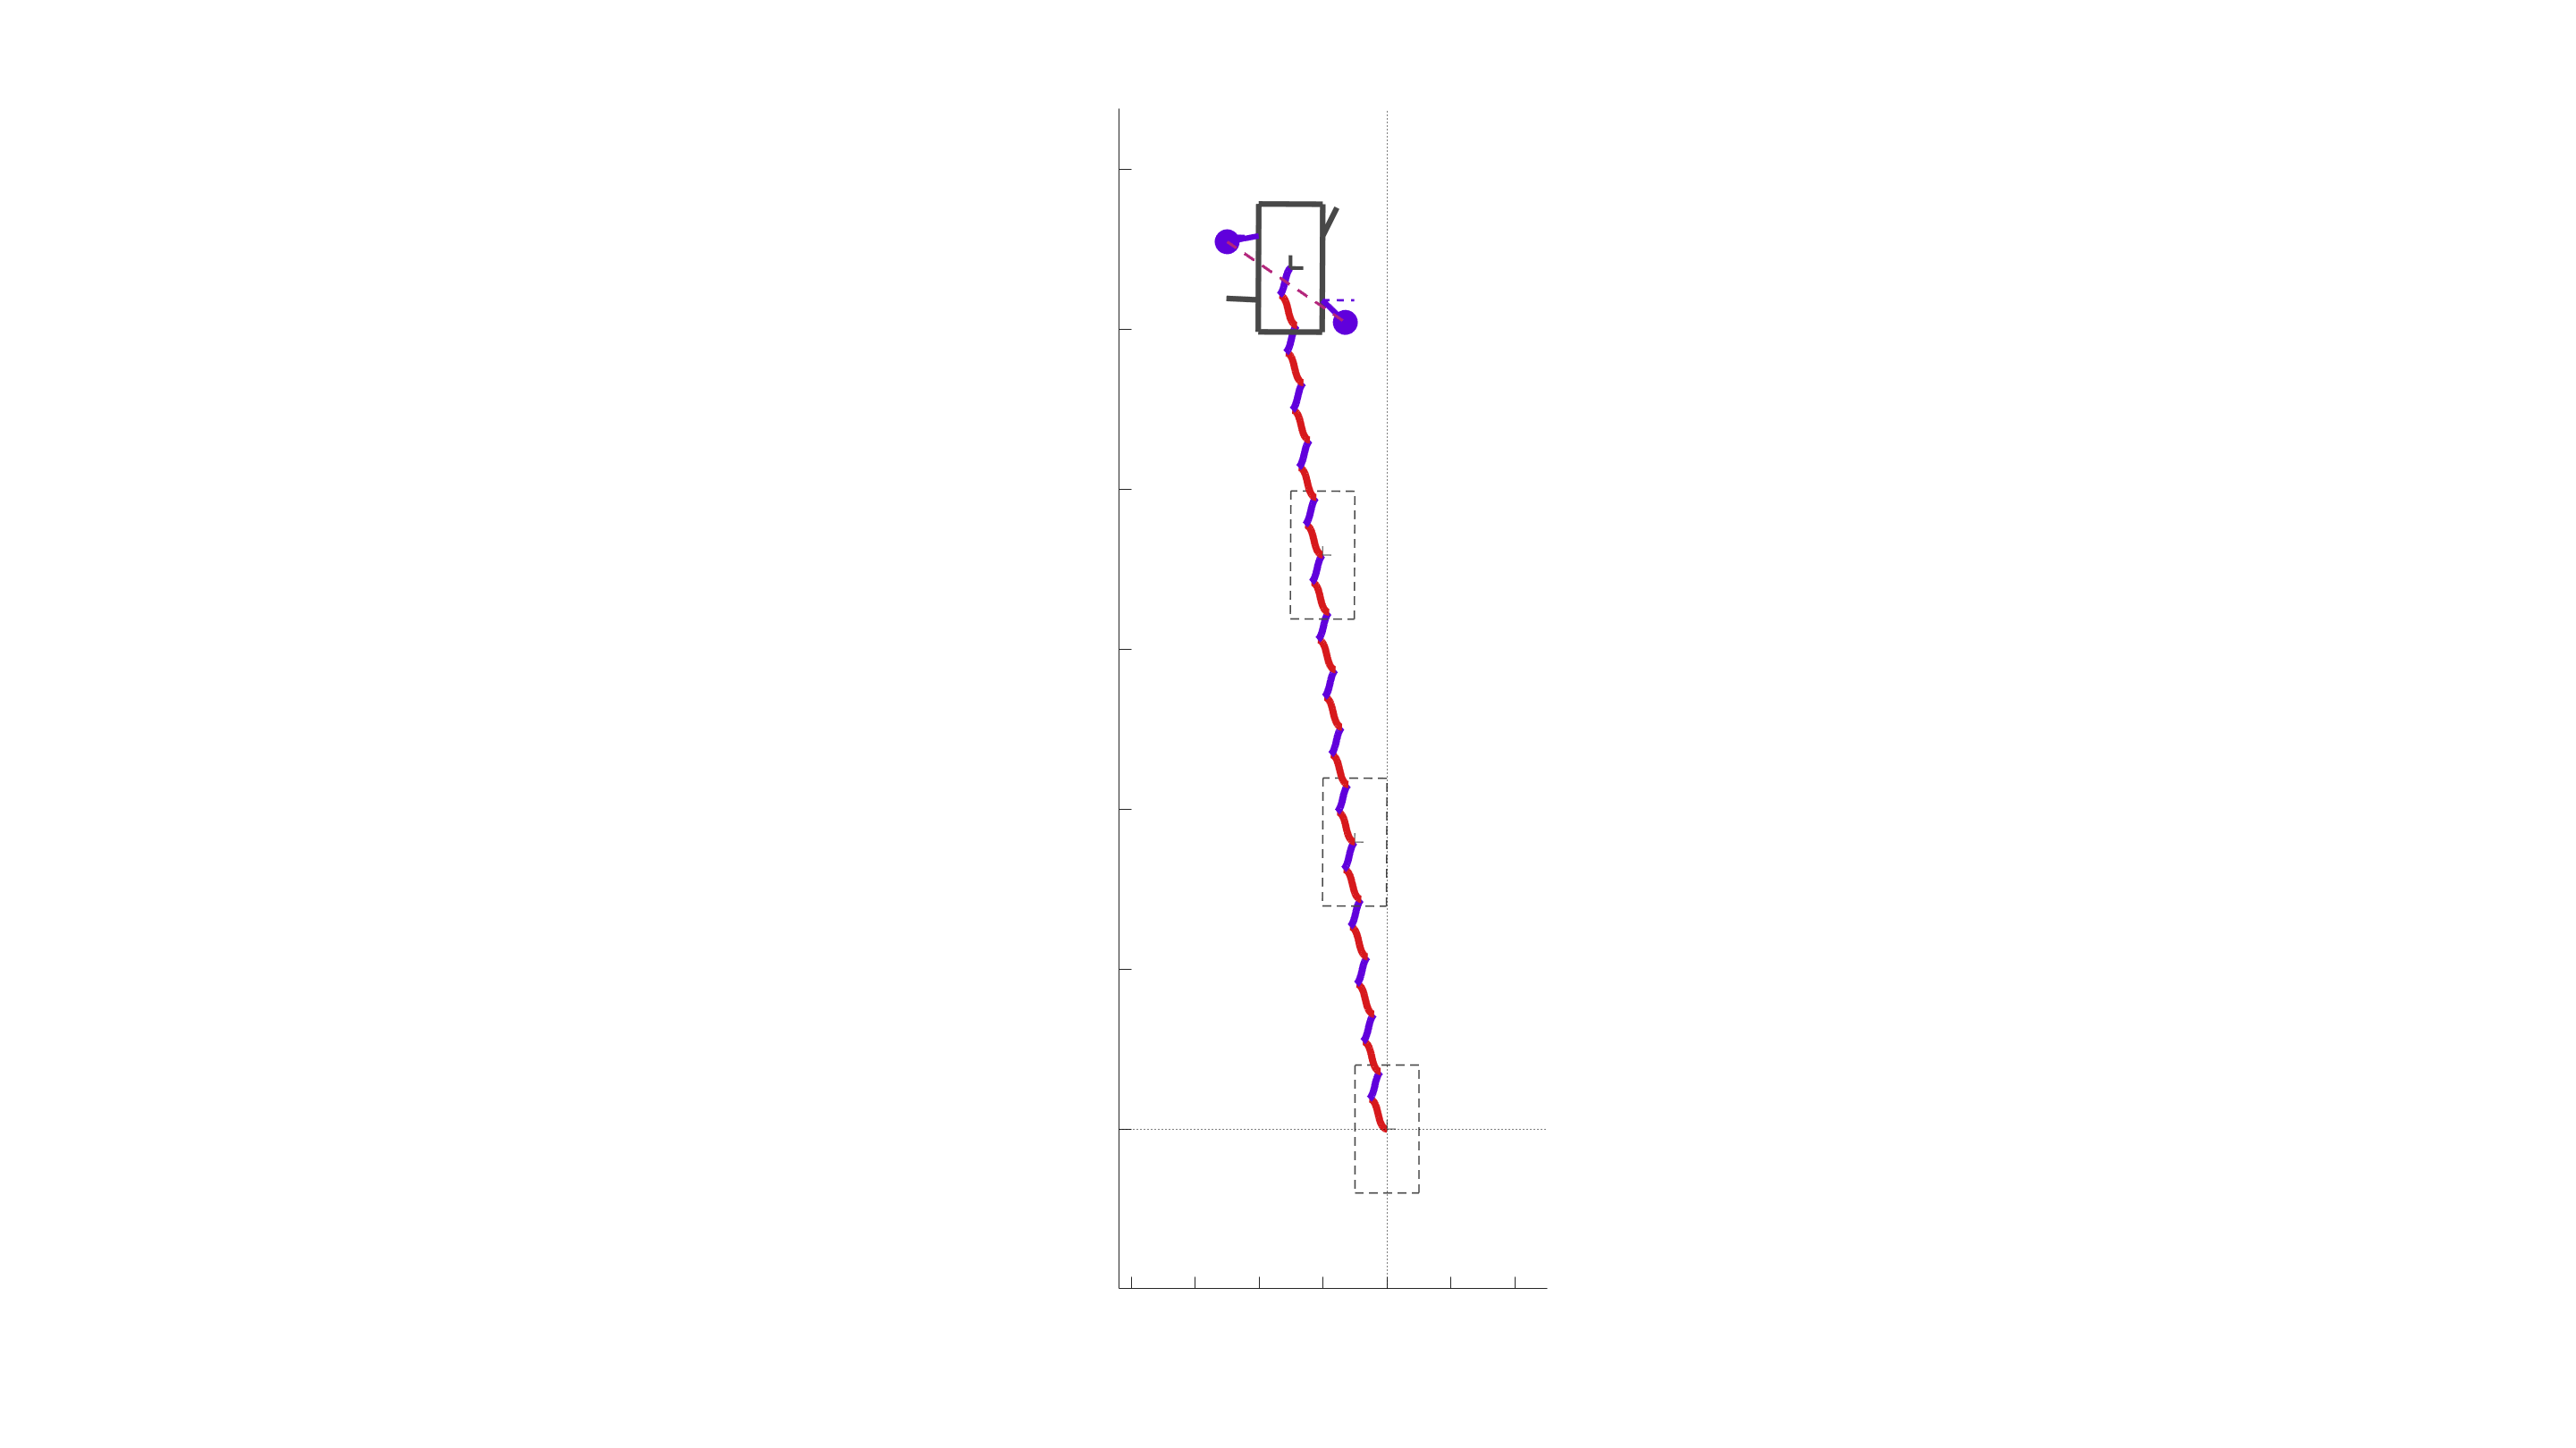

v = [];
save_addr = '';
save_name = 'trial_1_0p7_gait_1'; % replicates (trail13, trans24)
vid_time = 10;
v.fps = 60;
t = round(linspace(1, traj.dnum, v.fps*vid_time));
if t(end) < traj.dnum
    t(end+1) = traj.dnum;
end
vidF = true;
v.Name = [save_addr save_name];
if vidF
    video = VideoWriter([v.Name,'.mp4'],'MPEG-4');
    video.FrameRate = v.fps;
    video.Quality = 100;
    open(video);
end
f = figure('units','pixels','position',[0 0 1920 1080],'Color','w'); ax = gca;
set(f,'Visible','on');
for i = 1:numel(t)
    if i ~= 1
        for j = 1:numel(h)
            delete(h{j});
        end
    end
    switch i == 1
        case 0
            F = [t(i-1) t(i)];
        case 1
            F = [nan t(i)];
    end
    h = plot_SE2snapshot_QLvl2_Rigid_NoSlip(ax, pltTraj, F);
    drawnow;
    if vidF
        writeVideo(video,getframe(f));
    end
end

if vidF
    close(video);
end

addpath 'Data'\ 'Utility Functions'\;
load('Data\Gen_S13toS24.mat');
load('Data\Gen_S13_data.mat'); load('Data\Gen_S24_data.mat');

Replicate trial and trans as closely as possible-- (-1, 0.7).

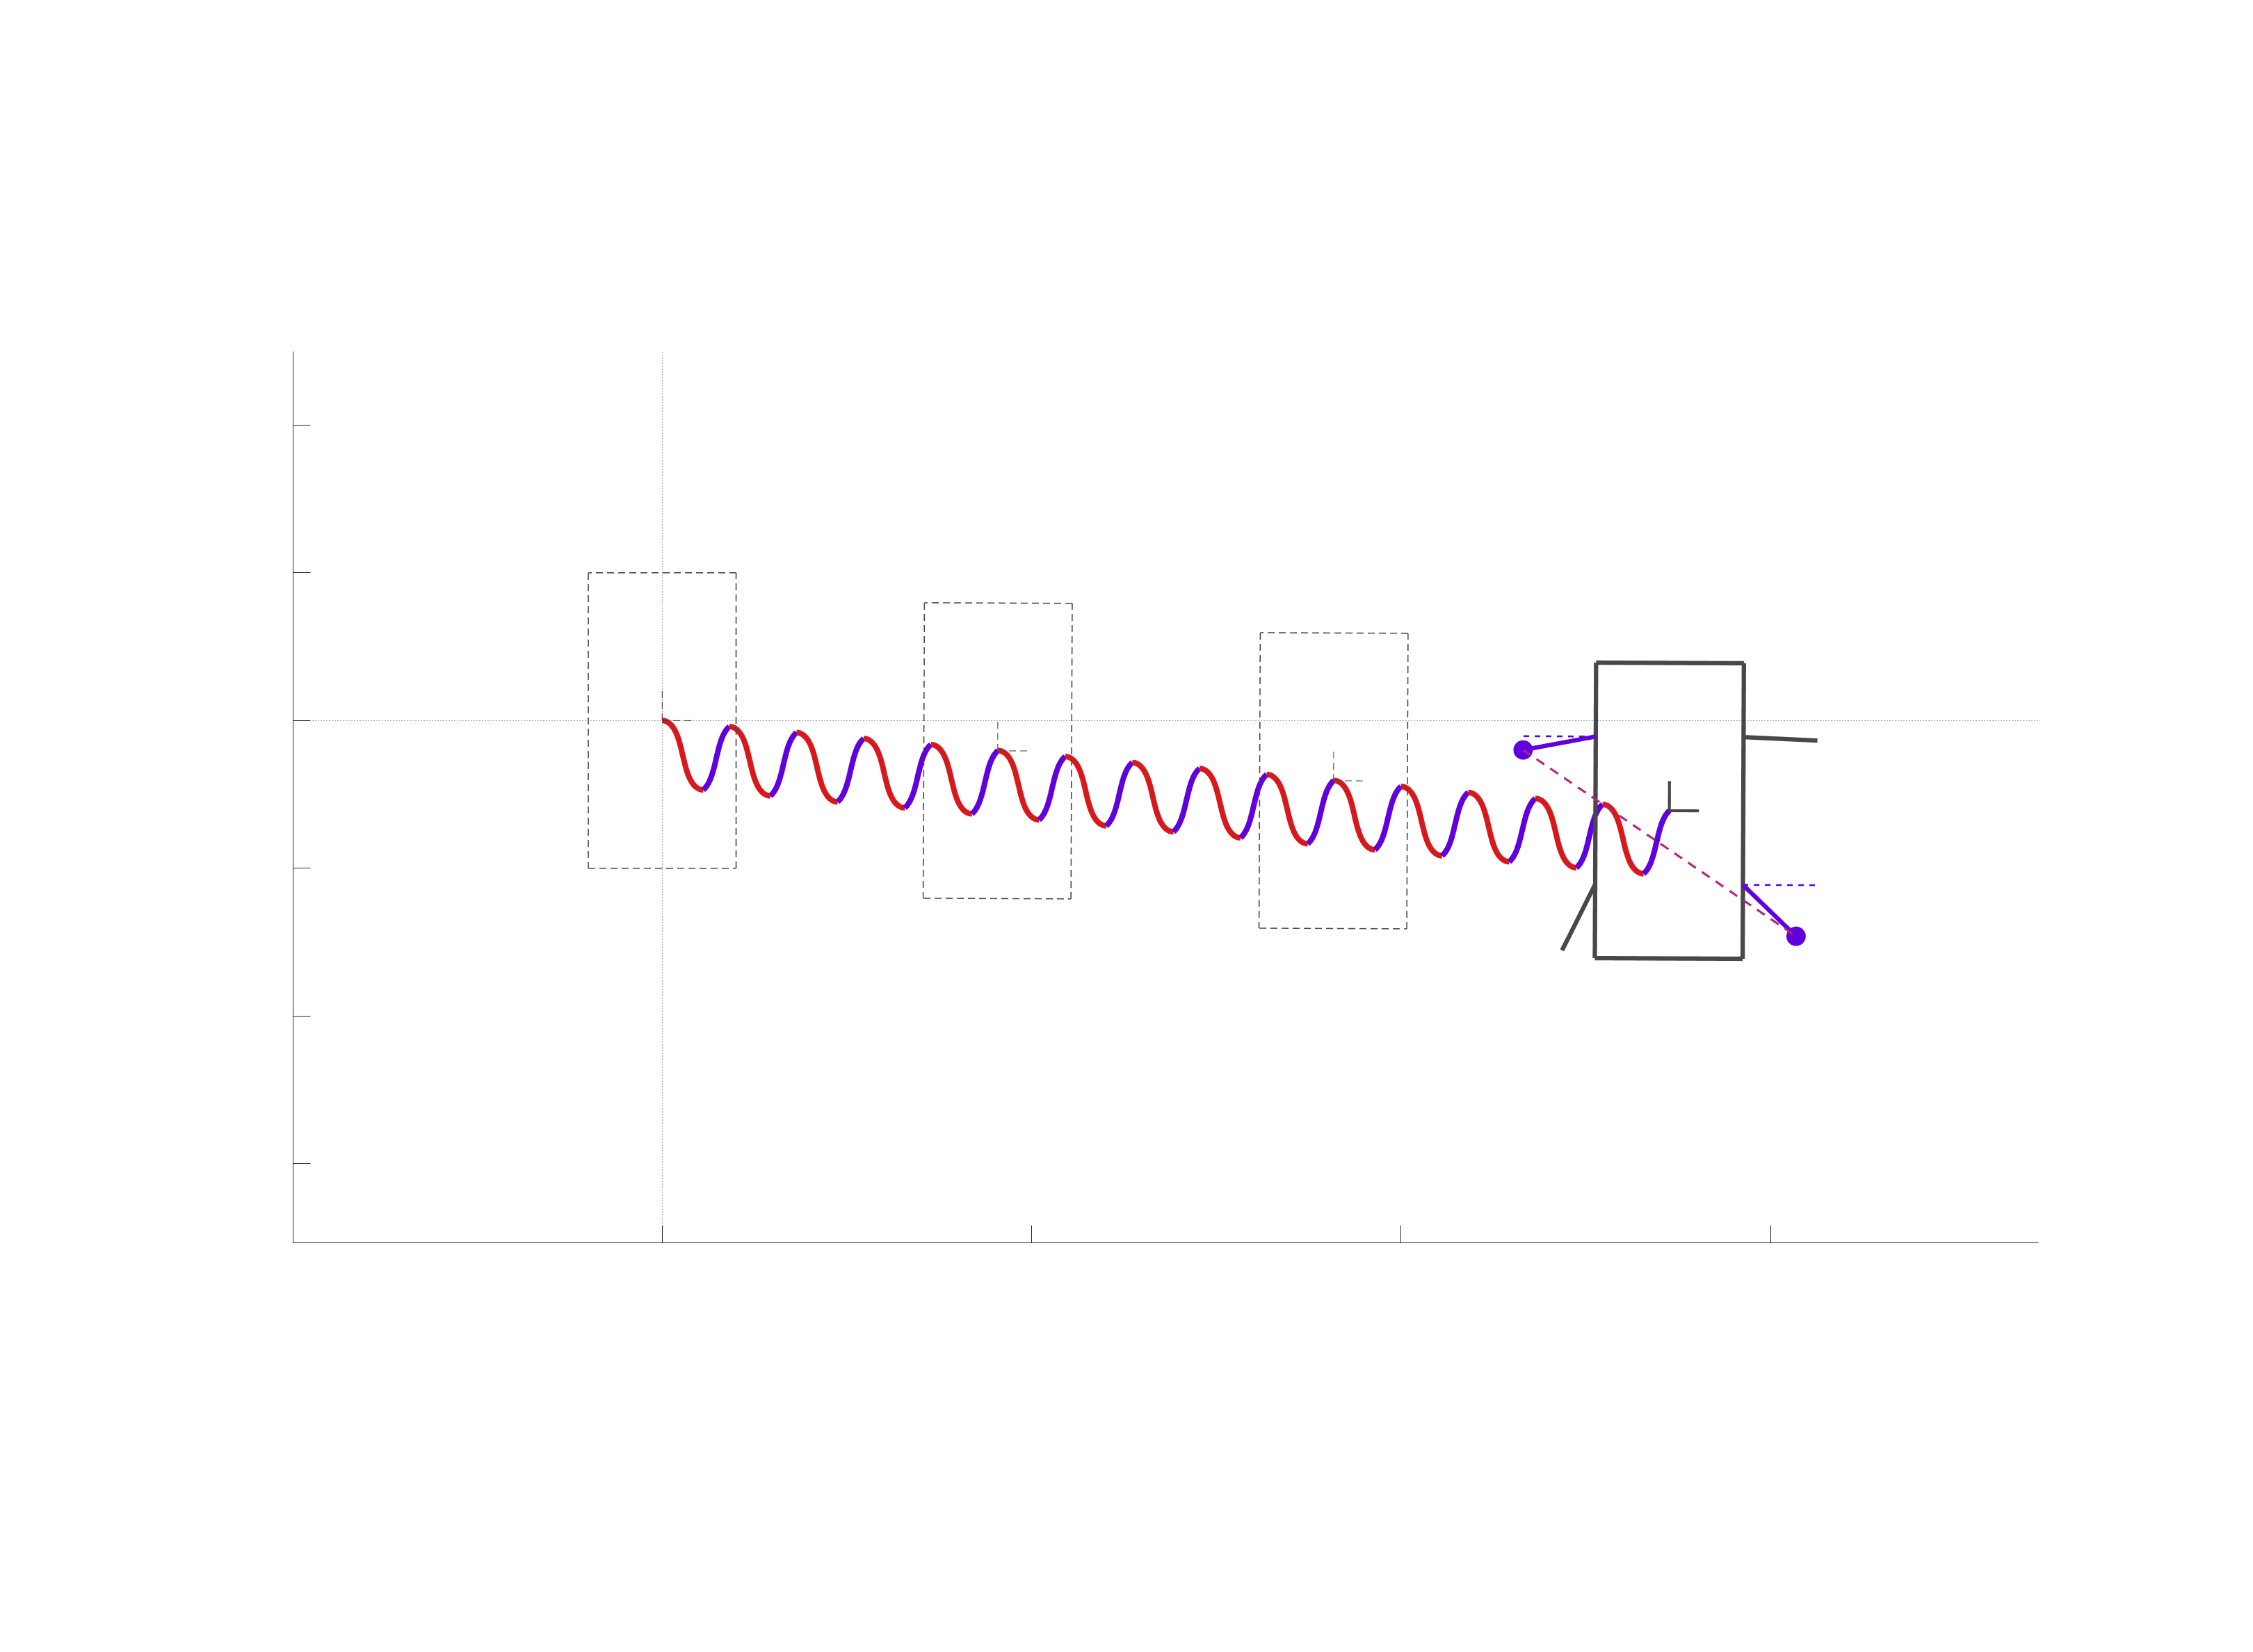

[pltTraj, traj] = stitchQuadSE2gaits({    ...
    {{S13_Gen_trial, S24_Gen_trial}, {S13_Gen_trial, S24_Gen_trial}, {S13_Gen_trial, S24_Gen_trial}},...
    {Gen_S13toS24_trial_data, Gen_S13toS24_trial_data, Gen_S13toS24_trial_data},...
    { {[-1, 0.7]}, {[-1, 0.7]}, {[-1, 0.7]} },...
    { {5},      {5},      {5} }...
                                     });
m = 2160; n = 1800;
f = figure('units','pixels','position',[100 -200 m n],'Color','w');
set(gcf,'Visible','on');
hA = plot_SE2snapshot_QLvl2_Rigid_NoSlip( gca, pltTraj);

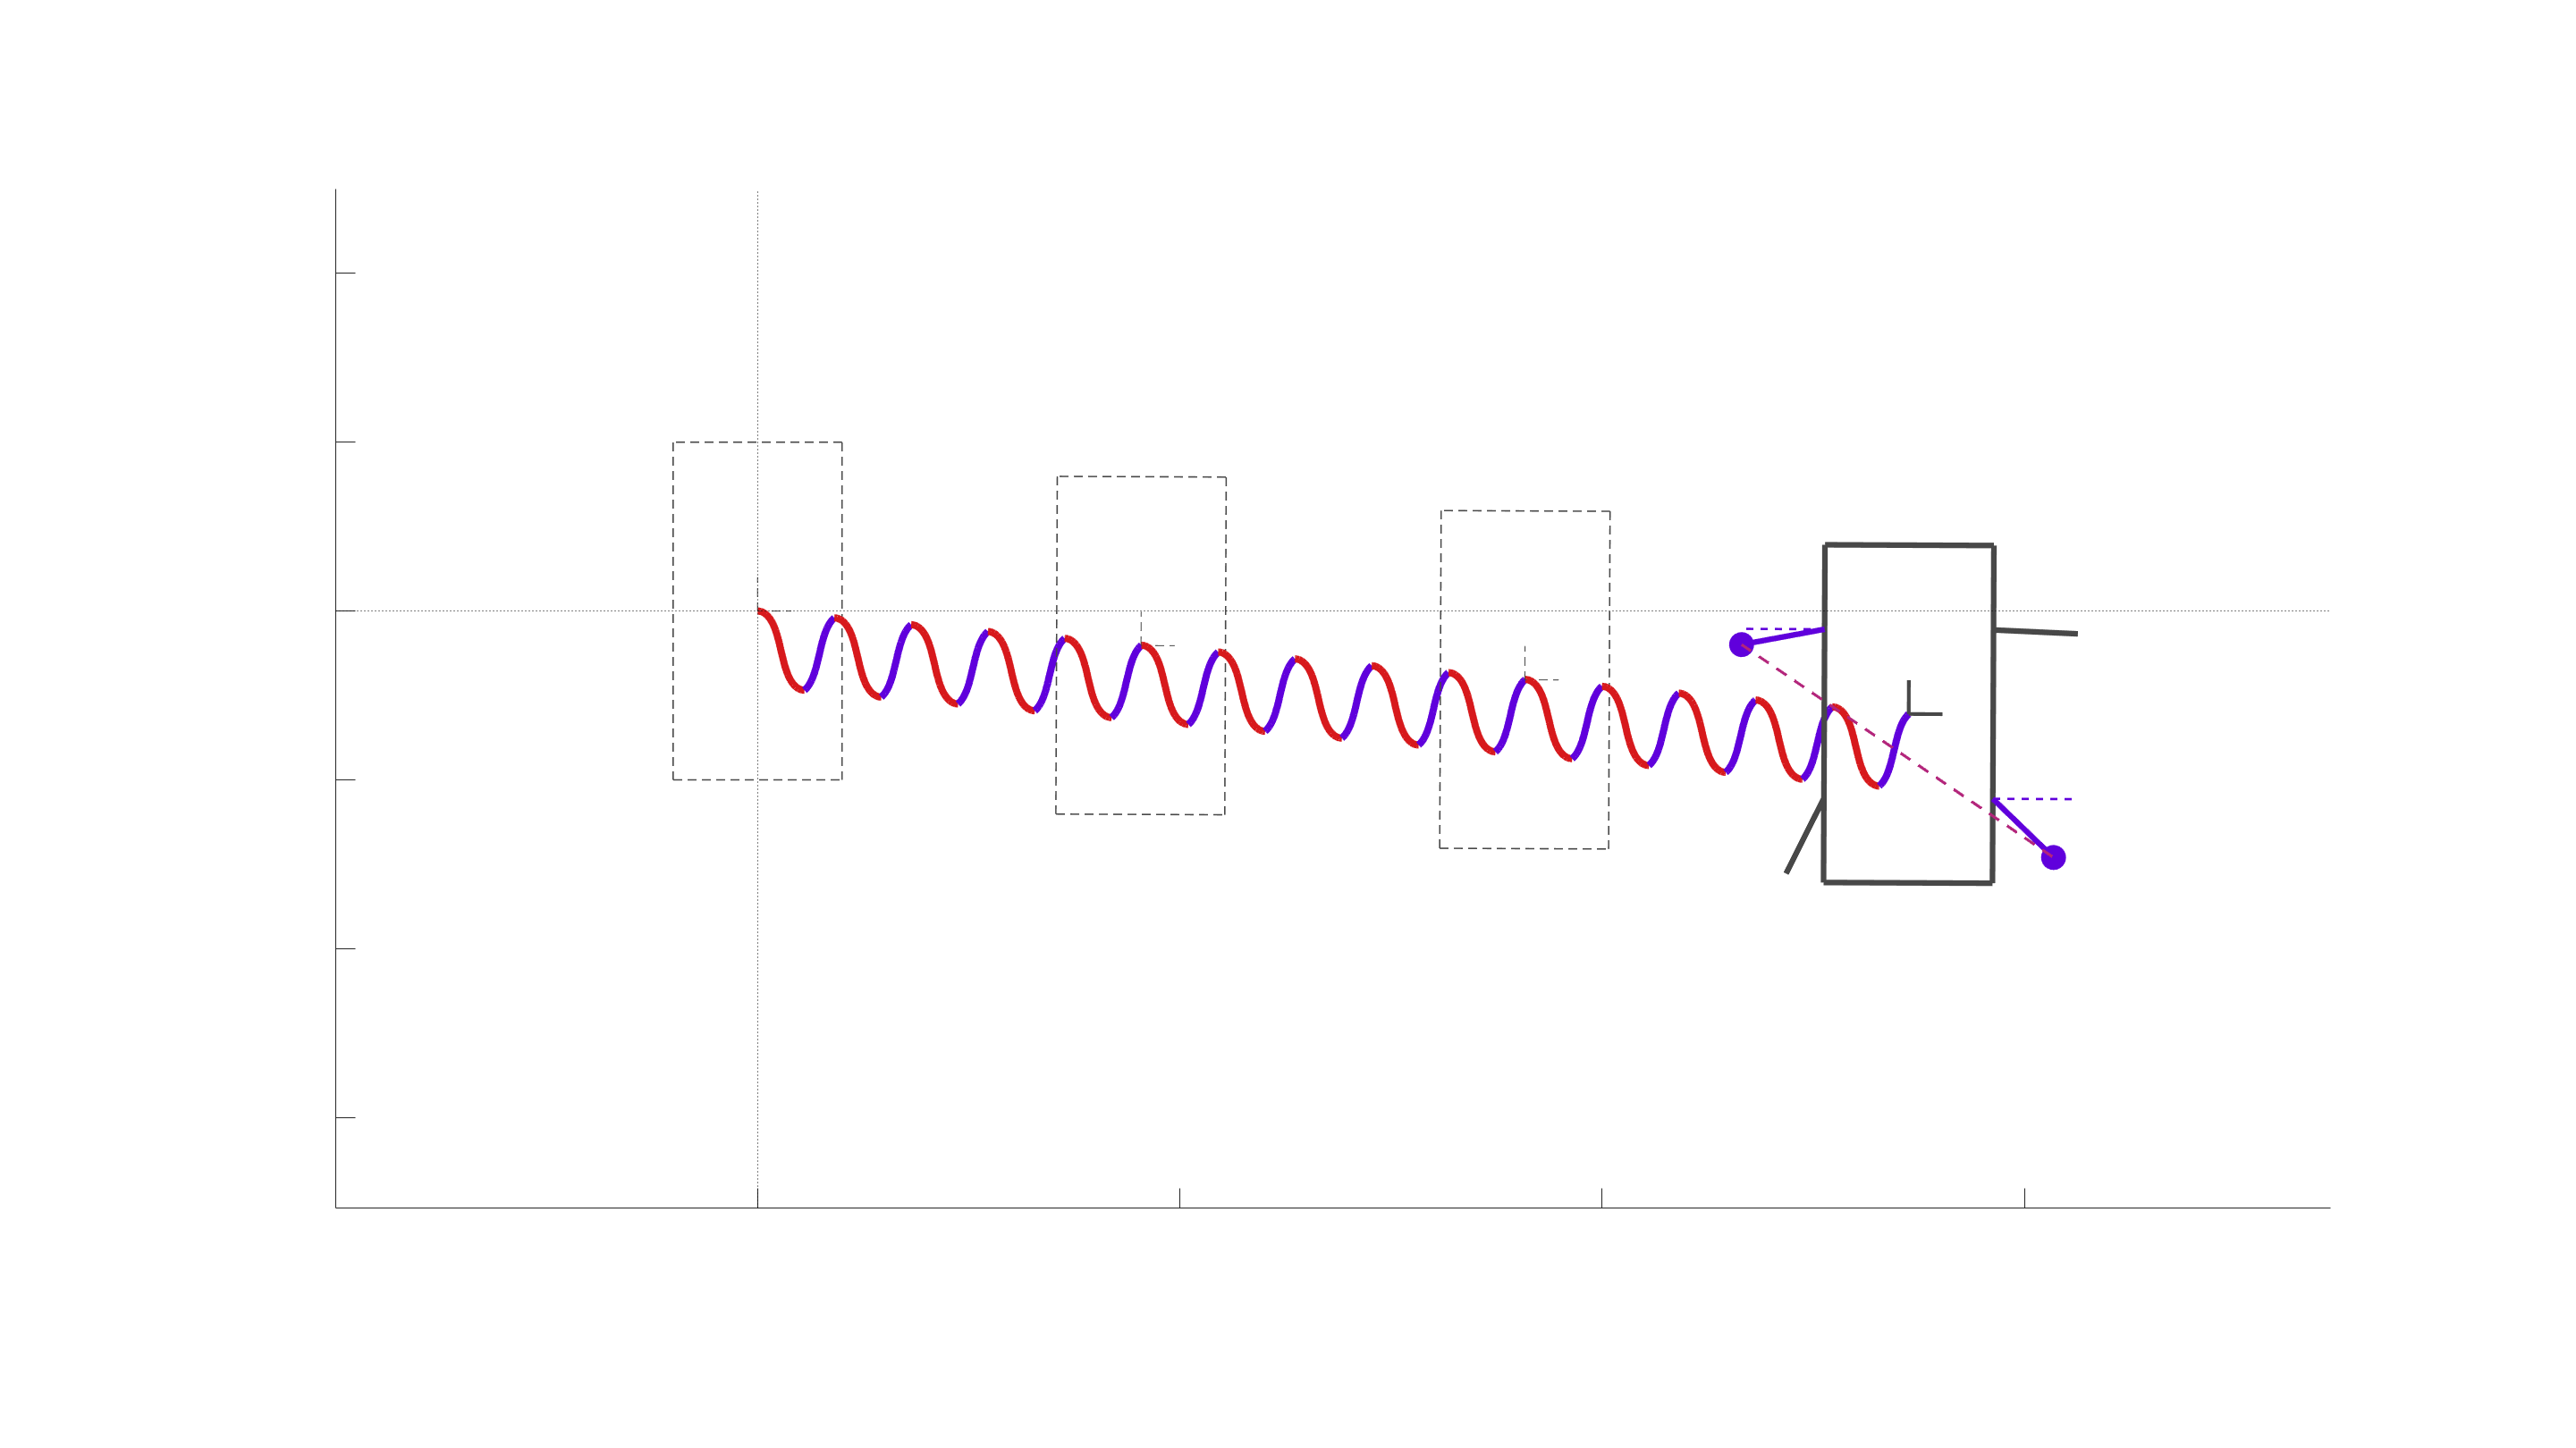

v = [];
save_addr = '';
save_name = 'trial_m1_0p7_gait_2'; % replicates (-trail13, trans24)
vid_time = 10;
v.fps = 60;
t = round(linspace(1, traj.dnum, v.fps*vid_time));
if t(end) < traj.dnum
    t(end+1) = traj.dnum;
end
vidF = true;
v.Name = [save_addr save_name];
if vidF
    video = VideoWriter([v.Name,'.mp4'],'MPEG-4');
    video.FrameRate = v.fps;
    video.Quality = 100;
    open(video);
end
f = figure('units','pixels','position',[0 0 1920 1080],'Color','w'); ax = gca;
set(f,'Visible','on');
for i = 1:numel(t)
    if i ~= 1
        for j = 1:numel(h)
            delete(h{j});
        end
    end
    switch i == 1
        case 0
            F = [t(i-1) t(i)];
        case 1
            F = [nan t(i)];
    end
    h = plot_SE2snapshot_QLvl2_Rigid_NoSlip(ax, pltTraj, F);
    drawnow;
    if vidF
        writeVideo(video,getframe(f));
    end
end

if vidF
    close(video);
end

addpath 'Data'\ 'Utility Functions'\;
load('Data\Gen_S13toS24.mat');
load('Data\Gen_S13_data.mat'); load('Data\Gen_S24_data.mat');

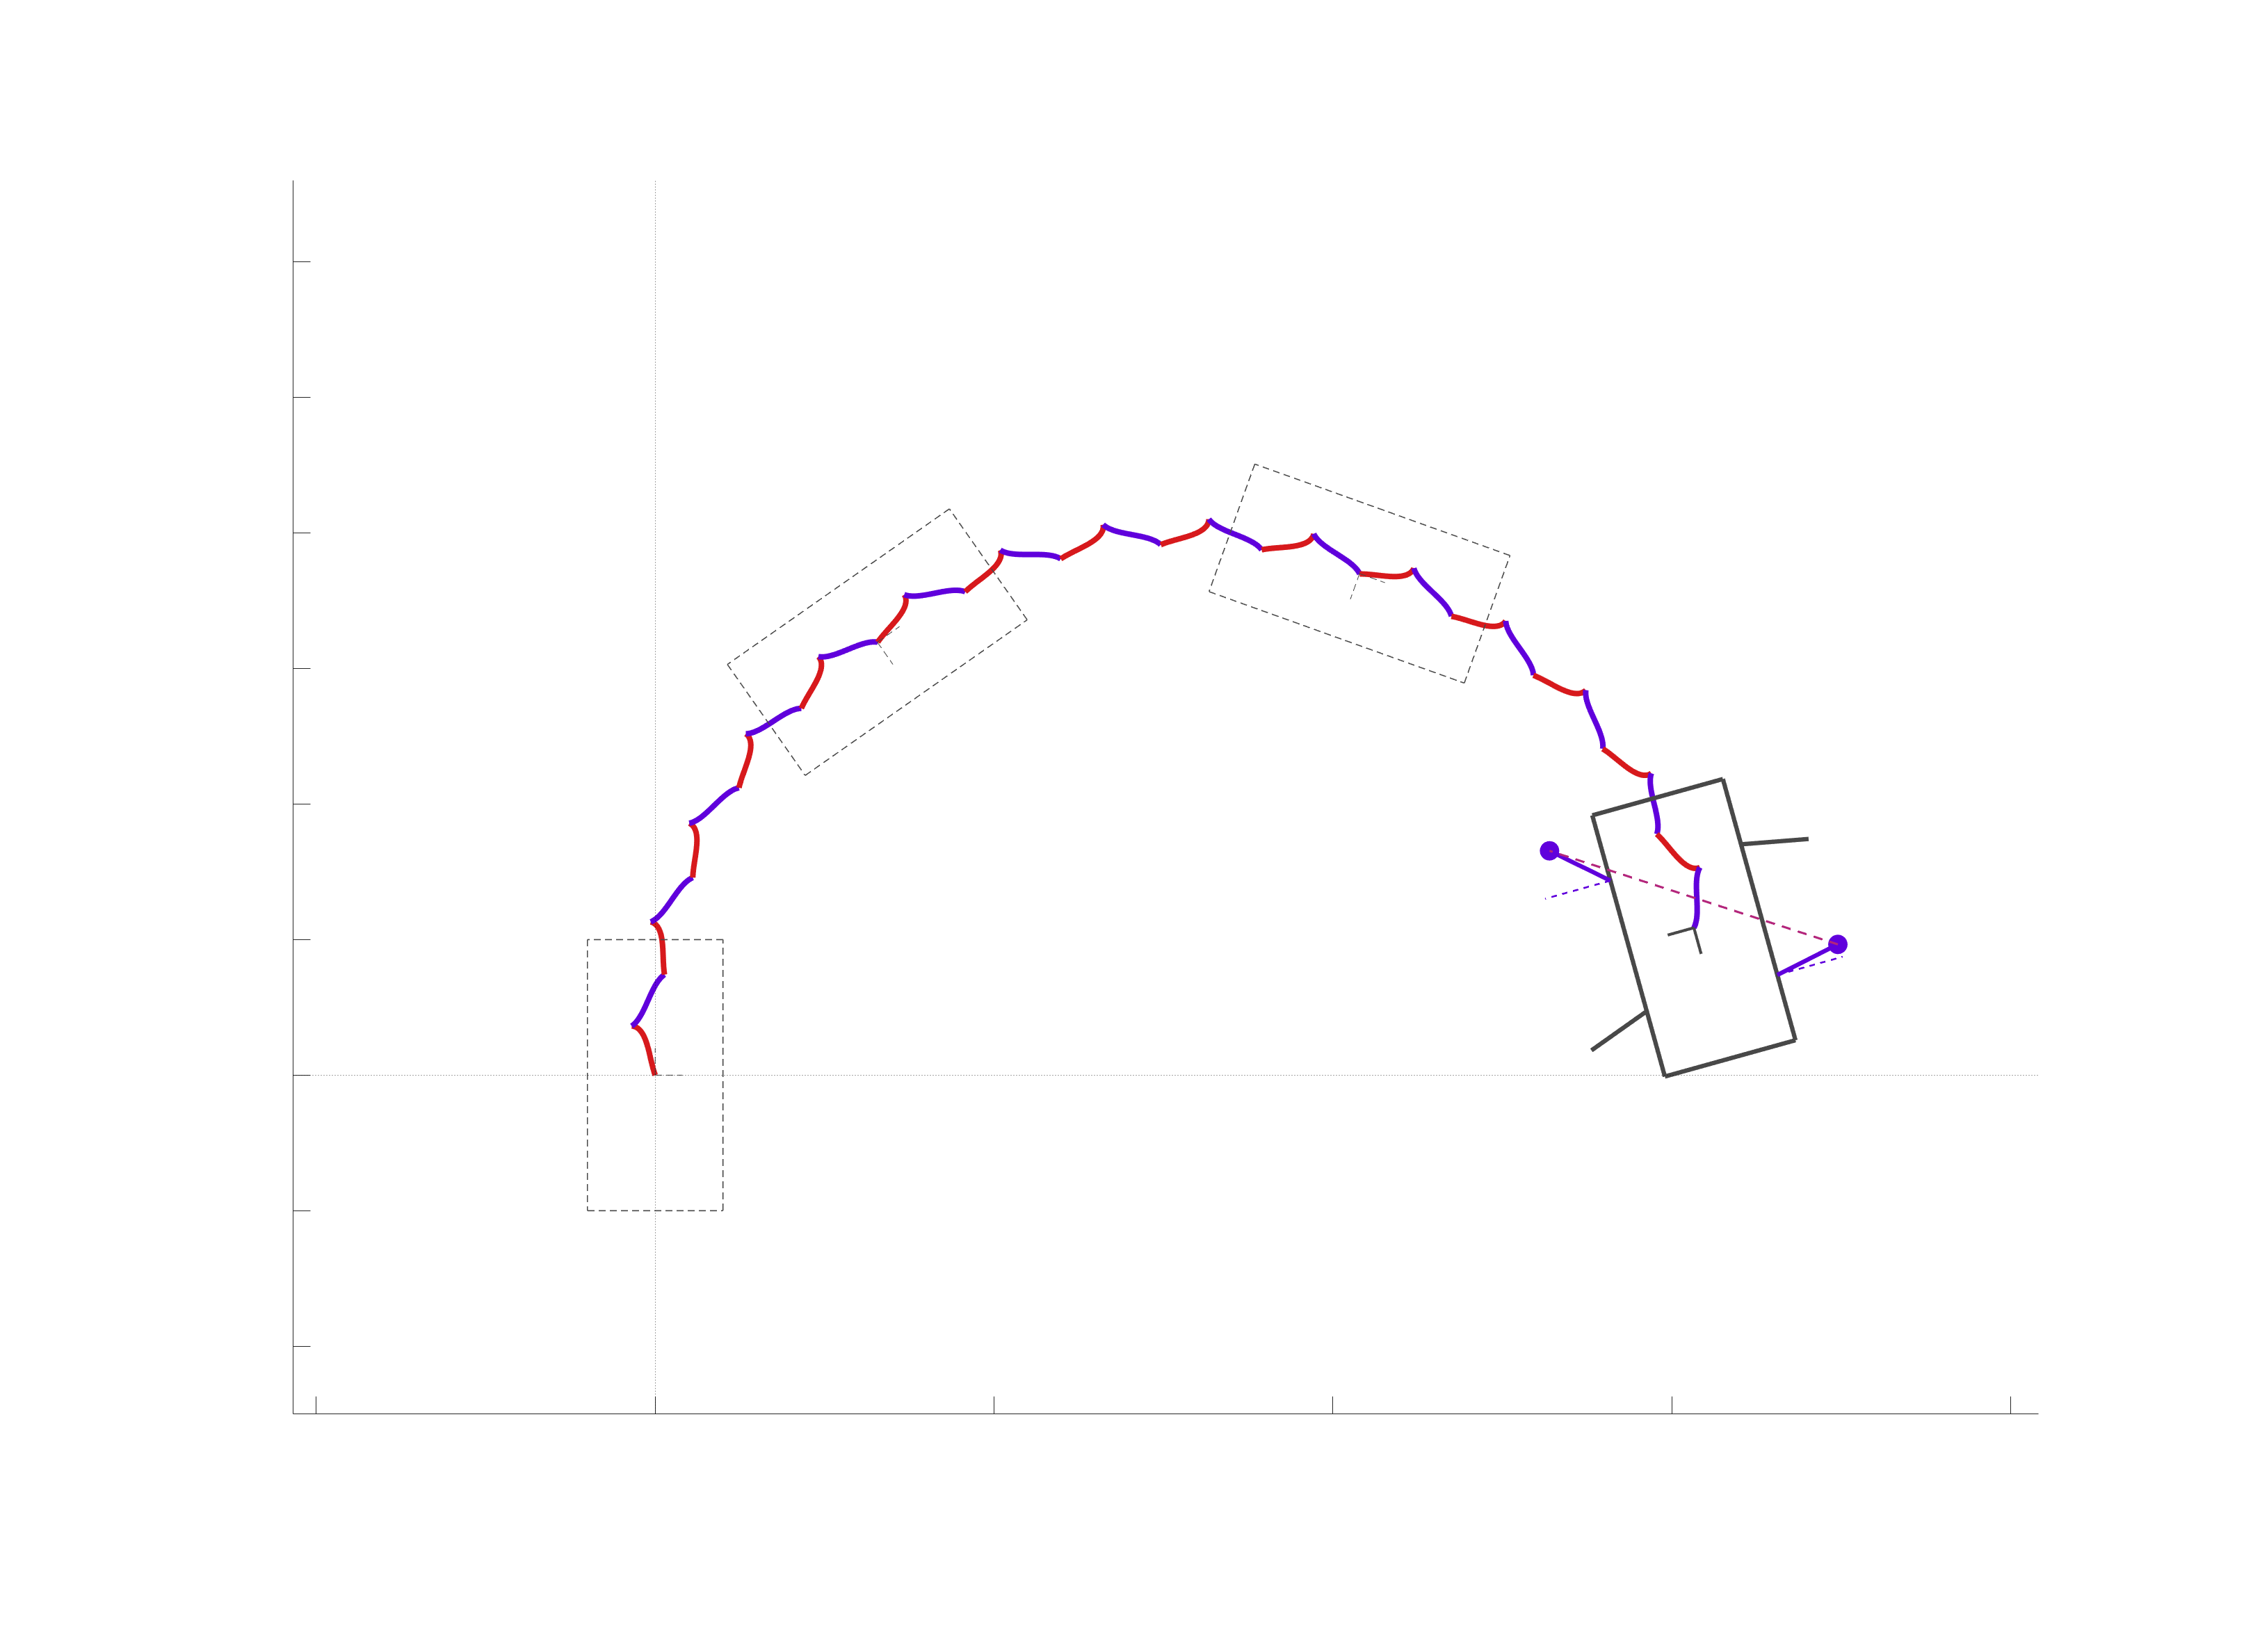

[pltTraj, traj] = stitchQuadSE2gaits({    ...
    {{S13_Gen_steer, S24_Gen_steer}, {S13_Gen_steer, S24_Gen_steer}, {S13_Gen_steer, S24_Gen_steer}},...
    {Gen_S13toS24_steer_1_data, Gen_S13toS24_steer_1_data, Gen_S13toS24_steer_1_data},...
    { {[-1, 0]}, {[-1, 0]}, {[-1, 0]} },... % slide13_gait_1-- { {[1, 0]}, {[1, 0]}, {[1, 0]} } % slide13_gait_2-- { {[-1, 0]}, {[-1, 0]}, {[-1, 0]} }
    { {5},      {5},      {5} }...
                                     });
m = 2160; n = 1800;
f = figure('units','pixels','position',[100 -200 m n],'Color','w');
set(gcf,'Visible','on');
hA = plot_SE2snapshot_QLvl2_Rigid_NoSlip( gca, pltTraj);

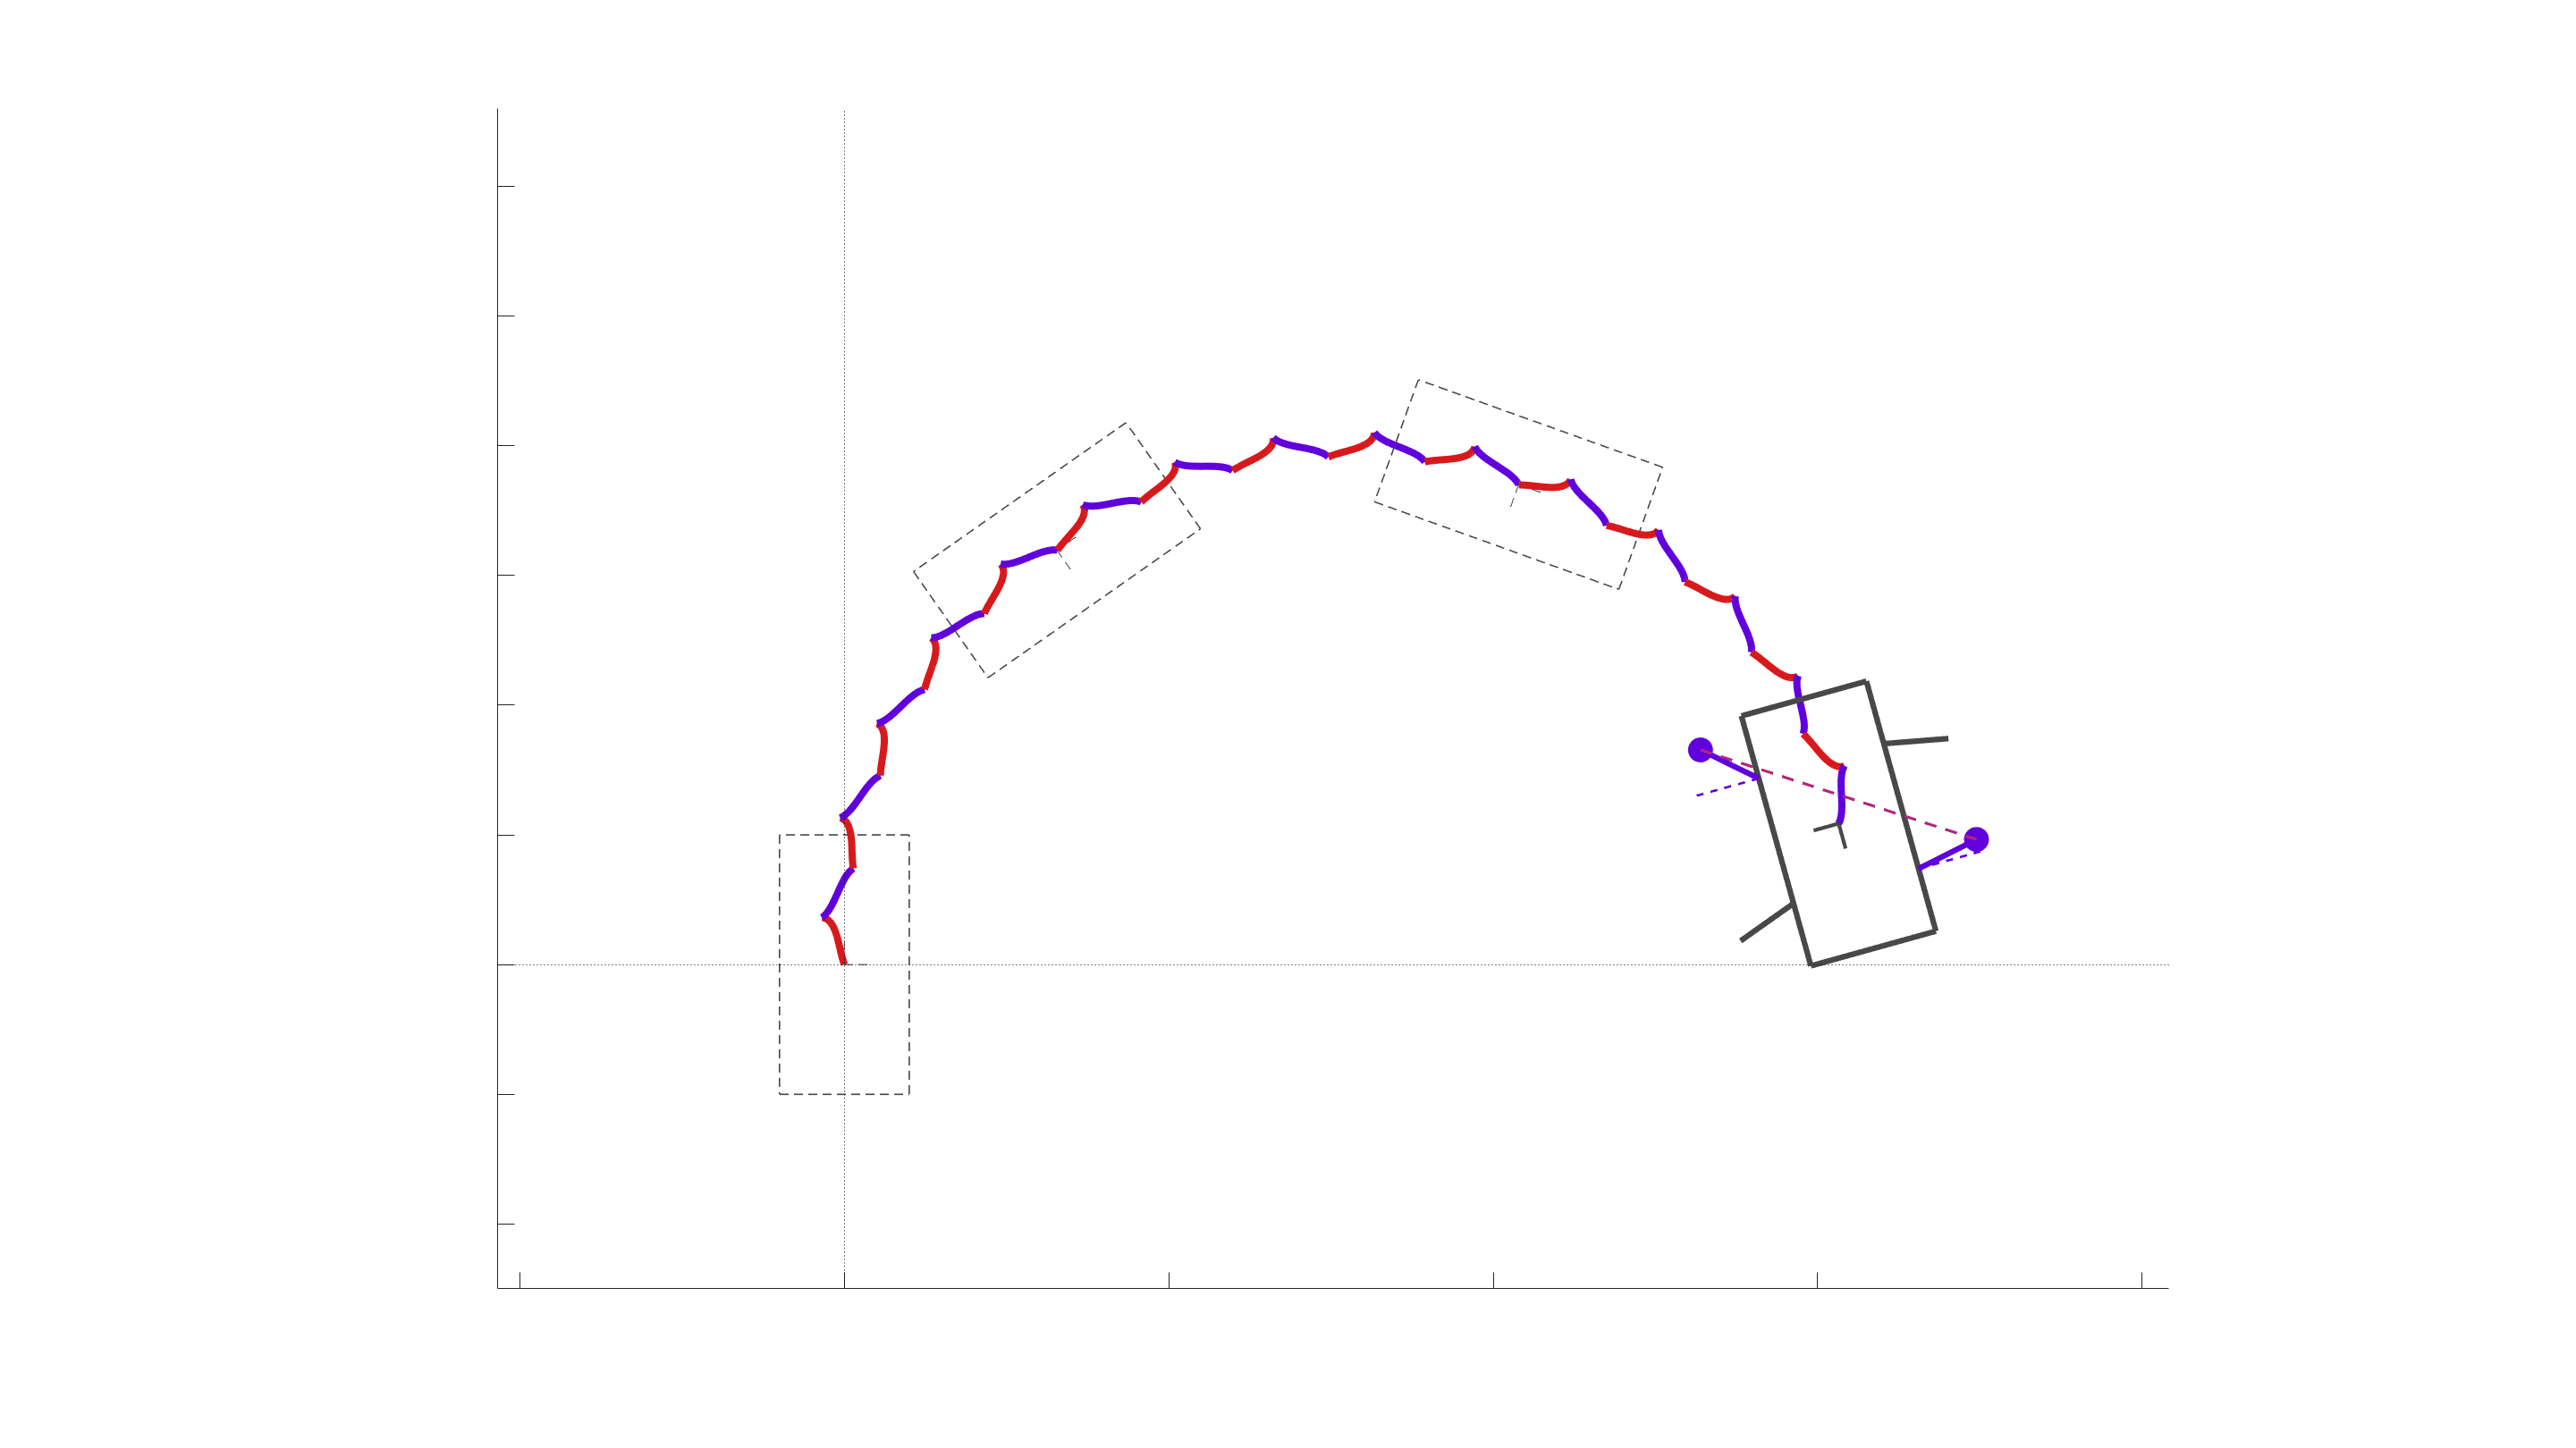

v = [];
save_addr = '';
save_name = 'slide13_gait_2'; % {slide13_gait_1, slide13_gait_2} % 1 is slid in the +ve dirn and 2 in the other dirn
vid_time = 10;
v.fps = 60;
t = round(linspace(1, traj.dnum, v.fps*vid_time));
if t(end) < traj.dnum
    t(end+1) = traj.dnum;
end
vidF = true;
v.Name = [save_addr save_name];
if vidF
    video = VideoWriter([v.Name,'.mp4'],'MPEG-4');
    video.FrameRate = v.fps;
    video.Quality = 100;
    open(video);
end
f = figure('units','pixels','position',[0 0 1920 1080],'Color','w'); ax = gca;
set(f,'Visible','on');
for i = 1:numel(t)
    if i ~= 1
        for j = 1:numel(h)
            delete(h{j});
        end
    end
    switch i == 1
        case 0
            F = [t(i-1) t(i)];
        case 1
            F = [nan t(i)];
    end
    h = plot_SE2snapshot_QLvl2_Rigid_NoSlip(ax, pltTraj, F);
    drawnow;
    if vidF
        writeVideo(video,getframe(f));
    end
end

if vidF
    close(video);
end

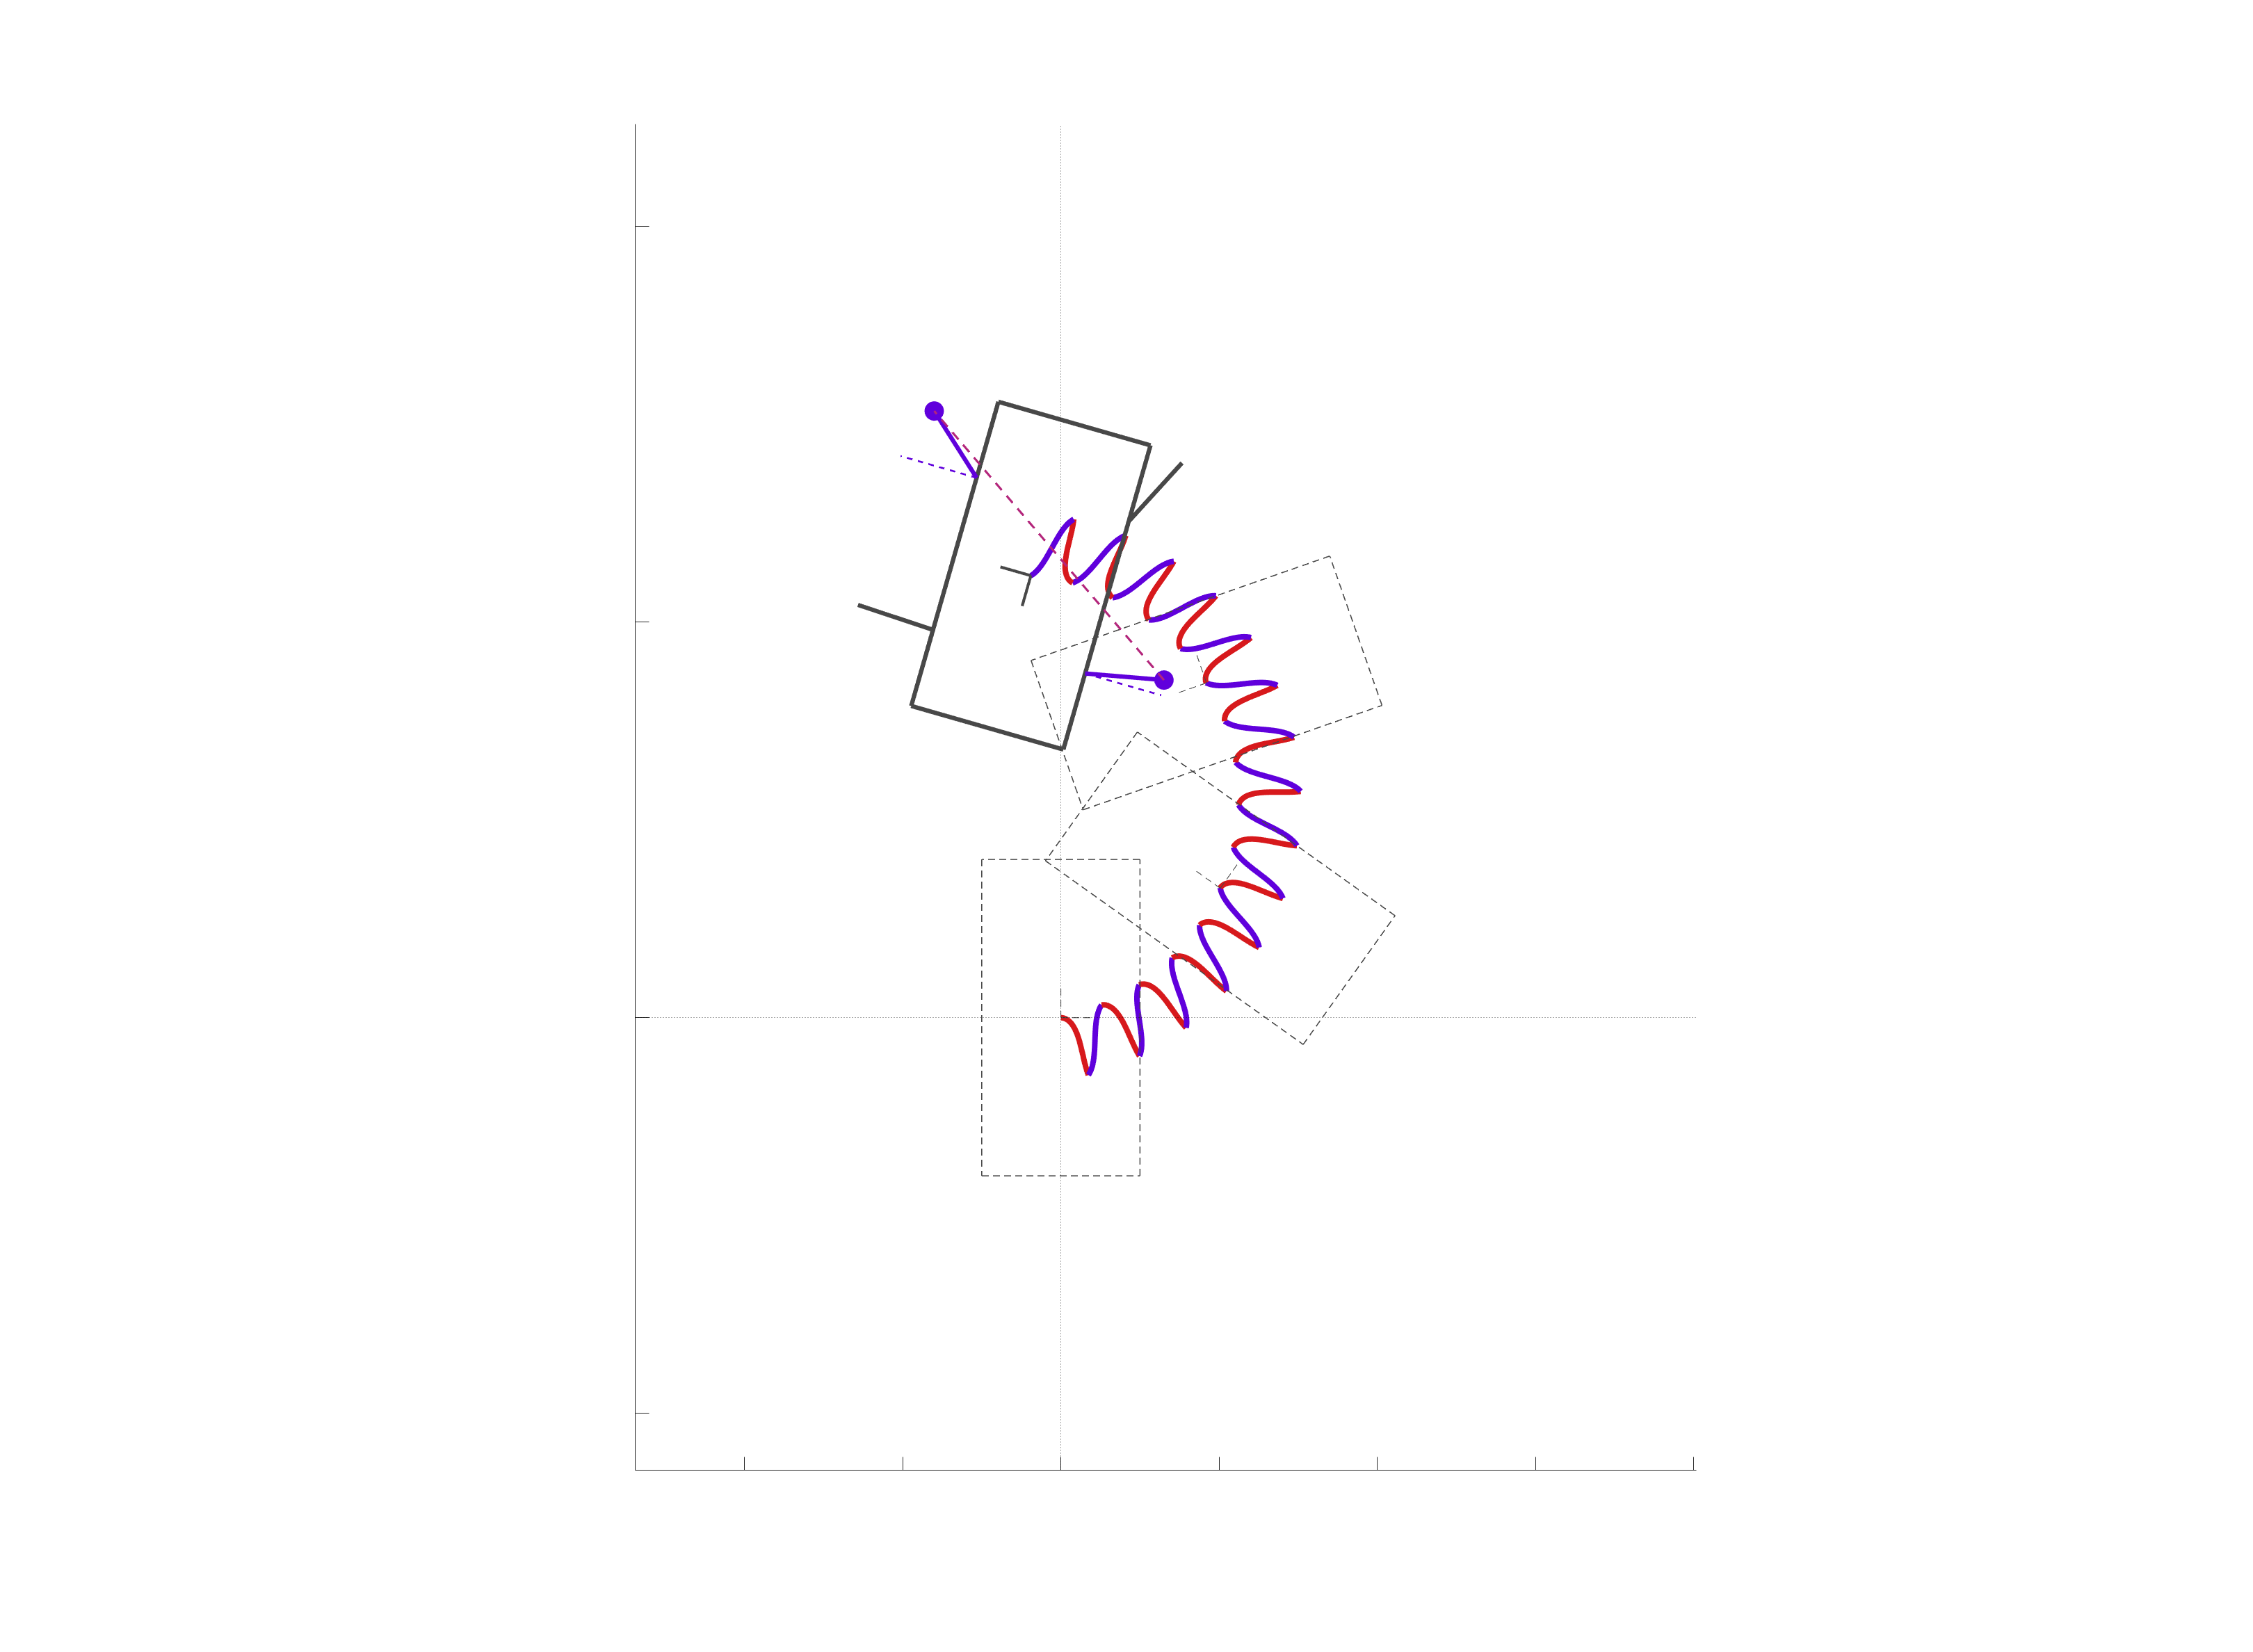

[pltTraj, traj] = stitchQuadSE2gaits({    ...
    {{S13_Gen_steer_lat, S24_Gen_steer}, {S13_Gen_steer_lat, S24_Gen_steer}, {S13_Gen_steer_lat, S24_Gen_steer}},...
    {Gen_S13toS24_steer_5_data, Gen_S13toS24_steer_5_data, Gen_S13toS24_steer_5_data},...
    { {[1, 0]}, {[1, 0]}, {[1, 0]} },... % slide13_lat_gait_1-- { {[1, 0]}, {[1, 0]}, {[1, 0]} } % slide13_lat_gait_2-- { {[-1, 0]}, {[-1, 0]}, {[-1, 0]} }
    { {5},      {5},      {5} }...
                                     });
m = 2160; n = 1800;
f = figure('units','pixels','position',[100 -200 m n],'Color','w');
set(gcf,'Visible','on');
hA = plot_SE2snapshot_QLvl2_Rigid_NoSlip( gca, pltTraj);

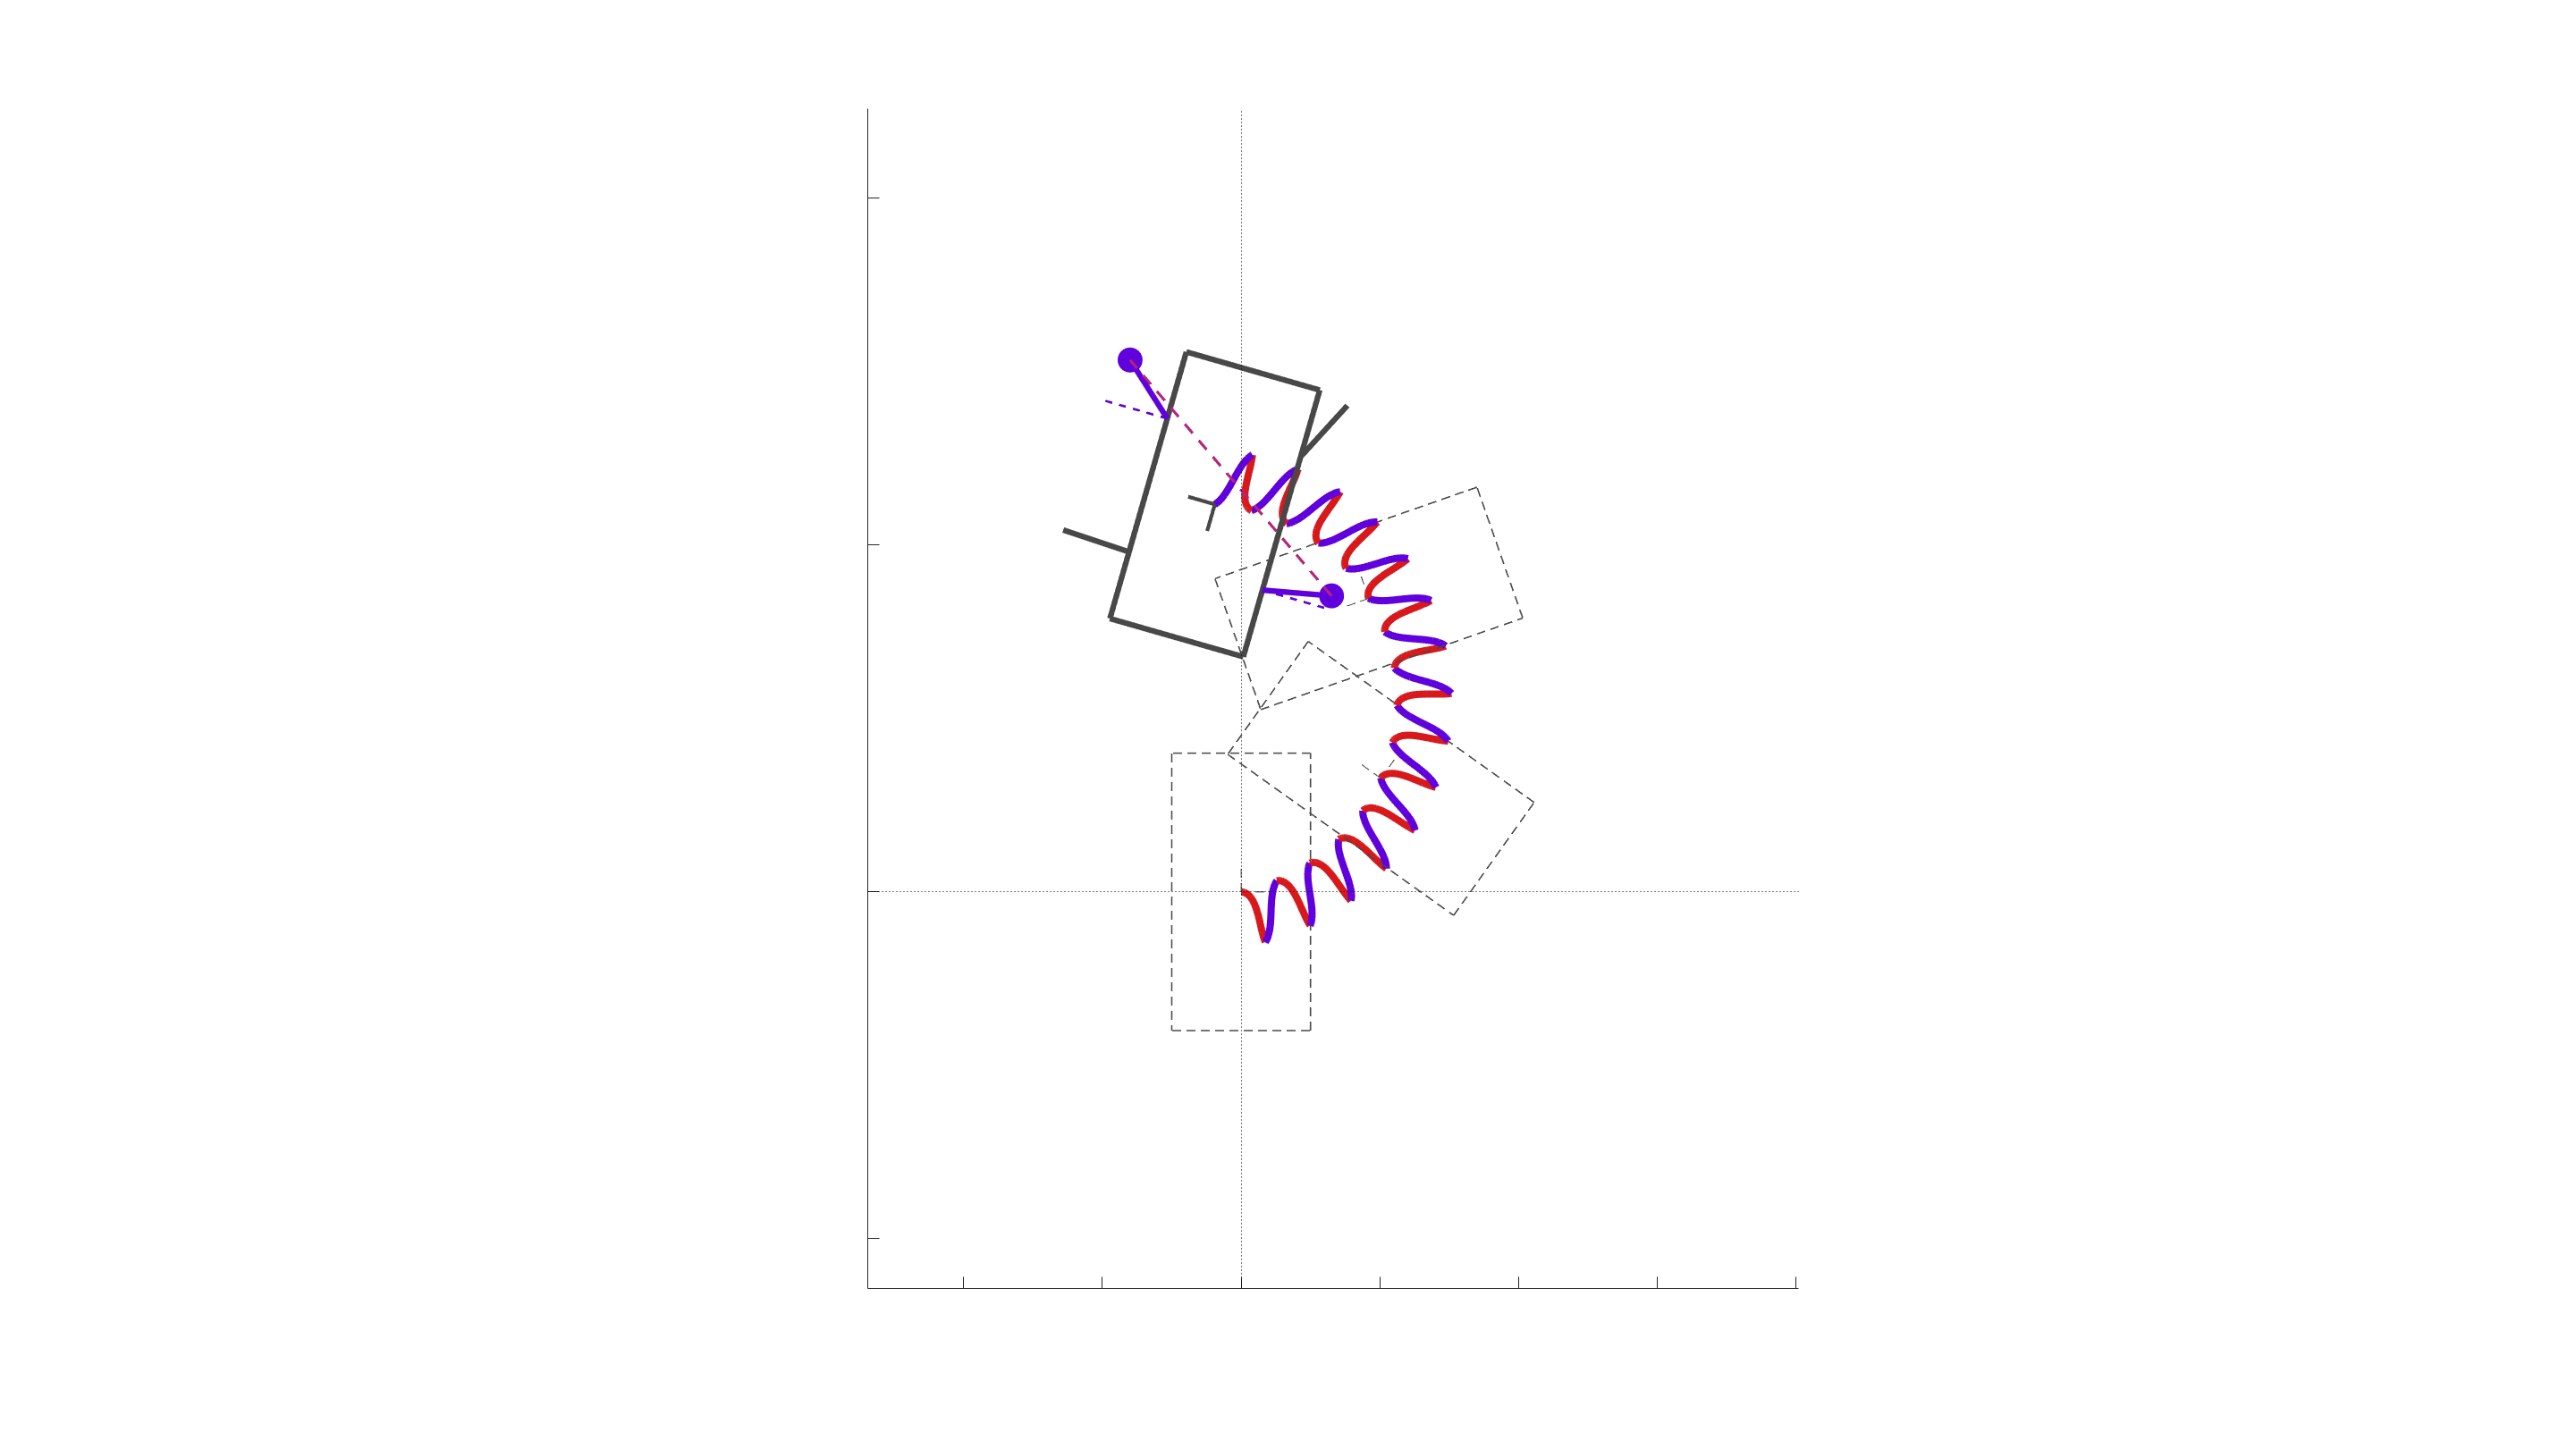

v = [];
save_addr = '';
save_name = 'slide13_lat_gait_1'; % {slide13_lat_gait_1, slide13_lat_gait_2} % 1 is slid in the +ve dirn and 2 in the other dirn
vid_time = 10;
v.fps = 60;
t = round(linspace(1, traj.dnum, v.fps*vid_time));
if t(end) < traj.dnum
    t(end+1) = traj.dnum;
end
vidF = true;
v.Name = [save_addr save_name];
if vidF
    video = VideoWriter([v.Name,'.mp4'],'MPEG-4');
    video.FrameRate = v.fps;
    video.Quality = 100;
    open(video);
end
f = figure('units','pixels','position',[0 0 1920 1080],'Color','w'); ax = gca;
set(f,'Visible','on');
for i = 1:numel(t)
    if i ~= 1
        for j = 1:numel(h)
            delete(h{j});
        end
    end
    switch i == 1
        case 0
            F = [t(i-1) t(i)];
        case 1
            F = [nan t(i)];
    end
    h = plot_SE2snapshot_QLvl2_Rigid_NoSlip(ax, pltTraj, F);
    drawnow;
    if vidF
        writeVideo(video,getframe(f));
    end
end

if vidF
    close(video);
end

addpath 'Data'\ 'Utility Functions'\;
load('Data\Gen_S13toS24.mat');
load('Data\Gen_S13_data.mat'); load('Data\Gen_S24_data.mat');

Let's try to create a nice overview figure for paper 2.

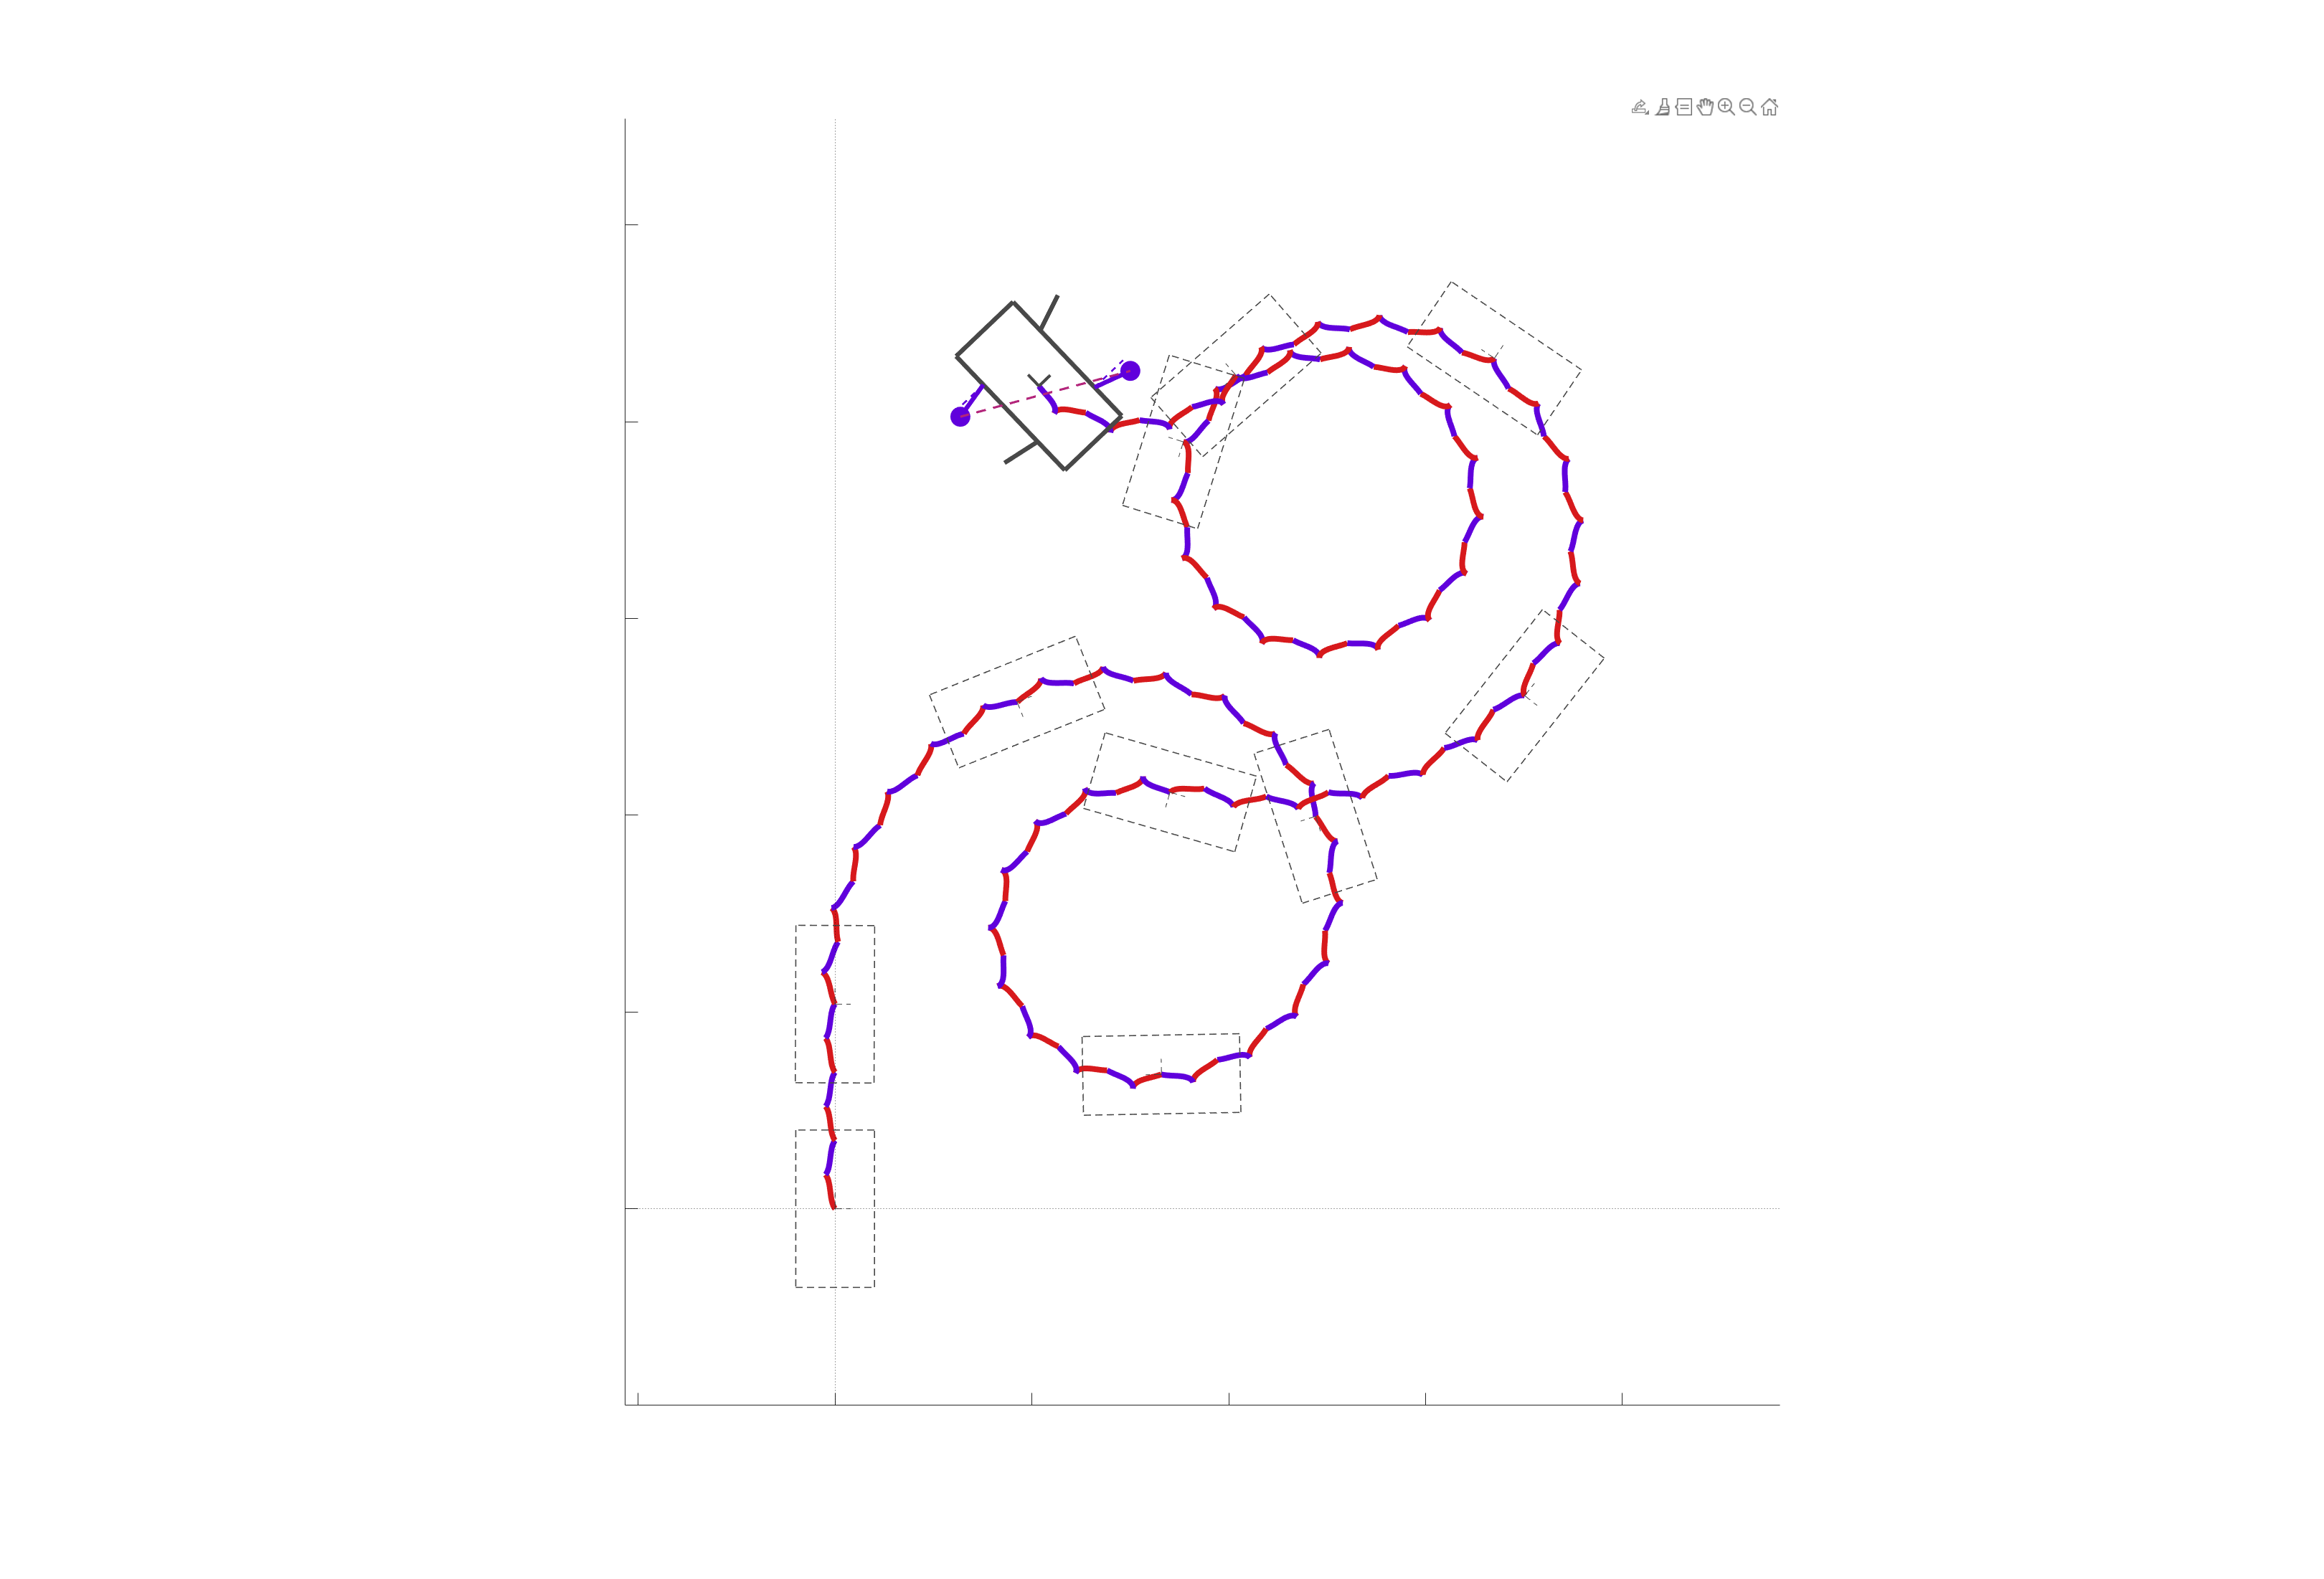

% compute the composite trajectory
[pltTraj, traj] = stitchQuadSE2gaits({    ...
    {{S13_Gen_trans, S24_Gen_trans}, {S13_Gen_steer, S24_Gen_steer}},...
    {Gen_S13toS24_trans_1_data, Gen_S13toS24_steer_1_data},...
    { {[1, 1]}, {[-0.5, 0.5], [-0.7, 0.7], [-0.8, 0.8], [-1, 1], -[-0.5, 0.5], -[-0.7, 0.7], -[-0.8, 0.8], -[-1, 1], [-1, 1]} },...
    { {3},      {6,           6,           6,           9,       6,            6,            6,            15,       4} }    });
% Create the SE(2) snapshot
m = 2160; n = 1800; % fixed resolution
f = figure('units','pixels','position',[100 -200 m n],'Color','w');
set(gcf,'Visible','on'); % pop-out figure
hA = plot_SE2snapshot_QLvl2_Rigid_NoSlip( gca, pltTraj);


% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% data ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~s
v = [];
save_addr = ''; % change to local address
save_name = 'composite_gait_1';

% get the points along the trajectory to animate
vid_time = 10; % in secs
v.fps = 60; % frames per second
% t = extractTimeVectorForCompGaitAnimation( traj.dnum, traj.gcVec, v.fps*vid_time, 'first' ); % slow down just the first gait cycle in each composite gait
t = linspace(1, traj.dnum, v.fps*vid_time);
if t(end) < traj.dnum
    t(end+1) = traj.dnum;
end
vidF = true;
v.Name = [save_addr save_name];
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~

% initialize video
if vidF
    video = VideoWriter([v.Name,'.mp4'],'MPEG-4');
    video.FrameRate = v.fps;
    video.Quality = 100;
    open(video);
end

% plot
f = figure('units','pixels','position',[0 0 1920 1080],'Color','w'); ax = gca;
set(f,'Visible','on');

for i = 1:numel(t)

    if i ~= 1
        for j = 1:numel(h)
            delete(h{j}); % delete plots
        end
    end
    
    switch i == 1
        case 0
            F = [t(i-1) t(i)];
        case 1
            F = [nan t(i)];
    end
    h = plot_SE2snapshot_QLvl2_Rigid_NoSlip(ax, pltTraj, F); % SE(2) snapshot
    drawnow;

    if vidF
        writeVideo(video,getframe(f)); % get the frame
    end

end

if vidF
    close(video); % close the video
end